%% PREDICTORS: KINEMATICS, GROUP, & INTERACTION. RESPONSE: BRAIN ACTIVITY, STATS TEST
REGRESS_TXT_SIZE = 8;
REGRESS_TXT_XMULTI = 0.9;
REGRESS_TXT_YMULTI = 1.0;
im_resize = 0.7;
AX_W = 0.35;
AX_H = 0.25;
GROUP_SHORTS = {'YA','HO','FO'};
GROUP_MARKS = {'o','x','^'};
GROUP_LINESTYLES = {'-','-.',':'};
MEASURE_NAME_LABS = {'Mean \theta','Mean \alpha','Mean \beta'};
PLOT_PARAMS = struct('color_map',[],...
        'cond_labels',unique(TMP_FOOOF_T.cond_char),'group_labels',unique(TMP_FOOOF_T.group_char),...
        'cond_offsets',[-0.3,-0.1,0.1,0.3],'y_label',[],...
        'title',[],'font_size',10,'ylim',[],...
        'font_name','Arial','x_label','speed','do_combine_groups',true);
tmp_savedir = [save_dir filesep 'Pkin-PGroup-Pinter-Reeg'];
mkdir(tmp_savedir);

##3-theta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                      6.0707         2       3.0354       3.1591    0.044165
    mean_APexc_COV                  3.0638         1       3.0638       3.1887    0.075363
    group_char:mean_APexc_COV       1.0924         2       0.5462      0.56846     0.56713
    Error                           240.21       250      0.96084                         
    Total                           327.15       255                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue 
                                         _________    ________    ________    ________

    (Intercept)                             0.2146     0.41635     0.51543     0.60671
    group_char_H2000's                    -0.26641     0.69123    -0.38541     0.70026
    group_char_H3000's                      1.1167     0.54909      2.0337    0.043043
    mean_APexc_COV                       0.0093588    0.024773     0.37778     0.70591
    group_char_H2000's:mean_APexc_COV     0.033446    0.035005     0.95545     0.34028
    group_char_H3000's:mean_APexc_COV    0.0060366

##3-alpha_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                      16.037         2      8.0184        1.9967     0.13794
    mean_APexc_COV                  1.1941         1      1.1941       0.29735     0.58604
    group_char:mean_APexc_COV       20.406         2      10.203        2.5407    0.080841
    Error                             1004       250      4.0158                          
    Total                           1066.8       255                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate       SE        tStat       pValue  
                                         ________    ________    _______    __________

    (Intercept)                            3.8376     0.85117     4.5086    1.0035e-05
    group_char_H2000's                     1.1737      1.4131    0.83054       0.40703
    group_char_H3000's                    -1.3893      1.1225    -1.2376       0.21702
    mean_APexc_COV                        0.01015    0.050645     0.2004       0.84133
    group_char_H2000's:mean_APexc_COV    -0.10218    0.071564    -1.4278       0.15461
    group_char_H3000's:mean_APexc_COV    0.029551 

##3-beta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue  
                                 ____________    ___    ___________    _______    _________

    group_char                      17.754         2      8.8768        6.9304    0.0011767
    mean_APexc_COV                  1.2114         1      1.2114       0.94573      0.33175
    group_char:mean_APexc_COV       11.053         2      5.5263        4.3145     0.014383
    Error                           320.22       250      1.2809                           
    Total                           365.26       255                                       



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                          Estimate        SE        tStat        pValue  
                                         __________    ________    ________    __________

    (Intercept)                              2.4966     0.48071      5.1937    4.2774e-07
    group_char_H2000's                      0.86188     0.79808      1.0799       0.28121
    group_char_H3000's                      -1.6967     0.63397     -2.6764      0.007934
    mean_APexc_COV                       -0.0070404    0.028602    -0.24615       0.80577
    group_char_H2000's:mean_APexc_COV     -0.058695    0.040417     -1.4522       0.14769
    group_char_H3000's:mean_APexc_COV</

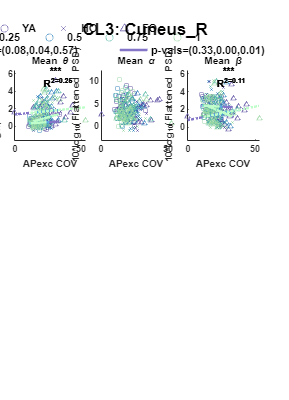

##3-theta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares      F         pValue  
                                  ____________    ___    ___________    ______    __________

    group_char                       17.789         2       8.8947      9.2673    0.00013106
    mean_APexc_mean                 0.85489         1      0.85489      0.8907        0.3462
    group_char:mean_APexc_mean       4.0804         2       2.0402      2.1257       0.12151
    Error                            239.95       250      0.95979                          
    Total                            327.15       255                                       



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                            0.31869    0.37412     0.85183       0.39512
    group_char_H2000's                    -0.13213    0.52671    -0.25086       0.80213
    group_char_H3000's                      1.5932    0.46879      3.3985    0.00078848
    mean_APexc_mean                        0.89837     6.6828     0.13443       0.89317
    group_char_H2000's:mean_APexc_mean      14.845     10.406      1.4267       0.15492
    group_char_H3000's:mean_APexc_mean    

##3-alpha_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    ________    _______

    group_char                      0.98319         2      0.49159        0.1201    0.88688
    mean_APexc_mean                 0.32154         1      0.32154      0.078553     0.7795
    group_char:mean_APexc_mean       1.0446         2      0.52232       0.12761    0.88026
    Error                            1023.3       250       4.0933                         
    Total                            1066.8       255                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                             3.5619    0.77261      4.6102    6.422e-06
    group_char_H2000's                    -0.51485     1.0877    -0.47333      0.63639
    group_char_H3000's                    -0.15838    0.96812    -0.16359      0.87019
    mean_APexc_mean                         8.1901     13.801     0.59345      0.55342
    group_char_H2000's:mean_APexc_mean     -9.1721     21.489    -0.42683      0.66987
    group_char_H3000's:mean_APexc_mean       -8.3

##3-beta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                       2.6631         2       1.3315         1.01    0.36572
    mean_APexc_mean                 0.81608         1      0.81608      0.61899    0.43217
    group_char:mean_APexc_mean       1.1699         2      0.58495      0.44368    0.64218
    Error                             329.6       250       1.3184                        
    Total                            365.26       255                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                             2.2801    0.43848         5.2    4.1483e-07
    group_char_H2000's                    0.066556    0.61731     0.10782       0.91423
    group_char_H3000's                    -0.60787    0.54944     -1.1063       0.26964
    mean_APexc_mean                         1.8908     7.8324      0.2414       0.80944
    group_char_H2000's:mean_APexc_mean     -11.449     12.196    -0.93876       0.34876
    group_char_H3000's:mean_APexc_mean     

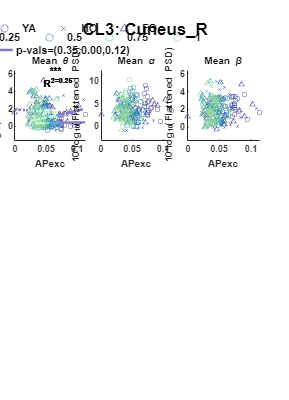

##3-theta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F         pValue  
                                 ____________    ___    ___________    _______    __________

    group_char                       20.731        2       10.366       10.922    2.8347e-05
    mean_MLexc_COV                 0.032315        1     0.032315      0.03405       0.85375
    group_char:mean_MLexc_COV        7.0633        2       3.5317       3.7213      0.025555
    Error                            237.26      250      0.94905                           
    Total                            327.15      255                                        



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                            0.51091     0.29936      1.7067      0.089128
    group_char_H2000's                    -0.31663     0.44525    -0.71112       0.47767
    group_char_H3000's                      1.6322     0.43385      3.7622    0.00020984
    mean_MLexc_COV                       -0.010607    0.020766    -0.51076       0.60997
    group_char_H2000's:mean_MLexc_COV     0.059689    0.030289      1.9707      0.049867
    group_char_H3000's:mean_MLexc_COV

##3-alpha_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    group_char                      6.3761         2      3.1881        0.77941    0.45979
    mean_MLexc_COV                  1.6438         1      1.6438        0.40187     0.5267
    group_char:mean_MLexc_COV       0.4774         2      0.2387       0.058357    0.94333
    Error                           1022.6       250      4.0904                          
    Total                           1066.8       255                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             4.2278     0.62149      6.8028    7.5328e-11
    group_char_H2000's                     -1.1515     0.92435     -1.2457       0.21404
    group_char_H3000's                    -0.45364     0.90068    -0.50366       0.61494
    mean_MLexc_COV                       -0.016582    0.043112    -0.38464       0.70083
    group_char_H2000's:mean_MLexc_COV     0.011394    0.062881     0.18119       0.85636
    group_char_H3000's:mean_MLexc_COV

##3-beta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      2.5117         2       1.2558      0.95866    0.38481
    mean_MLexc_COV                  3.6732         1       3.6732        2.804    0.09528
    group_char:mean_MLexc_COV      0.27164         2      0.13582      0.10368    0.90155
    Error                            327.5       250         1.31                        
    Total                           365.26       255                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             2.5903     0.35171      7.3649    2.5667e-12
    group_char_H2000's                    -0.23123     0.52311    -0.44202       0.65885
    group_char_H3000's                    -0.69705     0.50971     -1.3675       0.17269
    mean_MLexc_COV                       -0.015369    0.024398    -0.62995       0.52931
    group_char_H2000's:mean_MLexc_COV    -0.015652    0.035586    -0.43985       0.66043
    group_char_H3000's:mean_MLexc_COV

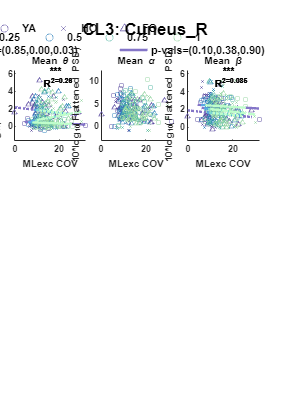

##3-theta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares      F        pValue 
                                  ____________    ___    ___________    ______    ________

    group_char                       3.3717         2      1.6858       1.8143     0.16509
    mean_MLexc_mean                  5.0257         1      5.0257       5.4087    0.020838
    group_char:mean_MLexc_mean       5.8536         2      2.9268       3.1498    0.044566
    Error                             232.3       250      0.9292                         
    Total                            327.15       255                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue 
                                          ________    _______    ________    ________

    (Intercept)                           0.18846     0.30115     0.62579     0.53202
    group_char_H2000's                    0.66716     0.41019      1.6264     0.10511
    group_char_H3000's                    0.68324     0.39421      1.7332    0.084297
    mean_MLexc_mean                        2.1987      3.4947     0.62916     0.52982
    group_char_H2000's:mean_MLexc_mean    -1.9056      4.4941    -0.42402     0.67192
    group_char_H3000's:mean_MLexc_mean     7.5746       

##3-alpha_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares      F        pValue 
                                  ____________    ___    ___________    ______    ________

    group_char                       18.116         2      9.0581       2.2676     0.10569
    mean_MLexc_mean                  5.4613         1      5.4613       1.3671     0.24342
    group_char:mean_MLexc_mean       18.932         2      9.4662       2.3697    0.095605
    Error                            998.66       250      3.9947                         
    Total                            1066.8       255                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                             3.8702    0.62442      6.1981    2.3426e-09
    group_char_H2000's                    -0.58735     0.8505    -0.69059       0.49046
    group_char_H3000's                     -1.6798    0.81736     -2.0551      0.040904
    mean_MLexc_mean                         1.6345     7.2459     0.22558       0.82171
    group_char_H2000's:mean_MLexc_mean      -4.737     9.3182    -0.50835       0.61165
    group_char_H3000's:mean_MLexc_mean    

##3-beta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    _______    ________

    group_char                       6.6473         2       3.3237       2.5162    0.082808
    mean_MLexc_mean                 0.27228         1      0.27228      0.20614     0.65021
    group_char:mean_MLexc_mean       0.8542         2       0.4271      0.32334     0.72403
    Error                            330.22       250       1.3209                         
    Total                            365.26       255                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                             2.4394    0.35906      6.7938    7.9403e-11
    group_char_H2000's                     -0.2485    0.48906    -0.50811       0.61183
    group_char_H3000's                    -0.98418    0.47001      -2.094      0.037271
    mean_MLexc_mean                       -0.70731     4.1666    -0.16975       0.86534
    group_char_H2000's:mean_MLexc_mean     -2.2534     5.3583    -0.42054       0.67445
    group_char_H3000's:mean_MLexc_mean     

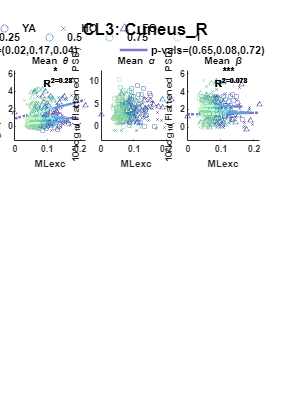

##3-theta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F        pValue 
                               ____________    ___    ___________    _______    ________

    group_char                     4.764         2        2.382       2.4459    0.088723
    mean_StepDur                 0.71234         1      0.71234      0.73144     0.39324
    group_char:mean_StepDur      0.50062         2      0.25031      0.25702     0.77356
    Error                         243.47       250      0.97389                         
    Total                         327.15       255                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate      SE         tStat       pValue 
                                       ________    _______    _________    ________

    (Intercept)                         0.36605    0.31417       1.1651     0.24507
    group_char_H2000's                  0.21258    0.52686      0.40348     0.68694
    group_char_H3000's                   1.1111     0.5117       2.1713    0.030846
    mean_StepDur                       0.001133    0.32742    0.0034602     0.99724
    group_char_H2000's:mean_StepDur     0.39941    0.62884      0.63515     0.52591
    group_char_H3000's:mean_StepDur     0.31548    0.64585      0.48846  

##3-alpha_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F       pValue 
                               ____________    ___    ___________    _______    _______

    group_char                    2.8585         2       1.4292      0.35029    0.70483
    mean_StepDur                    1.43         1         1.43      0.35048    0.55438
    group_char:mean_StepDur       1.4643         2      0.73215      0.17944    0.83584
    Error                           1020       250       4.0801                        
    Total                         1066.8       255                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate      SE         tStat       pValue  
                                       ________    _______    _________    _________

    (Intercept)                          3.4188    0.64304       5.3166    2.344e-07
    group_char_H2000's                 -0.80666     1.0784     -0.74803      0.45515
    group_char_H3000's                 0.079204     1.0474     0.075622      0.93978
    mean_StepDur                        0.64435    0.67018      0.96145      0.33726
    group_char_H2000's:mean_StepDur    -0.12744     1.2871    -0.099011      0.92121
    group_char_H3000's:mean_StepDur     -0.7879      1.322     -0.

##3-beta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F       pValue 
                               ____________    ___    ___________    _______    _______

    group_char                   0.50462         2      0.25231      0.19161    0.82575
    mean_StepDur                  0.5922         1       0.5922      0.44972    0.50308
    group_char:mean_StepDur       2.0438         2       1.0219      0.77603    0.46134
    Error                          329.2       250       1.3168                        
    Total                         365.26       255                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate       SE        tStat        pValue  
                                       _________    _______    ________    __________

    (Intercept)                           2.2752    0.36531      6.2281    1.9857e-09
    group_char_H2000's                  -0.37453    0.61263    -0.61135       0.54152
    group_char_H3000's                  -0.18705      0.595    -0.31436       0.75351
    mean_StepDur                         0.11772    0.38073      0.3092       0.75743
    group_char_H2000's:mean_StepDur    -0.086313    0.73122    -0.11804       0.90613
    group_char_H3000's:mean_StepDur     -0.92176      0.751 

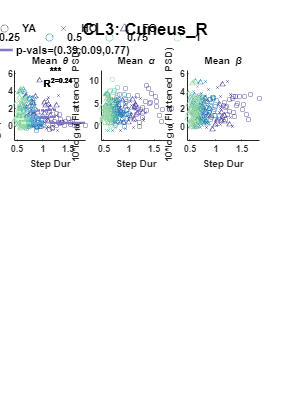

##3-theta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                      10.601         2       5.3007       5.4824    0.004675
    mean_UDexc_COV                  1.0736         1       1.0736       1.1104     0.29301
    group_char:mean_UDexc_COV       1.6495         2      0.82475      0.85301     0.42737
    Error                           241.72       250      0.96687                         
    Total                           327.15       255                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                          Estimate        SE        tStat       pValue  
                                         __________    ________    ________    _________

    (Intercept)                               0.427     0.25942       1.646      0.10102
    group_char_H2000's                     0.043659     0.38837     0.11241      0.91058
    group_char_H3000's                       1.1479     0.38248      3.0012    0.0029612
    mean_UDexc_COV                       -0.0048652    0.019347    -0.25148      0.80165
    group_char_H2000's:mean_UDexc_COV      0.036358    0.028023      1.2975      0.19567
    group_char_H3000's:mean_UDexc_COV

##3-alpha_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      14.124         2       7.0618       1.7276    0.17983
    mean_UDexc_COV                 0.50363         1      0.50363       0.1232    0.72588
    group_char:mean_UDexc_COV       2.4471         2       1.2235      0.29932    0.74159
    Error                           1021.9       250       4.0878                        
    Total                           1066.8       255                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                          Estimate        SE         tStat        pValue  
                                         __________    ________    _________    __________

    (Intercept)                              4.0412      0.5334       7.5763    6.9045e-13
    group_char_H2000's                      -1.4796     0.79857      -1.8528      0.065094
    group_char_H3000's                     -0.55529     0.78644     -0.70608        0.4808
    mean_UDexc_COV                       -0.0031069     0.03978    -0.078103       0.93781
    group_char_H2000's:mean_UDexc_COV      0.036946    0.057619      0.64121       0.52198
    group_char_H3000's:mean_UDe

##3-beta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    group_char                      5.5247         2       2.7624        2.0896    0.12589
    mean_UDexc_COV                 0.73391         1      0.73391       0.55517    0.45691
    group_char:mean_UDexc_COV      0.11376         2     0.056881      0.043028    0.95789
    Error                           330.49       250        1.322                         
    Total                           365.26       255                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             2.5605     0.30333      8.4413    2.5535e-15
    group_char_H2000's                    -0.57222     0.45412       -1.26       0.20883
    group_char_H3000's                    -0.89714     0.44723      -2.006      0.045936
    mean_UDexc_COV                         -0.0145    0.022622    -0.64098       0.52212
    group_char_H2000's:mean_UDexc_COV    0.0096115    0.032767     0.29333       0.76951
    group_char_H3000's:mean_UDexc_COV

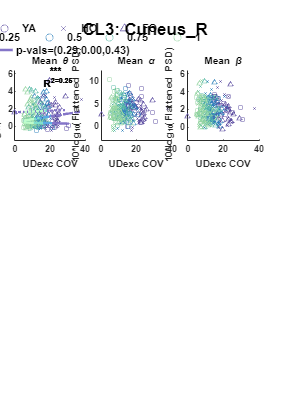

##3-theta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F         pValue 
                                  ____________    ___    ___________    ________    ________

    group_char                        7.6477        2       3.8239        3.9217    0.021037
    mean_UDexc_mean                 0.081808        1     0.081808      0.083902     0.77232
    group_char:mean_UDexc_mean       0.45011        2      0.22506       0.23082     0.79405
    Error                             243.76      250      0.97504                          
    Total                             327.15      255                                       



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE         tStat       pValue  
                                          ________    _______    _________    _________

    (Intercept)                             0.3663    0.30092       1.2173      0.22466
    group_char_H2000's                     0.56914    0.42862       1.3278      0.18544
    group_char_H3000's                       1.143    0.40861       2.7972    0.0055558
    mean_UDexc_mean                       0.033012     12.081    0.0027325      0.99782
    group_char_H2000's:mean_UDexc_mean     -2.2702     16.895     -0.13437      0.89322
    group_char_H3000's:mean_UDexc_mean    

##3-alpha_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares        F        pValue 
                                  ____________    ___    ___________    _________    _______

    group_char                        2.6659        2        1.333        0.32679    0.72154
    mean_UDexc_mean                 0.027564        1     0.027564      0.0067576    0.93455
    group_char:mean_UDexc_mean        4.9596        2       2.4798        0.60795    0.54527
    Error                             1019.7      250        4.079                          
    Total                             1066.8      255                                       



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                             3.7557    0.61549       6.102    3.9654e-09
    group_char_H2000's                    -0.26859    0.87668    -0.30637       0.75958
    group_char_H3000's                    -0.66758    0.83575    -0.79878       0.42517
    mean_UDexc_mean                         10.564      24.71     0.42754       0.66936
    group_char_H2000's:mean_UDexc_mean     -30.801     34.557    -0.89132       0.37362
    group_char_H3000's:mean_UDexc_mean    

##3-beta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    _______    ________

    group_char                       1.9312         2      0.96559      0.73942     0.47843
    mean_UDexc_mean                  3.7157         1       3.7157       2.8454    0.092884
    group_char:mean_UDexc_mean      0.92159         2      0.46079      0.35286     0.70302
    Error                            326.47       250       1.3059                         
    Total                            365.26       255                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                             2.4677    0.34825      7.0859    1.4026e-11
    group_char_H2000's                    -0.10536    0.49604     -0.2124       0.83196
    group_char_H3000's                    -0.53659    0.47288     -1.1347       0.25757
    mean_UDexc_mean                         -3.665     13.981    -0.26214       0.79343
    group_char_H2000's:mean_UDexc_mean     -14.664     19.553    -0.74998       0.45397
    group_char_H3000's:mean_UDexc_mean     

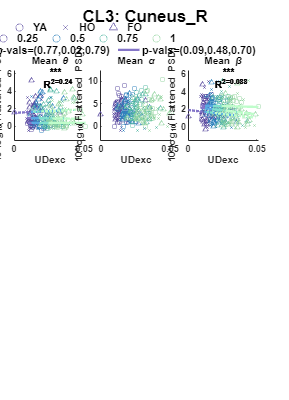

##3-theta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                      7.3464         2       3.6732       3.7737    0.024286
    mean_StanceDur                 0.82543         1      0.82543      0.84801       0.358
    group_char:mean_StanceDur      0.54573         2      0.27287      0.28033     0.75577
    Error                           243.34       250      0.97337                         
    Total                           327.15       255                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate       SE        tStat       pValue  
                                         _________    _______    ________    _________

    (Intercept)                            0.35625    0.26321      1.3535      0.17713
    group_char_H2000's                     0.25263    0.43462     0.58125       0.5616
    group_char_H3000's                      1.1629    0.42928      2.7089    0.0072168
    mean_StanceDur                       0.0087773    0.19652    0.044663      0.96441
    group_char_H2000's:mean_StanceDur      0.25909    0.37508     0.69077      0.49035
    group_char_H3000's:mean_StanceDur      0.18054

##3-alpha_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      2.5551         2       1.2775       0.3135    0.73117
    mean_StanceDur                  2.4863         1       2.4863      0.61014    0.43547
    group_char:mean_StanceDur      0.94027         2      0.47013      0.11537    0.89108
    Error                           1018.7       250        4.075                        
    Total                           1066.8       255                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate      SE        tStat        pValue  
                                         ________    _______    ________    __________

    (Intercept)                            3.4359    0.53856      6.3797    8.5332e-10
    group_char_H2000's                   -0.69095    0.88928    -0.77697       0.43791
    group_char_H3000's                   -0.12886    0.87834     -0.1467       0.88348
    mean_StanceDur                        0.46001    0.40211       1.144       0.25372
    group_char_H2000's:mean_StanceDur    -0.20622    0.76745    -0.26872       0.78837
    group_char_H3000's:mean_StanceDur    -0.36509 

##3-beta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                     0.99738         2      0.49869      0.37789     0.6857
    mean_StanceDur                 0.19928         1      0.19928      0.15101     0.6979
    group_char:mean_StanceDur       1.4443         2      0.72215      0.54722    0.57925
    Error                           329.92       250       1.3197                        
    Total                           365.26       255                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate       SE        tStat        pValue  
                                         _________    _______    ________    __________

    (Intercept)                              2.246    0.30648      7.3285    3.2125e-12
    group_char_H2000's                    -0.34904    0.50607    -0.68972       0.49101
    group_char_H3000's                    -0.37363    0.49984    -0.74749       0.45547
    mean_StanceDur                         0.11023    0.22883     0.48174       0.63042
    group_char_H2000's:mean_StanceDur    -0.083282    0.43673    -0.19069       0.84892
    group_char_H3000's:mean_StanceDur     -0

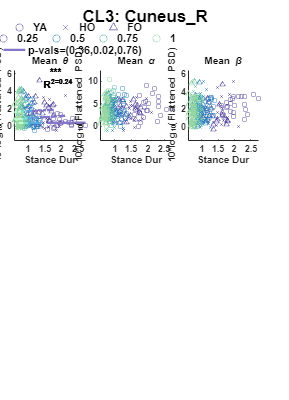

##3-theta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F        pValue 
                                    ____________    ___    ___________    _______    ________

    group_char                         4.7783         2       2.3891       2.4533    0.088074
    mean_GaitCycleDur                 0.72405         1      0.72405      0.74351     0.38937
    group_char:mean_GaitCycleDur       0.5087         2      0.25435      0.26119     0.77035
    Error                              243.46       250      0.97383                         
    Total                              327.15       255                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                             Estimate       SE         tStat      pValue 
                                            __________    _______    _________    _______

    (Intercept)                                0.36569    0.31394       1.1648    0.24519
    group_char_H2000's                         0.20937    0.52628      0.39784    0.69109
    group_char_H3000's                          1.1114    0.51135       2.1734    0.03069
    mean_GaitCycleDur                       0.00076124    0.16349    0.0046562    0.99629
    group_char_H2000's:mean_GaitCycleDur       0.20176    0.31388       0.6428    0.52094
    group_char_H3000's:mean_GaitCyc

##3-alpha_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F       pValue 
                                    ____________    ___    ___________    _______    _______

    group_char                         2.8797         2       1.4398      0.35287    0.70301
    mean_GaitCycleDur                  1.4084         1       1.4084      0.34516     0.5574
    group_char:mean_GaitCycleDur       1.4582         2      0.72912      0.17869    0.83647
    Error                              1020.1       250       4.0803                        
    Total                              1066.8       255                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate       SE         tStat        pValue  
                                            _________    _______    _________    __________

    (Intercept)                                3.4232    0.64262       5.3269    2.2278e-07
    group_char_H2000's                       -0.81008     1.0773     -0.75197       0.45278
    group_char_H3000's                       0.076551     1.0467     0.073135       0.94176
    mean_GaitCycleDur                         0.31958    0.33465      0.95497       0.34052
    group_char_H2000's:mean_GaitCycleDur    -0.061874    0.64249    -0.096303       0.92336
    group_char_H3000'

##3-beta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F       pValue 
                                    ____________    ___    ___________    _______    _______

    group_char                        0.51647         2      0.25823      0.19611    0.82205
    mean_GaitCycleDur                 0.59835         1      0.59835       0.4544    0.50088
    group_char:mean_GaitCycleDur       2.0449         2       1.0224      0.77646    0.46114
    Error                               329.2       250       1.3168                        
    Total                              365.26       255                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate      SE        tStat        pValue  
                                            ________    _______    ________    __________

    (Intercept)                               2.2778    0.36506      6.2396    1.8632e-09
    group_char_H2000's                      -0.37862    0.61198    -0.61868       0.53669
    group_char_H3000's                      -0.18854    0.59462    -0.31708       0.75144
    mean_GaitCycleDur                       0.057374    0.19011      0.3018       0.76306
    group_char_H2000's:mean_GaitCycleDur    -0.04072    0.36499    -0.11157       0.91126
    group_char_H3000's:mean_GaitCycl

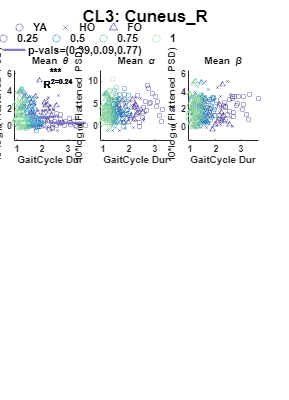

##3-theta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F         pValue  
                                          ____________    ___    ___________    ________    _________

    group_char                                13.107        2       6.5536        6.7275    0.0014263
    mean_PeakUpDownVel_mean                 0.064861        1     0.064861      0.066581      0.79659
    group_char:mean_PeakUpDownVel_mean       0.73584        2      0.36792       0.37768      0.68584
    Error                                     243.54      250      0.97416                           
    Total                                     327.15      255                                        



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat        pValue  
                                                  ________    _______    ________    __________

    (Intercept)                                    0.35245    0.24604      1.4325       0.15325
    group_char_H2000's                             0.72879    0.36259        2.01       0.04551
    group_char_H3000's                              1.2713    0.34766      3.6567    0.00031151
    mean_PeakUpDownVel_mean                       0.062406    0.95395    0.065418       0.94789
    group_char_H2000's:mean_PeakUpDownVel_mean    -0.84381      1.339    -0.63018       0.5

##3-alpha_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F       pValue 
                                          ____________    ___    ___________    _______    _______

    group_char                               1.8583         2      0.92916      0.22826    0.79608
    mean_PeakUpDownVel_mean                 0.59164         1      0.59164      0.14534    0.70335
    group_char:mean_PeakUpDownVel_mean        6.547         2       3.2735      0.80417    0.44861
    Error                                    1017.7       250       4.0707                        
    Total                                    1066.8       255                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat        pValue  
                                                  ________    _______    ________    __________

    (Intercept)                                     3.8051    0.50295      7.5657    7.3819e-13
    group_char_H2000's                            -0.19452    0.74119    -0.26244        0.7932
    group_char_H3000's                            -0.47767    0.71067    -0.67215       0.50211
    mean_PeakUpDownVel_mean                        0.84446       1.95     0.43305       0.66535
    group_char_H2000's:mean_PeakUpDownVel_mean     -3.2248     2.7371     -1.1782       0.2

##3-beta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F       pValue 
                                          ____________    ___    ___________    _______    _______

    group_char                               3.0426         2       1.5213       1.1545    0.31688
    mean_PeakUpDownVel_mean                  1.0906         1       1.0906      0.82764    0.36383
    group_char:mean_PeakUpDownVel_mean      0.77909         2      0.38954      0.29563    0.74432
    Error                                    329.42       250       1.3177                        
    Total                                    365.26       255                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat        pValue  
                                                  ________    _______    ________    __________

    (Intercept)                                     2.3539    0.28615      8.2261    1.0658e-14
    group_char_H2000's                            -0.19625     0.4217    -0.46538       0.64207
    group_char_H3000's                            -0.60339    0.40433     -1.4923       0.13688
    mean_PeakUpDownVel_mean                        0.11957     1.1095     0.10778       0.91426
    group_char_H2000's:mean_PeakUpDownVel_mean     -1.0341     1.5573    -0.66406       0.50

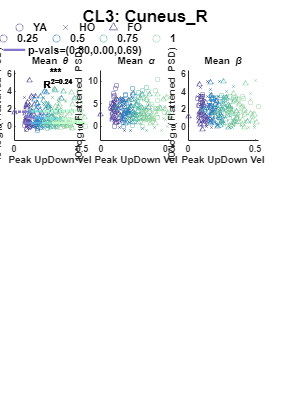

##4-theta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                       2.468         2        1.234       1.4308     0.24162
    mean_APexc_COV                  3.0217         1       3.0217       3.5037    0.062735
    group_char:mean_APexc_COV      0.69693         2      0.34846      0.40405     0.66817
    Error                           167.31       194      0.86243                         
    Total                            192.9       199                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue  
                                         _________    ________    _______    __________

    (Intercept)                             2.0221     0.44452      4.549    9.4878e-06
    group_char_H2000's                    -0.89442      0.7123    -1.2557       0.21074
    group_char_H3000's                    -0.95404     0.60206    -1.5846       0.11468
    mean_APexc_COV                       -0.043132    0.027257    -1.5824       0.11518
    group_char_H2000's:mean_APexc_COV     0.032277    0.036812    0.87683       0.38166
    group_char_H3000's:mean_APexc_COV     0

##4-alpha_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares      F        pValue 
                                 ____________    ___    ___________    ______    ________

    group_char                      12.341         2      6.1707       2.3505    0.098029
    mean_APexc_COV                  3.0065         1      3.0065       1.1452     0.28588
    group_char:mean_APexc_COV       18.552         2      9.2761       3.5334    0.031099
    Error                            509.3       194      2.6253                         
    Total                           548.34       199                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE         tStat       pValue  
                                         _________    ________    _________    _________

    (Intercept)                             2.4383     0.77556       3.1439    0.0019291
    group_char_H2000's                   -0.052597      1.2428    -0.042323      0.96628
    group_char_H3000's                     -2.0414      1.0504      -1.9434     0.053409
    mean_APexc_COV                       -0.091054    0.047555      -1.9147     0.057002
    group_char_H2000's:mean_APexc_COV     0.061452    0.064225      0.95681      0.33985
    group_char_H3000's:mean_APexc_COV

##4-beta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      3.9803         2       1.9901       1.3276     0.2675
    mean_APexc_COV                 0.16574         1      0.16574      0.11057    0.73986
    group_char:mean_APexc_COV       3.1617         2       1.5809       1.0546    0.35032
    Error                           290.81       194        1.499                        
    Total                           319.08       199                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                          Estimate        SE        tStat       pValue 
                                         __________    ________    ________    ________

    (Intercept)                              1.1922     0.58605      2.0344    0.043276
    group_char_H2000's                     -0.17187     0.93908    -0.18302     0.85497
    group_char_H3000's                       1.0737     0.79375      1.3527     0.17772
    mean_APexc_COV                       -0.0045367    0.035935    -0.12625     0.89967
    group_char_H2000's:mean_APexc_COV        0.0434    0.048532     0.89426     0.37229
    group_char_H3000's:mean_APexc_COV     -0

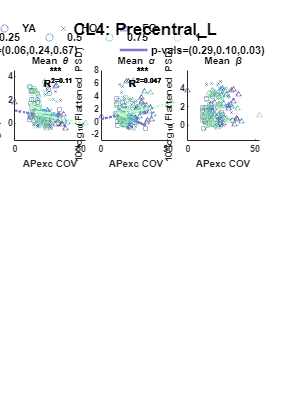

##4-theta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares        F        pValue 
                                  ____________    ___    ___________    _________    _______

    group_char                        2.1369        2        1.0684        1.2186    0.29788
    mean_APexc_mean                0.0032884        1     0.0032884     0.0037506    0.95123
    group_char:mean_APexc_mean        1.1087        2       0.55434       0.63227    0.53247
    Error                             170.09      194       0.87675                         
    Total                              192.9      199                                       



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                             1.4165    0.40642      3.4853    0.00060767
    group_char_H2000's                    -0.81992    0.54664     -1.4999       0.13526
    group_char_H3000's                    -0.64205    0.53047     -1.2103       0.22763
    mean_APexc_mean                        -1.3932     7.1523    -0.19479       0.84576
    group_char_H2000's:mean_APexc_mean      8.0658     10.662     0.75653       0.45025
    group_char_H3000's:mean_APexc_mean    

##4-alpha_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares      F        pValue  
                                  ____________    ___    ___________    ______    _________

    group_char                       9.5875         2      4.7937       1.9153      0.15007
    mean_APexc_mean                    21.2         1        21.2       8.4702    0.0040323
    group_char:mean_APexc_mean        25.25         2      12.625       5.0443    0.0073175
    Error                            485.56       194      2.5029                          
    Total                            548.34       199                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                             1.4606    0.68669       2.127     0.034687
    group_char_H2000's                     -1.8067    0.92361     -1.9561     0.051889
    group_char_H3000's                    -0.95053    0.89629     -1.0605      0.29023
    mean_APexc_mean                        -8.4393     12.084    -0.69836      0.48579
    group_char_H2000's:mean_APexc_mean      55.938     18.014      3.1053    0.0021858
    group_char_H3000's:mean_APexc_mean      36.49

##4-beta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    _______    ________

    group_char                       1.5633         2      0.78166      0.54087     0.58312
    mean_APexc_mean                  5.5853         1       5.5853       3.8647    0.050739
    group_char:mean_APexc_mean       9.6761         2        4.838       3.3477    0.037209
    Error                            280.37       194       1.4452                         
    Total                            319.08       199                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                             1.6072     0.5218        3.08    0.0023702
    group_char_H2000's                    -0.68735    0.70183    -0.97936      0.32862
    group_char_H3000's                    -0.57593    0.68107    -0.84563       0.3988
    mean_APexc_mean                        -8.8981     9.1827      -0.969      0.33375
    group_char_H2000's:mean_APexc_mean      30.713     13.688      2.2438     0.025977
    group_char_H3000's:mean_APexc_mean      30.432

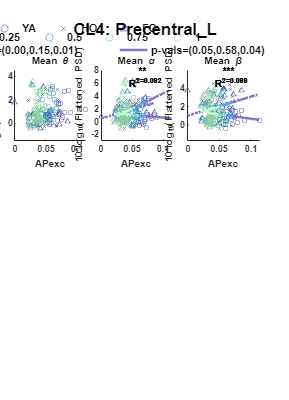

##4-theta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                      1.4952         2      0.74761      0.86474     0.42278
    mean_MLexc_COV                  2.7837         1       2.7837       3.2198    0.074309
    group_char:mean_MLexc_COV      0.29142         2      0.14571      0.16854     0.84502
    Error                           167.72       194      0.86455                         
    Total                            192.9       199                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                          Estimate        SE        tStat       pValue 
                                         __________    ________    ________    ________

    (Intercept)                             0.82124     0.33743      2.4338    0.015848
    group_char_H2000's                     -0.12911     0.48892    -0.26406     0.79201
    group_char_H3000's                     -0.63713     0.50386     -1.2645     0.20757
    mean_MLexc_COV                         0.033294     0.02047      1.6265     0.10547
    group_char_H2000's:mean_MLexc_COV     -0.018666    0.032191    -0.57986     0.56268
    group_char_H3000's:mean_MLexc_COV    -0

##4-alpha_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F         pValue 
                                 ____________    ___    ___________    ________    ________

    group_char                       15.014        2       7.5071        2.8646    0.059418
    mean_MLexc_COV                 0.030973        1     0.030973      0.011819     0.91354
    group_char:mean_MLexc_COV         18.81        2       9.4049        3.5888    0.029481
    Error                             508.4      194       2.6206                          
    Total                            548.34      199                                       



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE         tStat       pValue  
                                         _________    ________    _________    _________

    (Intercept)                             1.7852     0.58748       3.0387    0.0027037
    group_char_H2000's                     0.62329     0.85123      0.73222      0.46492
    group_char_H3000's                     -1.4759     0.87724      -1.6824     0.094101
    mean_MLexc_COV                       -0.050422    0.035638      -1.4148      0.15872
    group_char_H2000's:mean_MLexc_COV    0.0003094    0.056046    0.0055204       0.9956
    group_char_H3000's:mean_MLexc_COV

##4-beta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                     0.40988         2      0.20494      0.13596    0.87296
    mean_MLexc_COV                 0.18058         1      0.18058       0.1198    0.72963
    group_char:mean_MLexc_COV       1.5357         2      0.76783      0.50938    0.60167
    Error                           292.43       194       1.5074                        
    Total                           319.08       199                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue  
                                         _________    ________    ________    _________

    (Intercept)                             1.3888     0.44556      3.1171    0.0021042
    group_char_H2000's                      0.3333     0.64559     0.51627      0.60625
    group_char_H3000's                     0.11549     0.66532     0.17358      0.86237
    mean_MLexc_COV                       -0.017209    0.027029    -0.63669      0.52508
    group_char_H2000's:mean_MLexc_COV     0.028602    0.042506     0.67288      0.50183
    group_char_H3000's:mean_MLexc_COV     0.

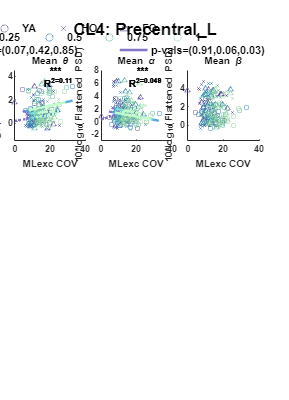

##4-theta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    _______    ________

    group_char                       4.1154         2       2.0577       2.3384    0.099196
    mean_MLexc_mean                 0.22523         1      0.22523      0.25596     0.61349
    group_char:mean_MLexc_mean      0.21592         2      0.10796      0.12269     0.88461
    Error                            170.71       194      0.87996                         
    Total                             192.9       199                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                              1.481    0.32661      4.5344    1.0099e-05
    group_char_H2000's                    -0.43528    0.44173    -0.98539       0.32566
    group_char_H3000's                     -0.9683    0.44972     -2.1531      0.032545
    mean_MLexc_mean                        -1.8074     3.9497    -0.45762       0.64774
    group_char_H2000's:mean_MLexc_mean     0.11041     4.9344    0.022375       0.98217
    group_char_H3000's:mean_MLexc_mean    

##4-alpha_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares      F        pValue 
                                  ____________    ___    ___________    ______    ________

    group_char                       5.5696         2      2.7848       1.0693     0.34527
    mean_MLexc_mean                  2.8093         1      2.8093       1.0787     0.30028
    group_char:mean_MLexc_mean       15.536         2      7.7678       2.9826    0.052989
    Error                            505.25       194      2.6044                         
    Total                            548.34       199                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                             1.5435    0.56189       2.747    0.0065812
    group_char_H2000's                     -1.0679    0.75994     -1.4053      0.16154
    group_char_H3000's                    -0.31971    0.77369    -0.41323       0.6799
    mean_MLexc_mean                        -6.9972     6.7948     -1.0298       0.3044
    group_char_H2000's:mean_MLexc_mean       20.62      8.489      2.4291      0.01605
    group_char_H3000's:mean_MLexc_mean      11.31

##4-beta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    ________    _______

    group_char                      0.077444        2     0.038722      0.025976    0.97436
    mean_MLexc_mean                   1.5789        1       1.5789        1.0592    0.30469
    group_char:mean_MLexc_mean        2.3409        2       1.1705       0.78519    0.45748
    Error                             289.19      194       1.4907                         
    Total                             319.08      199                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                            1.2955      0.4251      3.0476    0.0026283
    group_char_H2000's                    0.11233     0.57494     0.19538       0.8453
    group_char_H3000's                    0.11937     0.58534     0.20394      0.83861
    mean_MLexc_mean                       -2.2488      5.1407    -0.43746      0.66227
    group_char_H2000's:mean_MLexc_mean     7.3083      6.4224      1.1379      0.25655
    group_char_H3000's:mean_MLexc_mean     7.6408 

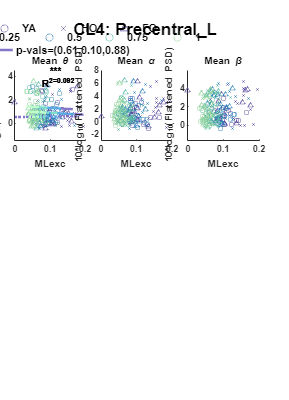

##4-theta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares        F        pValue 
                               ____________    ___    ___________    _________    _______

    group_char                     3.3402        2        1.6701        1.8968    0.15283
    mean_StepDur                0.0021064        1     0.0021064     0.0023922    0.96104
    group_char:mean_StepDur       0.31124        2       0.15562       0.17674    0.83813
    Error                          170.82      194        0.8805                         
    Total                           192.9      199                                       



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate       SE        tStat        pValue  
                                       _________    _______    ________    __________

    (Intercept)                           1.4508    0.32989      4.3979    1.7998e-05
    group_char_H2000's                  -0.41265    0.54262    -0.76048       0.44789
    group_char_H3000's                   -1.0891    0.55949     -1.9465      0.053035
    mean_StepDur                        -0.11967    0.33664    -0.35548       0.72261
    group_char_H2000's:mean_StepDur    -0.076863    0.64121    -0.11987       0.90471
    group_char_H3000's:mean_StepDur      0.39129    0.73004

##4-alpha_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F        pValue 
                               ____________    ___    ___________    _______    ________

    group_char                    3.3486         2      1.6743       0.64248      0.5271
    mean_StepDur                  16.901         1      16.901        6.4853    0.011653
    group_char:mean_StepDur       12.988         2      6.4939        2.4919    0.085399
    Error                         505.56       194       2.606                          
    Total                         548.34       199                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate      SE        tStat       pValue 
                                       ________    _______    ________    ________

    (Intercept)                         0.92212    0.56753      1.6248     0.10583
    group_char_H2000's                  -1.0566     0.9335     -1.1318      0.2591
    group_char_H3000's                 -0.33457    0.96254    -0.34759     0.72853
    mean_StepDur                       0.083296    0.57915     0.14383     0.88579
    group_char_H2000's:mean_StepDur       2.377     1.1031      2.1548    0.032411
    group_char_H3000's:mean_StepDur      1.3664     1.2559       1.088     0.277

##4-beta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares        F        pValue 
                               ____________    ___    ___________    _________    _______

    group_char                   0.022969        2     0.011485      0.0076748    0.99235
    mean_StepDur                   2.6492        1       2.6492         1.7704    0.18489
    group_char:mean_StepDur        2.8615        2       1.4307        0.95612    0.38619
    Error                           290.3      194       1.4964                          
    Total                          319.08      199                                       



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate       SE        tStat       pValue  
                                       _________    _______    ________    _________

    (Intercept)                           1.2342    0.43005        2.87    0.0045607
    group_char_H2000's                  0.065612    0.70738    0.092753       0.9262
    group_char_H3000's                 -0.031677    0.72938    -0.04343       0.9654
    mean_StepDur                        -0.12316    0.43886    -0.28063      0.77929
    group_char_H2000's:mean_StepDur      0.88082    0.83591      1.0537      0.29332
    group_char_H3000's:mean_StepDur       1.0697    0.95171       1

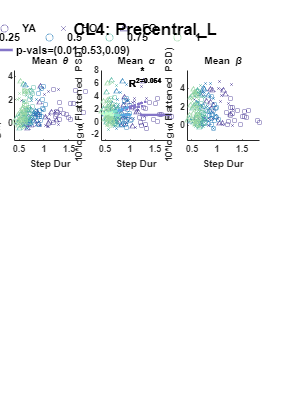

##4-theta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares      F        pValue 
                                 ____________    ___    ___________    ______    ________

    group_char                      5.9378         2       2.9689      3.4549    0.033547
    mean_UDexc_COV                  2.5003         1       2.5003      2.9095    0.089658
    group_char:mean_UDexc_COV       2.4604         2       1.2302      1.4316     0.24144
    Error                           166.71       194      0.85933                        
    Total                            192.9       199                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue  
                                         _________    ________    _______    __________

    (Intercept)                             1.8138     0.29866     6.0732    6.4932e-09
    group_char_H2000's                     -1.0193     0.41022    -2.4847      0.013812
    group_char_H3000's                     -0.8544     0.42585    -2.0064      0.046207
    mean_UDexc_COV                       -0.037912    0.022256    -1.7034      0.090086
    group_char_H2000's:mean_UDexc_COV     0.044996    0.029421     1.5294        0.1278
    group_char_H3000's:mean_UDexc_COV    0.

##4-alpha_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F         pValue 
                                 ____________    ___    ___________    ________    ________

    group_char                       16.54         2       8.2699        3.1735    0.044036
    mean_UDexc_COV                 0.23325         1      0.23325      0.089507     0.76512
    group_char:mean_UDexc_COV       22.206         2       11.103        4.2607    0.015455
    Error                           505.54       194       2.6059                          
    Total                           548.34       199                                       



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat      pValue  
                                         _________    ________    _______    _________

    (Intercept)                             1.7241     0.52009      3.315    0.0010936
    group_char_H2000's                     0.54382     0.71436    0.76127      0.44742
    group_char_H3000's                      -1.243     0.74157    -1.6762     0.095314
    mean_UDexc_COV                       -0.058055    0.038756     -1.498      0.13577
    group_char_H2000's:mean_UDexc_COV     0.017991    0.051233    0.35117      0.72584
    group_char_H3000's:mean_UDexc_COV      0.13747

##4-beta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares      F       pValue 
                                 ____________    ___    ___________    ______    _______

    group_char                      5.0029         2      2.5014       1.6804      0.189
    mean_UDexc_COV                  3.0167         1      3.0167       2.0265    0.15618
    group_char:mean_UDexc_COV       2.5014         2      1.2507       0.8402    0.43319
    Error                           288.79       194      1.4886                        
    Total                           319.08       199                                    



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             1.4327     0.39309      3.6449    0.00034348
    group_char_H2000's                     0.40642     0.53991     0.75276       0.45251
    group_char_H3000's                       1.021     0.56048      1.8216      0.070055
    mean_UDexc_COV                       -0.024998    0.029292     -0.8534       0.39449
    group_char_H2000's:mean_UDexc_COV     0.027717    0.038722      0.7158       0.47498
    group_char_H3000's:mean_UDexc_COV

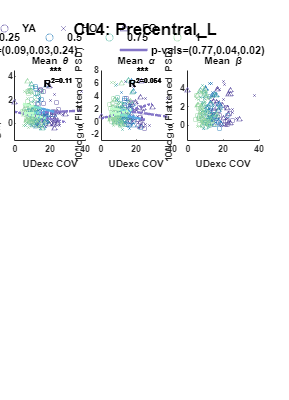

##4-theta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    _______    ________

    group_char                       1.0288         2      0.51439      0.59524     0.55244
    mean_UDexc_mean                  3.2516         1       3.2516       3.7626    0.053861
    group_char:mean_UDexc_mean      0.48586         2      0.24293      0.28111     0.75525
    Error                            167.65       194      0.86419                         
    Total                             192.9       199                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue 
                                          ________    _______    ________    ________

    (Intercept)                            0.87053    0.33783      2.5768    0.010714
    group_char_H2000's                    -0.33874    0.45512    -0.74428     0.45761
    group_char_H3000's                    -0.49331    0.45895     -1.0749     0.28377
    mean_UDexc_mean                         20.716     14.092      1.4701     0.14315
    group_char_H2000's:mean_UDexc_mean     -5.8821     18.324      -0.321     0.74856
    group_char_H3000's:mean_UDexc_mean     -13.691     1

##4-alpha_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                       2.4026         2      1.2013       0.44525    0.64132
    mean_UDexc_mean                  1.1224         1      1.1224       0.41602    0.51969
    group_char:mean_UDexc_mean       3.0667         2      1.5333       0.56831    0.56742
    Error                            523.42       194       2.698                         
    Total                            548.34       199                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat      pValue 
                                          ________    _______    ________    _______

    (Intercept)                           0.94281     0.59693      1.5794    0.11586
    group_char_H2000's                    0.15633     0.80418      0.1944    0.84607
    group_char_H3000's                    0.71332     0.81094     0.87961    0.38016
    mean_UDexc_mean                        2.4788      24.899    0.099554     0.9208
    group_char_H2000's:mean_UDexc_mean     23.912      32.378     0.73853    0.46109
    group_char_H3000's:mean_UDexc_mean    -6.3337      32.799  

##4-beta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                       5.8311         2       2.9155       1.9376    0.14682
    mean_UDexc_mean                 0.13201         1      0.13201      0.08773     0.7674
    group_char:mean_UDexc_mean       1.8825         2      0.94125      0.62555    0.53604
    Error                            291.91       194       1.5047                        
    Total                            319.08       199                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue 
                                          ________    _______    ________    ________

    (Intercept)                            1.1008     0.44578      2.4694    0.014399
    group_char_H2000's                      1.178     0.60055      1.9616     0.05124
    group_char_H3000's                    0.56509      0.6056      0.9331     0.35193
    mean_UDexc_mean                       0.87042      18.594    0.046811     0.96271
    group_char_H2000's:mean_UDexc_mean    -17.631       24.18    -0.72916     0.46679
    group_char_H3000's:mean_UDexc_mean     6.4409      24

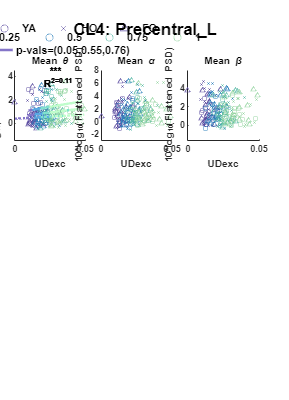

##4-theta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    group_char                      3.8696         2       1.9348        2.1961    0.11399
    mean_StanceDur                 0.01373         1      0.01373      0.015585    0.90078
    group_char:mean_StanceDur      0.18672         2     0.093362       0.10597     0.8995
    Error                           170.91       194      0.88099                         
    Total                            192.9       199                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate       SE        tStat        pValue  
                                         _________    _______    ________    __________

    (Intercept)                             1.4305    0.27435      5.2141    4.7112e-07
    group_char_H2000's                    -0.42732    0.44927    -0.95113       0.34272
    group_char_H3000's                    -0.99025    0.47542     -2.0829      0.038572
    mean_StanceDur                       -0.071547    0.19927    -0.35905       0.71995
    group_char_H2000's:mean_StanceDur    -0.039829    0.38322    -0.10393       0.91733
    group_char_H3000's:mean_StanceDur      

##4-alpha_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                      2.3918         2      1.1959       0.45652     0.63416
    mean_StanceDur                  13.401         1      13.401        5.1159    0.024817
    group_char:mean_StanceDur       12.206         2      6.1029        2.3297     0.10004
    Error                            508.2       194      2.6196                          
    Total                           548.34       199                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate       SE         tStat       pValue 
                                         _________    _______    _________    ________

    (Intercept)                            0.95277    0.47307        2.014     0.04539
    group_char_H2000's                    -0.69936    0.77471     -0.90275     0.36778
    group_char_H3000's                   -0.020489     0.8198    -0.024993     0.98009
    mean_StanceDur                        0.036711    0.34361      0.10684     0.91503
    group_char_H2000's:mean_StanceDur       1.4066    0.66081       2.1287    0.034544
    group_char_H3000's:mean_StanceDur      0.65003

##4-beta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    group_char                     0.19193         2     0.095964      0.064086    0.93794
    mean_StanceDur                  2.5861         1       2.5861         1.727    0.19034
    group_char:mean_StanceDur       2.6506         2       1.3253       0.88506    0.41435
    Error                            290.5       194       1.4974                         
    Total                           319.08       199                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate       SE        tStat        pValue  
                                         _________    _______    ________    __________

    (Intercept)                             1.1953    0.35767       3.342    0.00099787
    group_char_H2000's                      0.1948    0.58573     0.33258       0.73981
    group_char_H3000's                     0.14951    0.61982     0.24121       0.80965
    mean_StanceDur                       -0.059379    0.25979    -0.22857       0.81945
    group_char_H2000's:mean_StanceDur      0.53227    0.49961      1.0654       0.28804
    group_char_H3000's:mean_StanceDur      0

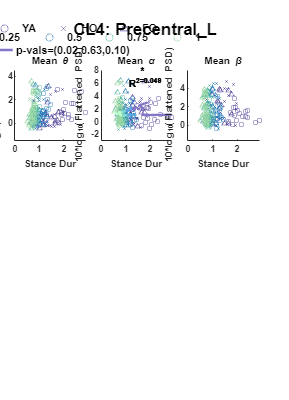

##4-theta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F        pValue 
                                    ____________    ___    ___________    ________    _______

    group_char                          3.3646        2        1.6823       1.9106    0.15077
    mean_GaitCycleDur                0.0014573        1     0.0014573     0.001655    0.96759
    group_char:mean_GaitCycleDur       0.31089        2       0.15545      0.17654     0.8383
    Error                               170.82      194       0.88052                        
    Total                                192.9      199                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate       SE        tStat       pValue  
                                            _________    _______    ________    _________

    (Intercept)                                1.4516    0.32953      4.4049    1.748e-05
    group_char_H2000's                       -0.41847    0.54191     -0.7722      0.44094
    group_char_H3000's                         -1.091    0.55854     -1.9533     0.052224
    mean_GaitCycleDur                       -0.060213    0.16806    -0.35828      0.72053
    group_char_H2000's:mean_GaitCycleDur    -0.034663    0.32001    -0.10832      0.91385
    group_char_H3000's:mean_GaitCyc

##4-alpha_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F        pValue 
                                    ____________    ___    ___________    _______    ________

    group_char                         3.3499         2      1.6749       0.64283     0.52692
    mean_GaitCycleDur                  16.988         1      16.988        6.5201    0.011435
    group_char:mean_GaitCycleDur       13.019         2      6.5096        2.4983    0.084864
    Error                              505.48       194      2.6056                          
    Total                              548.34       199                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate      SE        tStat      pValue 
                                            ________    _______    _______    ________

    (Intercept)                              0.92173    0.56686      1.626     0.10557
    group_char_H2000's                       -1.0555    0.93221    -1.1323     0.25891
    group_char_H3000's                      -0.33647    0.96081    -0.3502     0.72657
    mean_GaitCycleDur                       0.041847     0.2891    0.14475     0.88506
    group_char_H2000's:mean_GaitCycleDur      1.1873    0.55048     2.1568    0.032249
    group_char_H3000's:mean_GaitCycleDur     0.

##4-beta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares        F        pValue 
                                    ____________    ___    ___________    _________    _______

    group_char                        0.024163        2     0.012082      0.0080744    0.99196
    mean_GaitCycleDur                   2.6657        1       2.6657         1.7815    0.18353
    group_char:mean_GaitCycleDur        2.8735        2       1.4368        0.96021    0.38463
    Error                               290.28      194       1.4963                          
    Total                               319.08      199                                       



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate       SE        tStat       pValue  
                                            _________    _______    ________    _________

    (Intercept)                                1.2339    0.42957      2.8724    0.0045266
    group_char_H2000's                       0.066673    0.70643     0.09438       0.9249
    group_char_H3000's                       -0.03318     0.7281    -0.04557       0.9637
    mean_GaitCycleDur                       -0.061385    0.21908    -0.28019      0.77963
    group_char_H2000's:mean_GaitCycleDur      0.43955    0.41716      1.0537      0.29334
    group_char_H3000's:mean_GaitCycl

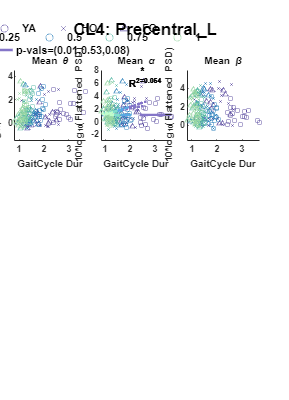

##4-theta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F       pValue 
                                          ____________    ___    ___________    _______    _______

    group_char                               1.6835         2      0.84177      0.96727    0.38194
    mean_PeakUpDownVel_mean                  1.9878         1       1.9878       2.2842    0.13233
    group_char:mean_PeakUpDownVel_mean       0.6541         2      0.32705      0.37581    0.68723
    Error                                    168.83       194      0.87025                        
    Total                                     192.9       199                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat        pValue  
                                                  ________    _______    ________    __________

    (Intercept)                                     1.0031    0.27041      3.7094    0.00027116
    group_char_H2000's                            -0.32584     0.3798    -0.85792         0.392
    group_char_H3000's                            -0.52767    0.38302     -1.3777        0.1699
    mean_PeakUpDownVel_mean                         1.4989      1.098      1.3651        0.1738
    group_char_H2000's:mean_PeakUpDownVel_mean     -0.6737     1.4424    -0.46708       0.6

##4-alpha_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F        pValue 
                                          ____________    ___    ___________    ________    _______

    group_char                               4.8784         2       2.4392       0.90118    0.40778
    mean_PeakUpDownVel_mean                 0.16222         1      0.16222      0.059934    0.80686
    group_char:mean_PeakUpDownVel_mean       2.6274         2       1.3137       0.48536    0.61622
    Error                                     525.1       194       2.7067                         
    Total                                    548.34       199                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat       pValue 
                                                  ________    _______    ________    ________

    (Intercept)                                     1.037      0.4769      2.1745    0.030878
    group_char_H2000's                            0.47898     0.66981      0.7151     0.47541
    group_char_H3000's                            0.90631     0.67549      1.3417     0.18126
    mean_PeakUpDownVel_mean                       -0.1688      1.9365    -0.08717     0.93063
    group_char_H2000's:mean_PeakUpDownVel_mean     1.0206      2.5437     0.40121      0.6887
    

##4-beta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F        pValue 
                                          ____________    ___    ___________    _______    ________

    group_char                               7.6491         2       3.8245       2.5393    0.081542
    mean_PeakUpDownVel_mean                 0.40339         1      0.40339      0.26783     0.60538
    group_char:mean_PeakUpDownVel_mean       1.3066         2       0.6533      0.43376      0.6487
    Error                                    292.19       194       1.5061                         
    Total                                    319.08       199                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat       pValue  
                                                  ________    _______    ________    _________

    (Intercept)                                     1.1052    0.35574      3.1066    0.0021762
    group_char_H2000's                              1.1143    0.49965      2.2302      0.02688
    group_char_H3000's                             0.70589    0.50389      1.4009      0.16285
    mean_PeakUpDownVel_mean                       0.068329     1.4445    0.047302      0.96232
    group_char_H2000's:mean_PeakUpDownVel_mean     -1.4101     1.8975    -0.74313       0.4583
   

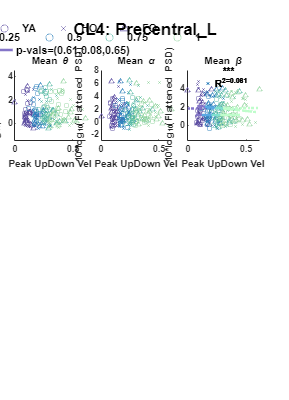

##5-theta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    group_char                       2.5197        2       1.2598         1.866    0.15679
    mean_APexc_COV                 0.022785        1     0.022785      0.033748    0.85439
    group_char:mean_APexc_COV        1.3963        2      0.69813         1.034    0.35702
    Error                            176.89      262      0.67516                         
    Total                            181.66      267                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat      pValue 
                                         _________    ________    _______    ________

    (Intercept)                            0.82365     0.34389     2.3951    0.017317
    group_char_H2000's                    -0.90625     0.53606    -1.6906    0.092105
    group_char_H3000's                    -0.75539     0.46478    -1.6252     0.10531
    mean_APexc_COV                       -0.024772    0.021246    -1.1659      0.2447
    group_char_H2000's:mean_APexc_COV     0.036356    0.028113     1.2932     0.19708
    group_char_H3000's:mean_APexc_COV     0.032341    0.0

##5-alpha_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      35.864         2      17.932        2.2484     0.1076
    mean_APexc_COV                  2.0502         1      2.0502       0.25706    0.61257
    group_char:mean_APexc_COV       17.041         2      8.5204        1.0683    0.34508
    Error                           2089.6       262      7.9755                         
    Total                           2214.8       267                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue  
                                         _________    ________    _______    __________

    (Intercept)                              5.358      1.1819     4.5333    8.8386e-06
    group_char_H2000's                     -3.6326      1.8424    -1.9717        0.0497
    group_char_H3000's                     -2.5925      1.5975    -1.6229       0.10581
    mean_APexc_COV                       -0.097311    0.073022    -1.3326       0.18381
    group_char_H2000's:mean_APexc_COV      0.12287    0.096623     1.2716       0.20464
    group_char_H3000's:mean_APexc_COV      

##5-beta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      3.0176         2       1.5088      0.63659    0.52991
    mean_APexc_COV                 0.96438         1      0.96438       0.4069    0.52411
    group_char:mean_APexc_COV       6.1391         2       3.0696       1.2951    0.27561
    Error                           620.97       262       2.3701                        
    Total                           698.69       267                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             3.2327     0.64431      5.0173    9.6822e-07
    group_char_H2000's                    -0.93356      1.0044    -0.92951       0.35348
    group_char_H3000's                    -0.87451     0.87083     -1.0042        0.3162
    mean_APexc_COV                       -0.014796    0.039807     -0.3717       0.71042
    group_char_H2000's:mean_APexc_COV     0.016907    0.052673     0.32097       0.74849
    group_char_H3000's:mean_APexc_COV

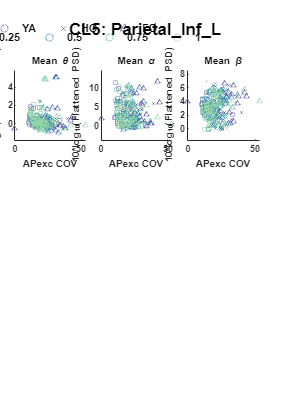

##5-theta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    ________    _______

    group_char                      0.56868         2      0.28434       0.41885    0.65824
    mean_APexc_mean                 0.37356         1      0.37356       0.55028    0.45887
    group_char:mean_APexc_mean      0.11536         2     0.057682      0.084969    0.91857
    Error                            177.86       262      0.67886                         
    Total                            181.66       267                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue 
                                          ________    _______    ________    ________

    (Intercept)                            0.61722    0.30226       2.042    0.042152
    group_char_H2000's                    -0.29952    0.41312    -0.72501     0.46909
    group_char_H3000's                    -0.33816    0.38761    -0.87243     0.38377
    mean_APexc_mean                         -3.338     5.3127    -0.62831     0.53035
    group_char_H2000's:mean_APexc_mean       0.121     7.8725    0.015369     0.98775
    group_char_H3000's:mean_APexc_mean      2.8073     7

##5-alpha_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                       15.541         2      7.7704       0.96996    0.38046
    mean_APexc_mean                  1.1446         1      1.1446       0.14288    0.70574
    group_char:mean_APexc_mean       6.5149         2      3.2574       0.40661    0.66632
    Error                            2098.9       262      8.0111                         
    Total                            2214.8       267                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE       tStat        pValue  
                                          ________    ______    ________    __________

    (Intercept)                            4.0923     1.0383      3.9412    0.00010405
    group_char_H2000's                    -1.7923     1.4192      -1.263       0.20773
    group_char_H3000's                    -1.6016     1.3315     -1.2028       0.23012
    mean_APexc_mean                       -4.7904      18.25    -0.26248       0.79316
    group_char_H2000's:mean_APexc_mean     4.4103     27.044     0.16308       0.87058
    group_char_H3000's:mean_APexc_mean     22.364

##5-beta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares      F        pValue  
                                  ____________    ___    ___________    ______    _________

    group_char                       31.405         2      15.702       6.6436    0.0015328
    mean_APexc_mean                  5.1466         1      5.1466       2.1775      0.14124
    group_char:mean_APexc_mean       9.0599         2        4.53       1.9166      0.14916
    Error                            619.25       262      2.3635                          
    Total                            698.69       267                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                            2.7527     0.56399      4.8808    1.8376e-06
    group_char_H2000's                    -1.5573     0.77084     -2.0202      0.044378
    group_char_H3000's                    0.96859     0.72325      1.3392       0.18166
    mean_APexc_mean                        4.5322       9.913     0.45719       0.64791
    group_char_H2000's:mean_APexc_mean     20.494      14.689      1.3952       0.16415
    group_char_H3000's:mean_APexc_mean    -

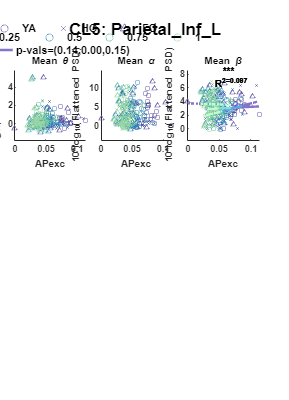

##5-theta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    group_char                      0.65757        2      0.32878       0.48368    0.61706
    mean_MLexc_COV                  0.15382        1      0.15382       0.22628    0.63469
    group_char:mean_MLexc_COV      0.093705        2     0.046853      0.068926    0.93341
    Error                             178.1      262      0.67976                         
    Total                            181.66      267                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                          Estimate        SE        tStat      pValue 
                                         __________    ________    ________    _______

    (Intercept)                             0.38195     0.23996      1.5917    0.11266
    group_char_H2000's                     -0.34724      0.3541    -0.98063    0.32768
    group_char_H3000's                     -0.13449      0.3682    -0.36526    0.71521
    mean_MLexc_COV                        0.0038167    0.016229     0.23518    0.81425
    group_char_H2000's:mean_MLexc_COV     0.0061549    0.024252     0.25379    0.79986
    group_char_H3000's:mean_MLexc_COV    -0.003169

##5-alpha_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      14.678         2      7.3388       0.91488    0.40184
    mean_MLexc_COV                  1.1924         1      1.1924       0.14865    0.70014
    group_char:mean_MLexc_COV       3.4983         2      1.7491       0.21805    0.80423
    Error                           2101.7       262      8.0216                         
    Total                           2214.8       267                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE         tStat        pValue  
                                         _________    ________    _________    __________

    (Intercept)                             4.2264     0.82433       5.1271    5.7249e-07
    group_char_H2000's                      -1.519      1.2164      -1.2488       0.21285
    group_char_H3000's                     -1.2876      1.2649       -1.018       0.30964
    mean_MLexc_COV                       -0.028587    0.055749     -0.51278       0.60854
    group_char_H2000's:mean_MLexc_COV    -0.002746     0.08331    -0.032961       0.97373
    group_char_H3000's:mean_MLexc_COV<

##5-beta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      7.0369         2      3.5184        1.4653     0.2329
    mean_MLexc_COV                  1.7949         1      1.7949       0.74751    0.38806
    group_char:mean_MLexc_COV       2.0208         2      1.0104       0.42079    0.65697
    Error                           629.12       262      2.4012                         
    Total                           698.69       267                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                          Estimate        SE         tStat        pValue  
                                         __________    ________    __________    _________

    (Intercept)                              3.0863     0.45101        6.8432    5.464e-11
    group_char_H2000's                      -1.0242     0.66552       -1.5389      0.12503
    group_char_H3000's                   -0.0047878     0.69203    -0.0069185      0.99449
    mean_MLexc_COV                       -0.0062062    0.030502      -0.20347      0.83892
    group_char_H2000's:mean_MLexc_COV      0.027074    0.045581       0.59397      0.55304
    group_char_H3000's:mean_MLex

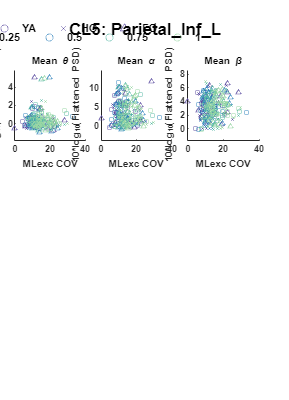

##5-theta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    _______    ________

    group_char                       5.1121         2       2.5561       3.8827    0.021791
    mean_MLexc_mean                 0.19965         1      0.19965      0.30326     0.58231
    group_char:mean_MLexc_mean       5.5782         2       2.7891       4.2366    0.015459
    Error                            172.48       262      0.65833                         
    Total                            181.66       267                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue 
                                          ________    _______    ________    ________

    (Intercept)                            0.55693    0.24935      2.2335     0.02636
    group_char_H2000's                    -0.15091    0.33712    -0.44765     0.65478
    group_char_H3000's                    -0.82946    0.32827     -2.5268      0.0121
    mean_MLexc_mean                        -1.4833     2.8567    -0.51924     0.60403
    group_char_H2000's:mean_MLexc_mean     -1.0662     3.6399    -0.29292     0.76982
    group_char_H3000's:mean_MLexc_mean      7.9076      

##5-alpha_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares        F          pValue 
                                  ____________    ___    ___________    __________    ________

    group_char                         46.959       2        23.479         2.9708    0.052991
    mean_MLexc_mean                0.00031211       1    0.00031211     3.9491e-05     0.99499
    group_char:mean_MLexc_mean           35.6       2          17.8         2.2522      0.1072
    Error                              2070.7     262        7.9033                           
    Total                              2214.8     267                                         



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    _______    __________

    (Intercept)                            4.7279     0.86396     5.4723    1.0382e-07
    group_char_H2000's                    -2.1043      1.1681    -1.8016      0.072761
    group_char_H3000's                    -2.6962      1.1374    -2.3705      0.018489
    mean_MLexc_mean                       -10.899       9.898    -1.1011       0.27185
    group_char_H2000's:mean_MLexc_mean     7.2165      12.612    0.57221       0.56767
    group_char_H3000's:mean_MLexc_mean     25.386

##5-beta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F         pValue 
                                  ____________    ___    ___________    ________    ________

    group_char                        19.77         2        9.885        4.1072    0.017524
    mean_MLexc_mean                  0.0983         1       0.0983      0.040844        0.84
    group_char:mean_MLexc_mean       1.9056         2      0.95278       0.39588     0.67349
    Error                            630.56       262       2.4067                          
    Total                            698.69       267                                       



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                             2.9645    0.47676      6.2181    1.977e-09
    group_char_H2000's                    -0.77152    0.64457     -1.1969      0.23241
    group_char_H3000's                     0.93006    0.62765      1.4818      0.13959
    mean_MLexc_mean                        0.43557      5.462    0.079744       0.9365
    group_char_H2000's:mean_MLexc_mean      1.2067     6.9595     0.17338      0.86248
    group_char_H3000's:mean_MLexc_mean     -4.1915

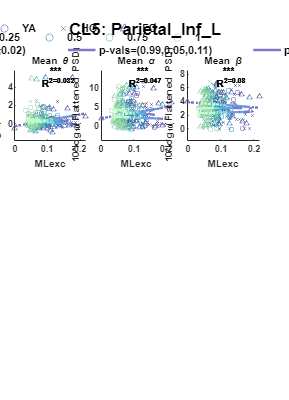

##5-theta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F       pValue 
                               ____________    ___    ___________    _______    _______

    group_char                   0.49887         2      0.24943      0.36767     0.6927
    mean_StepDur                 0.12487         1      0.12487      0.18407    0.66826
    group_char:mean_StepDur      0.38094         2      0.19047      0.28076    0.75544
    Error                         177.75       262      0.67842                        
    Total                         181.66       267                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate       SE        tStat       pValue 
                                       _________    _______    ________    ________

    (Intercept)                          0.52514    0.25281      2.0772    0.038757
    group_char_H2000's                 -0.099671    0.41458    -0.24042      0.8102
    group_char_H3000's                  -0.36404     0.4261    -0.85435     0.39369
    mean_StepDur                       -0.099305     0.2621    -0.37889     0.70508
    group_char_H2000's:mean_StepDur     -0.22867    0.48293     -0.4735     0.63625
    group_char_H3000's:mean_StepDur      0.23624    0.54173     0.43608  

##5-alpha_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F       pValue 
                               ____________    ___    ___________    _______    _______

    group_char                    8.1275         2      4.0638       0.50655    0.60316
    mean_StepDur                  2.8818         1      2.8818       0.35922    0.54946
    group_char:mean_StepDur       2.5114         2      1.2557       0.15652    0.85519
    Error                         2101.9       262      8.0224                         
    Total                         2214.8       267                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate      SE        tStat        pValue  
                                       ________    _______    ________    __________

    (Intercept)                          3.5643    0.86936      4.0999    5.5188e-05
    group_char_H2000's                  -1.2544     1.4256    -0.87991       0.37972
    group_char_H3000's                  -1.1341     1.4653    -0.77398       0.43964
    mean_StepDur                        0.29269    0.90129     0.32475       0.74563
    group_char_H2000's:mean_StepDur    -0.32778     1.6607    -0.19738       0.84369
    group_char_H3000's:mean_StepDur     0.84451     1.8629     0.4

##5-beta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F        pValue 
                               ____________    ___    ___________    _______    ________

    group_char                    12.083         2       6.0417       2.5151    0.082803
    mean_StepDur                 0.56455         1      0.56455      0.23502     0.62823
    group_char:mean_StepDur       1.8375         2      0.91877      0.38248     0.68255
    Error                         629.36       262       2.4021                         
    Total                         698.69       267                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate      SE        tStat        pValue  
                                       ________    _______    ________    __________

    (Intercept)                          2.6993    0.47571      5.6742    3.6835e-08
    group_char_H2000's                 -0.86035    0.78011     -1.1029        0.2711
    group_char_H3000's                   1.1399     0.8018      1.4216       0.15632
    mean_StepDur                        0.33101    0.49319     0.67117        0.5027
    group_char_H2000's:mean_StepDur      0.3186    0.90872      0.3506       0.72617
    group_char_H3000's:mean_StepDur    -0.69429     1.0194    -0.68

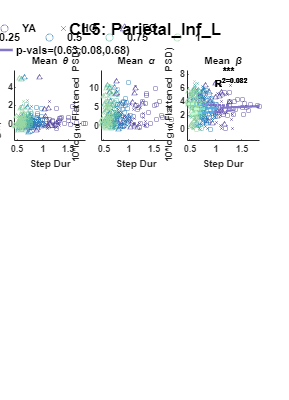

##5-theta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                     0.98219         2      0.49109      0.72562      0.485
    mean_UDexc_COV                 0.66822         1      0.66822      0.98734    0.32131
    group_char:mean_UDexc_COV      0.34704         2      0.17352      0.25639    0.77404
    Error                           177.32       262      0.67679                        
    Total                           181.66       267                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue  
                                         _________    ________    ________    _________

    (Intercept)                            0.62078     0.21956      2.8274    0.0050546
    group_char_H2000's                    -0.28533     0.31159    -0.91573      0.36065
    group_char_H3000's                    -0.36591     0.32558     -1.1238      0.26211
    mean_UDexc_COV                       -0.015228     0.01661    -0.91675      0.36012
    group_char_H2000's:mean_UDexc_COV    0.0030831    0.022263     0.13848      0.88996
    group_char_H3000's:mean_UDexc_COV      

##5-alpha_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    group_char                      22.565         2       11.282        1.4039    0.24749
    mean_UDexc_COV                 0.33888         1      0.33888      0.042167    0.83746
    group_char:mean_UDexc_COV      0.74142         2      0.37071      0.046127    0.95493
    Error                           2105.6       262       8.0367                         
    Total                           2214.8       267                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             4.0787     0.75658       5.391    1.5637e-07
    group_char_H2000's                     -1.7989      1.0737     -1.6754      0.095058
    group_char_H3000's                    -0.86362      1.1219    -0.76975       0.44214
    mean_UDexc_COV                       -0.020324    0.057239    -0.35507       0.72282
    group_char_H2000's:mean_UDexc_COV     0.020516    0.076719     0.26742       0.78936
    group_char_H3000's:mean_UDexc_COV

##5-beta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      7.8279         2       3.9139       1.6248    0.19892
    mean_UDexc_COV                 0.28138         1      0.28138      0.11681    0.73279
    group_char:mean_UDexc_COV       1.1556         2      0.57781      0.23987     0.7869
    Error                           631.11       262       2.4088                        
    Total                           698.69       267                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                          Estimate        SE        tStat        pValue  
                                         __________    ________    ________    __________

    (Intercept)                              3.1094     0.41421      7.5069    9.4924e-13
    group_char_H2000's                     -0.83853     0.58784     -1.4265       0.15492
    group_char_H3000's                      0.17935     0.61424     0.29199       0.77052
    mean_UDexc_COV                       -0.0089268    0.031337    -0.28486       0.77597
    group_char_H2000's:mean_UDexc_COV      0.014371    0.042001     0.34216        0.7325
    group_char_H3000's:mean_UDexc_COV</

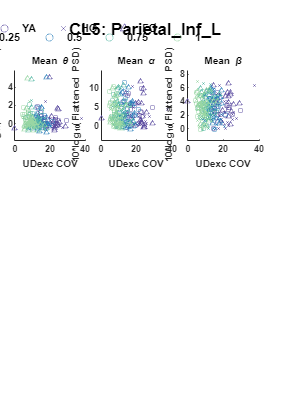

##5-theta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                       0.70822        2      0.35411      0.52138    0.59432
    mean_UDexc_mean                 0.078544        1     0.078544      0.11564    0.73408
    group_char:mean_UDexc_mean       0.31533        2      0.15767      0.23214      0.793
    Error                             177.95      262      0.67918                        
    Total                             181.66      267                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate       SE         tStat      pValue 
                                          _________    _______    _________    _______

    (Intercept)                             0.35171    0.25128       1.3997    0.16279
    group_char_H2000's                      -0.3152    0.35042     -0.89951    0.36921
    group_char_H3000's                    -0.016905    0.35026    -0.048264    0.96154
    mean_UDexc_mean                          3.4485     9.8277       0.3509    0.72595
    group_char_H2000's:mean_UDexc_mean       1.9969     13.509      0.14782     0.8826
    group_char_H3000's:mean_UDexc_mean      -6.71

##5-alpha_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    ________    _______

    group_char                       5.6323         2       2.8161       0.35152    0.70395
    mean_UDexc_mean                 0.23609         1      0.23609      0.029469    0.86383
    group_char:mean_UDexc_mean       7.5198         2       3.7599       0.46932    0.62595
    Error                              2099       262       8.0113                         
    Total                            2214.8       267                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                             3.1181    0.86302      3.6131    0.0003627
    group_char_H2000's                    -0.61705     1.2035    -0.51272      0.60858
    group_char_H3000's                     0.36708      1.203     0.30515      0.76049
    mean_UDexc_mean                         29.567     33.753     0.87598      0.38185
    group_char_H2000's:mean_UDexc_mean      -38.49     46.397    -0.82958      0.40753
    group_char_H3000's:mean_UDexc_mean     -40.45

##5-beta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    _______    ________

    group_char                        11.96         2         5.98       2.4861    0.085196
    mean_UDexc_mean                 0.56863         1      0.56863       0.2364     0.62723
    group_char:mean_UDexc_mean       1.7327         2      0.86634      0.36016     0.69791
    Error                            630.21       262       2.4054                         
    Total                            698.69       267                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                             2.8278    0.47289      5.9799    7.2859e-09
    group_char_H2000's                    -0.28103    0.65946    -0.42616       0.67034
    group_char_H3000's                      1.0927    0.65916      1.6576      0.098586
    mean_UDexc_mean                         7.1623     18.495     0.38726       0.69888
    group_char_H2000's:mean_UDexc_mean     -15.395     25.423    -0.60557       0.54533
    group_char_H3000's:mean_UDexc_mean     

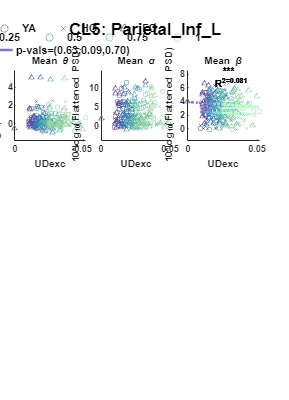

##5-theta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                     0.56957         2      0.28478      0.41962    0.65774
    mean_StanceDur                 0.11472         1      0.11472      0.16904    0.68131
    group_char:mean_StanceDur      0.31626         2      0.15813        0.233    0.79232
    Error                           177.81       262      0.67867                        
    Total                           181.66       267                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate       SE        tStat       pValue 
                                         _________    _______    ________    ________

    (Intercept)                            0.51047    0.21074      2.4222    0.016104
    group_char_H2000's                    -0.15016    0.34159    -0.43958      0.6606
    group_char_H3000's                    -0.32454    0.35718    -0.90862     0.36438
    mean_StanceDur                       -0.060627    0.15482    -0.39159     0.69568
    group_char_H2000's:mean_StanceDur     -0.11988    0.28577    -0.41951     0.67519
    group_char_H3000's:mean_StanceDur      0.13498    0.3

##5-alpha_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      12.628         2      6.3138       0.78772    0.45596
    mean_StanceDur                  4.5562         1      4.5562       0.56843    0.45156
    group_char:mean_StanceDur        3.191         2      1.5955       0.19905    0.81963
    Error                             2100       262      8.0154                         
    Total                           2214.8       267                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate      SE        tStat        pValue  
                                         ________    _______    ________    __________

    (Intercept)                            3.5756    0.72425       4.937    1.4139e-06
    group_char_H2000's                    -1.3289     1.1739      -1.132       0.25866
    group_char_H3000's                    -1.1257     1.2275    -0.91707       0.35995
    mean_StanceDur                        0.20422    0.53207     0.38381       0.70143
    group_char_H2000's:mean_StanceDur    -0.17031    0.98209    -0.17341       0.86246
    group_char_H3000's:mean_StanceDur     0.60879 

##5-beta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                        13.4         2       6.7001       2.7873    0.063416
    mean_StanceDur                 0.38558         1      0.38558       0.1604     0.68911
    group_char:mean_StanceDur       1.4276         2       0.7138      0.29695     0.74333
    Error                            629.8       262       2.4038                         
    Total                           698.69       267                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate      SE        tStat        pValue  
                                         ________    _______    ________    __________

    (Intercept)                            2.7169    0.39662      6.8501    5.2452e-11
    group_char_H2000's                   -0.67485    0.64287     -1.0497       0.29481
    group_char_H3000's                     1.0672    0.67221      1.5876       0.11358
    mean_StanceDur                        0.22712    0.29138     0.77948        0.4364
    group_char_H2000's:mean_StanceDur    0.060175    0.53782     0.11189         0.911
    group_char_H3000's:mean_StanceDur    -0.43577  

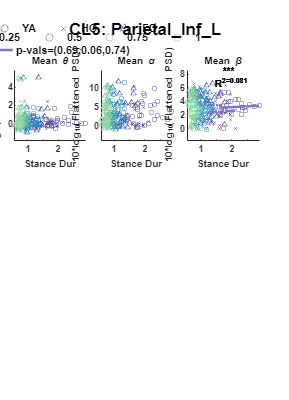

##5-theta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F       pValue 
                                    ____________    ___    ___________    _______    _______

    group_char                        0.49156         2      0.24578      0.36227    0.69644
    mean_GaitCycleDur                 0.12701         1      0.12701      0.18721    0.66561
    group_char:mean_GaitCycleDur      0.37308         2      0.18654      0.27495    0.75983
    Error                              177.75       262      0.67844                        
    Total                              181.66       267                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate       SE        tStat       pValue 
                                            _________    _______    ________    ________

    (Intercept)                               0.52518    0.25261       2.079    0.038592
    group_char_H2000's                       -0.10121    0.41363    -0.24469     0.80688
    group_char_H3000's                       -0.36131    0.42581    -0.84853     0.39691
    mean_GaitCycleDur                       -0.049648    0.13086     -0.3794      0.7047
    group_char_H2000's:mean_GaitCycleDur     -0.11325    0.24064    -0.47061     0.63831
    group_char_H3000's:mean_GaitCycleDur</

##5-alpha_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F       pValue 
                                    ____________    ___    ___________    _______    _______

    group_char                         8.0397         2      4.0198       0.50108    0.60645
    mean_GaitCycleDur                  2.9132         1      2.9132       0.36314    0.54729
    group_char:mean_GaitCycleDur       2.4837         2      1.2418        0.1548    0.85667
    Error                              2101.8       262      8.0223                         
    Total                              2214.8       267                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate      SE        tStat        pValue  
                                            ________    _______    ________    __________

    (Intercept)                               3.5568    0.86867      4.0945    5.6405e-05
    group_char_H2000's                       -1.2478     1.4224     -0.8773       0.38113
    group_char_H3000's                       -1.1235     1.4642    -0.76729        0.4436
    mean_GaitCycleDur                        0.15038    0.44999     0.33418       0.73851
    group_char_H2000's:mean_GaitCycleDur    -0.16733     0.8275    -0.20221       0.83991
    group_char_H3000's:mean_GaitCyc

##5-beta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F        pValue 
                                    ____________    ___    ___________    _______    ________

    group_char                         12.317         2       6.1584       2.5642    0.078915
    mean_GaitCycleDur                 0.57271         1      0.57271      0.23846     0.62573
    group_char:mean_GaitCycleDur       1.9171         2      0.95854       0.3991     0.67133
    Error                              629.26       262       2.4017                         
    Total                              698.69       267                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate      SE        tStat        pValue  
                                            ________    _______    ________    __________

    (Intercept)                               2.6983     0.4753      5.6771    3.6286e-08
    group_char_H2000's                      -0.86865    0.77826     -1.1162       0.26538
    group_char_H3000's                        1.1474    0.80117      1.4321        0.1533
    mean_GaitCycleDur                        0.16595    0.24621       0.674       0.50091
    group_char_H2000's:mean_GaitCycleDur     0.16456    0.45277     0.36344       0.71657
    group_char_H3000's:mean_GaitCycl

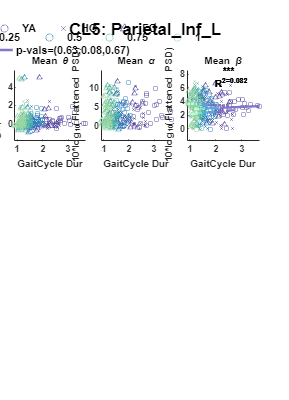

##5-theta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares        F        pValue 
                                          ____________    ___    ___________    _________    _______

    group_char                               0.61591        2       0.30796       0.45294    0.63626
    mean_PeakUpDownVel_mean                  0.19997        1       0.19997       0.29411    0.58806
    group_char:mean_PeakUpDownVel_mean     0.0043993        2     0.0021997     0.0032352    0.99677
    Error                                     178.14      262       0.67991                         
    Total                                     181.66      267                                       



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate       SE         tStat      pValue 
                                                  _________    _______    _________    _______

    (Intercept)                                     0.37455    0.20223       1.8521    0.06514
    group_char_H2000's                             -0.27269    0.28891     -0.94384    0.34612
    group_char_H3000's                             -0.16488    0.29171     -0.56523     0.5724
    mean_PeakUpDownVel_mean                         0.25243    0.77042      0.32765    0.74344
    group_char_H2000's:mean_PeakUpDownVel_mean     0.014402       1.06     0.013587    0.98917
  

##5-alpha_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F       pValue 
                                          ____________    ___    ___________    _______    _______

    group_char                               13.907         2      6.9537       0.87104    0.41973
    mean_PeakUpDownVel_mean                  1.7244         1      1.7244         0.216    0.64249
    group_char:mean_PeakUpDownVel_mean       13.067         2      6.5333       0.81838    0.44227
    Error                                    2091.6       262      7.9832                         
    Total                                    2214.8       267                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat        pValue  
                                                  ________    _______    ________    __________

    (Intercept)                                     3.3771    0.69297      4.8734    1.9017e-06
    group_char_H2000's                            -0.78145    0.98999    -0.78935       0.43062
    group_char_H3000's                             0.54164    0.99956     0.54187       0.58837
    mean_PeakUpDownVel_mean                         1.8995     2.6399     0.71952       0.47246
    group_char_H2000's:mean_PeakUpDownVel_mean     -3.1274     3.6322    -0.86104          

##5-beta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares      F        pValue  
                                          ____________    ___    ___________    ______    _________

    group_char                               25.461         2       12.73       5.3764    0.0051489
    mean_PeakUpDownVel_mean                  7.4108         1      7.4108       3.1298     0.078035
    group_char:mean_PeakUpDownVel_mean       4.7537         2      2.3769       1.0038      0.36788
    Error                                    620.37       262      2.3678                          
    Total                                    698.69       267                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat        pValue  
                                                  ________    _______    ________    __________

    (Intercept)                                     3.0638     0.3774      8.1183    1.8541e-14
    group_char_H2000's                            -0.45885    0.53916    -0.85105       0.39552
    group_char_H3000's                              1.2825    0.54437      2.3559      0.019214
    mean_PeakUpDownVel_mean                       -0.26568     1.4377    -0.18479       0.85353
    group_char_H2000's:mean_PeakUpDownVel_mean    -0.75318     1.9781    -0.38076       0.70

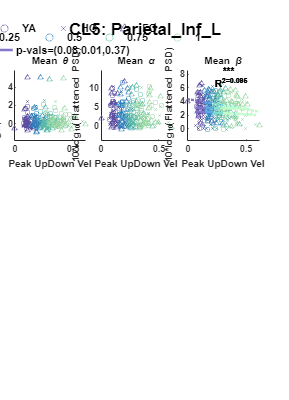

##6-theta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      3.7224         2       1.8612       2.0987    0.12594
    mean_APexc_COV                 0.41244         1      0.41244      0.46507    0.49624
    group_char:mean_APexc_COV       2.2872         2       1.1436       1.2896     0.2782
    Error                           143.67       162      0.88683                        
    Total                           156.88       167                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE         tStat       pValue  
                                         _________    ________    _________    _________

    (Intercept)                             1.3986     0.46692       2.9954    0.0031718
    group_char_H2000's                     -1.4397      0.7428      -1.9382     0.054342
    group_char_H3000's                   -0.044587     0.84232    -0.052933      0.95785
    mean_APexc_COV                       0.0039091    0.028703      0.13619      0.89184
    group_char_H2000's:mean_APexc_COV     0.039294    0.037906       1.0366      0.30146
    group_char_H3000's:mean_APexc_COV

##6-alpha_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue  
                                 ____________    ___    ___________    _______    _________

    group_char                      10.476         2       5.2381       5.4296    0.0052195
    mean_APexc_COV                 0.47805         1      0.47805      0.49553      0.48248
    group_char:mean_APexc_COV       9.7171         2       4.8586       5.0362    0.0075527
    Error                           156.29       162      0.96473                          
    Total                           168.94       167                                       



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE         tStat       pValue  
                                         _________    ________    _________    _________

    (Intercept)                            0.76218       0.487       1.5651      0.11952
    group_char_H2000's                     -2.0544     0.77474      -2.6517    0.0088046
    group_char_H3000's                     0.79933     0.87854      0.90984      0.36426
    mean_APexc_COV                       -0.002487    0.029937    -0.083075      0.93389
    group_char_H2000's:mean_APexc_COV     0.080978    0.039536       2.0482     0.042151
    group_char_H3000's:mean_APexc_COV

##6-beta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares      F         pValue  
                                 ____________    ___    ___________    ______    __________

    group_char                      21.967         2      10.983       9.8806    8.9355e-05
    mean_APexc_COV                  14.489         1      14.489       13.034    0.00040743
    group_char:mean_APexc_COV       14.378         2      7.1889       6.4671     0.0019855
    Error                           180.08       162      1.1116                           
    Total                           214.86       167                                       



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                              1.676     0.52276       3.206     0.0016215
    group_char_H2000's                     -3.5401     0.83163     -4.2568    3.5011e-05
    group_char_H3000's                     -2.5311     0.94305     -2.6839     0.0080323
    mean_APexc_COV                       -0.022799    0.032135    -0.70947       0.47905
    group_char_H2000's:mean_APexc_COV       0.1506    0.042439      3.5487    0.00050681
    group_char_H3000's:mean_APexc_COV

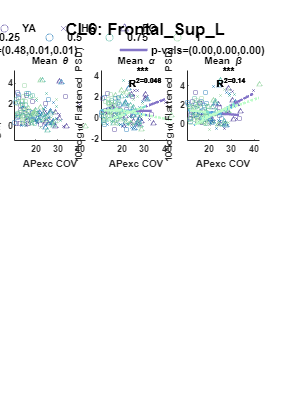

##6-theta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares      F        pValue 
                                  ____________    ___    ___________    ______    ________

    group_char                       1.8198         2      0.90989      1.0653     0.34704
    mean_APexc_mean                  5.6936         1       5.6936       6.666    0.010712
    group_char:mean_APexc_mean       5.5737         2       2.7868      3.2628    0.040813
    Error                            138.37       162      0.85413                        
    Total                            156.88       167                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat      pValue  
                                          ________    _______    _______    _________

    (Intercept)                            1.3043      0.3969     3.2863    0.0012447
    group_char_H2000's                    0.27503     0.56769    0.48447      0.62871
    group_char_H3000's                    0.92088     0.63501     1.4502      0.14894
    mean_APexc_mean                        2.8417      6.9502    0.40887      0.68317
    group_char_H2000's:mean_APexc_mean    -16.933       10.98    -1.5422      0.12497
    group_char_H3000's:mean_APexc_mean    -32.383      1

##6-alpha_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares        F        pValue 
                                  ____________    ___    ___________    _________    _______

    group_char                        3.7136        2        1.8568        1.8299    0.16373
    mean_APexc_mean                0.0061726        1     0.0061726     0.0060832    0.93793
    group_char:mean_APexc_mean         2.721        2        1.3605        1.3408    0.26453
    Error                             164.38      162        1.0147                         
    Total                             168.94      167                                       



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue 
                                          ________    _______    ________    ________

    (Intercept)                               1.14    0.43261      2.6352    0.009225
    group_char_H2000's                     -1.1673    0.61876     -1.8866    0.061008
    group_char_H3000's                    -0.37305    0.69214    -0.53899     0.59064
    mean_APexc_mean                        -7.5959     7.5753     -1.0027     0.31749
    group_char_H2000's:mean_APexc_mean      19.054     11.967      1.5922      0.1133
    group_char_H3000's:mean_APexc_mean      2.3906     1

##6-beta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares      F        pValue  
                                  ____________    ___    ___________    ______    _________

    group_char                       14.176         2      7.0882       5.7961    0.0037049
    mean_APexc_mean                   1.373         1       1.373       1.1227      0.29092
    group_char:mean_APexc_mean       12.587         2      6.2934       5.1462    0.0068103
    Error                            198.11       162      1.2229                          
    Total                            214.86       167                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                              1.571    0.47492      3.3079    0.0011582
    group_char_H2000's                     -2.0604    0.67928     -3.0333    0.0028184
    group_char_H3000's                    0.049728    0.75984    0.065446       0.9479
    mean_APexc_mean                        -4.6481     8.3164    -0.55891        0.577
    group_char_H2000's:mean_APexc_mean      38.421     13.138      2.9244     0.003946
    group_char_H3000's:mean_APexc_mean     -4.4463

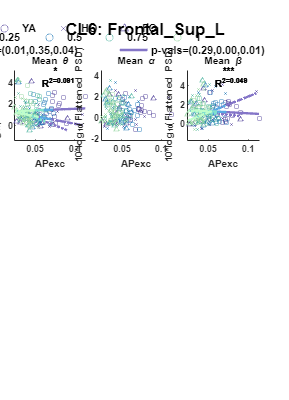

##6-theta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                     0.81989         2      0.40995      0.46414     0.62951
    mean_MLexc_COV                  2.4862         1       2.4862       2.8149    0.095318
    group_char:mean_MLexc_COV      0.44931         2      0.22465      0.25436     0.77573
    Error                           143.08       162      0.88323                         
    Total                           156.88       167                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue  
                                         _________    ________    ________    _________

    (Intercept)                            0.95323     0.35331       2.698    0.0077149
    group_char_H2000's                    -0.50841     0.54042    -0.94076      0.34823
    group_char_H3000's                    -0.10526      0.5862    -0.17956      0.85772
    mean_MLexc_COV                        0.032932    0.021786      1.5116      0.13258
    group_char_H2000's:mean_MLexc_COV    0.0043743     0.03639      0.1202      0.90447
    group_char_H3000's:mean_MLexc_COV     -

##6-alpha_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      4.4418         2       2.2209       2.1946    0.11471
    mean_MLexc_COV                 0.34675         1      0.34675      0.34264    0.55912
    group_char:mean_MLexc_COV       3.1861         2       1.5931       1.5742    0.21033
    Error                           163.94       162        1.012                        
    Total                           168.94       167                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat      pValue 
                                         _________    ________    _______    ________

    (Intercept)                             1.1556     0.37819     3.0555    0.002628
    group_char_H2000's                     -1.1088     0.57847    -1.9168    0.057023
    group_char_H3000's                    -0.96159     0.62747    -1.5325     0.12735
    mean_MLexc_COV                       -0.028096     0.02332    -1.2048     0.23003
    group_char_H2000's:mean_MLexc_COV     0.061567    0.038953     1.5806     0.11593
    group_char_H3000's:mean_MLexc_COV      0.05256    0.0

##6-beta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      2.1842         2       1.0921      0.84226    0.43261
    mean_MLexc_COV                  0.1889         1       0.1889      0.14569    0.70319
    group_char:mean_MLexc_COV       1.8189         2      0.90945      0.70141    0.49739
    Error                           210.05       162       1.2966                        
    Total                           214.86       167                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             1.7828     0.42808      4.1647    5.0555e-05
    group_char_H2000's                    -0.53861     0.65479    -0.82257       0.41196
    group_char_H3000's                    -0.88558     0.71025     -1.2468       0.21425
    mean_MLexc_COV                       -0.030331    0.026396     -1.1491       0.25223
    group_char_H2000's:mean_MLexc_COV     0.015027    0.044092     0.34082       0.73368
    group_char_H3000's:mean_MLexc_COV

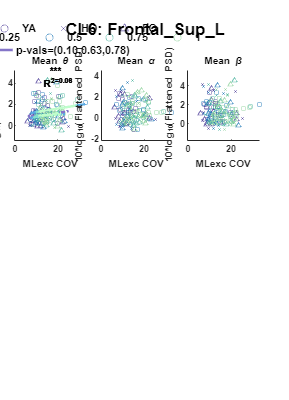

##6-theta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                        1.149         2      0.57451      0.64066    0.52827
    mean_MLexc_mean                  0.6576         1       0.6576      0.73331    0.39308
    group_char:mean_MLexc_mean      0.41564         2      0.20782      0.23175    0.79341
    Error                            145.27       162      0.89675                        
    Total                            156.88       167                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                             1.5933    0.34891      4.5664    9.7731e-06
    group_char_H2000's                     -0.2876    0.48717    -0.59035       0.55578
    group_char_H3000's                    -0.58028    0.51304     -1.1311        0.2597
    mean_MLexc_mean                        -1.7118     4.2585    -0.40196       0.68824
    group_char_H2000's:mean_MLexc_mean      -2.077     5.3616    -0.38739       0.69898
    group_char_H3000's:mean_MLexc_mean    

##6-alpha_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    ________    _______

    group_char                        3.5035        2       1.7517        1.7224    0.18189
    mean_MLexc_mean                 0.027412        1     0.027412      0.026954     0.8698
    group_char:mean_MLexc_mean        2.3421        2       1.1711        1.1515    0.31875
    Error                             164.76      162        1.017                         
    Total                             168.94      167                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                             1.0623    0.37157      2.8588    0.0048121
    group_char_H2000's                     -0.9612    0.51881     -1.8527     0.065746
    group_char_H3000's                    -0.43989    0.54636    -0.80513      0.42192
    mean_MLexc_mean                        -4.3717     4.5351    -0.96397       0.3365
    group_char_H2000's:mean_MLexc_mean      8.4309     5.7098      1.4766      0.14174
    group_char_H3000's:mean_MLexc_mean      3.501

##6-beta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    _______    ________

    group_char                       9.7449         2       4.8724       3.8774    0.022654
    mean_MLexc_mean                 0.40454         1      0.40454      0.32192     0.57124
    group_char:mean_MLexc_mean        7.266         2        3.633        2.891    0.058388
    Error                            203.58       162       1.2566                         
    Total                            214.86       167                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                           Estimate       SE         tStat         pValue  
                                          __________    _______    __________    __________

    (Intercept)                               1.4953    0.41303        3.6204    0.00039296
    group_char_H2000's                       -1.4038    0.57671       -2.4341      0.016014
    group_char_H3000's                    -0.0025879    0.60733    -0.0042611       0.99661
    mean_MLexc_mean                          -2.3138     5.0412      -0.45897       0.64687
    group_char_H2000's:mean_MLexc_mean        12.173      6.347        1.9179      0.056883
    group_char_H3000's:m

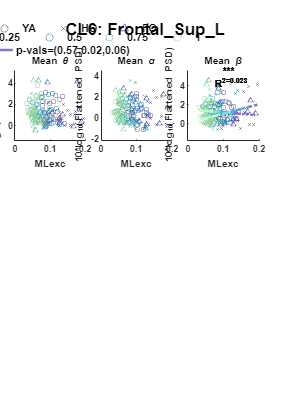

##6-theta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F        pValue 
                               ____________    ___    ___________    _______    ________

    group_char                   0.58534         2      0.29267      0.33507     0.71579
    mean_StepDur                  4.0281         1       4.0281       4.6116    0.033244
    group_char:mean_StepDur       3.5466         2       1.7733       2.0302     0.13464
    Error                          141.5       162      0.87347                         
    Total                         156.88       167                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                        Estimate       SE         tStat        pValue  
                                       __________    _______    _________    __________

    (Intercept)                            1.4672    0.32693       4.4877    1.3597e-05
    group_char_H2000's                    0.48223    0.59796      0.80646       0.42116
    group_char_H3000's                    0.23628    0.67945      0.34775       0.72848
    mean_StepDur                       -0.0073601    0.33371    -0.022055       0.98243
    group_char_H2000's:mean_StepDur       -1.3141    0.71618      -1.8349       0.06836
    group_char_H3000's:mean_StepDur         -

##6-alpha_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F        pValue 
                               ____________    ___    ___________    ________    _______

    group_char                    0.29557        2      0.14779        0.1438    0.86617
    mean_StepDur                 0.099199        1     0.099199      0.096524    0.75644
    group_char:mean_StepDur       0.57734        2      0.28867       0.28088    0.75548
    Error                          166.49      162       1.0277                         
    Total                          168.94      167                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate      SE        tStat       pValue 
                                       ________    _______    ________    ________

    (Intercept)                         0.71133    0.35462      2.0059    0.046535
    group_char_H2000's                  0.18626    0.64861     0.28717     0.77435
    group_char_H3000's                 -0.26637      0.737    -0.36142     0.71826
    mean_StepDur                       0.012523    0.36198    0.034595     0.97245
    group_char_H2000's:mean_StepDur    -0.54419    0.77685    -0.70051     0.48461
    group_char_H3000's:mean_StepDur     0.13688    0.97155     0.14089     0.888

##6-beta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F       pValue 
                               ____________    ___    ___________    _______    _______

    group_char                   0.93595         2      0.46797      0.35802    0.69961
    mean_StepDur                 0.34779         1      0.34779      0.26607    0.60668
    group_char:mean_StepDur      0.37142         2      0.18571      0.14207    0.86766
    Error                         211.76       162       1.3071                        
    Total                         214.86       167                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate       SE         tStat       pValue  
                                       _________    _______    _________    _________

    (Intercept)                           1.2109    0.39994       3.0278    0.0028671
    group_char_H2000's                  -0.59412    0.73149      -0.8122      0.41787
    group_char_H3000's                  0.012769    0.83118     0.015363      0.98776
    mean_StepDur                         0.11362    0.40823      0.27832      0.78112
    group_char_H2000's:mean_StepDur      0.44184    0.87611      0.50432      0.61472
    group_char_H3000's:mean_StepDur    -0.090376     1.0957 

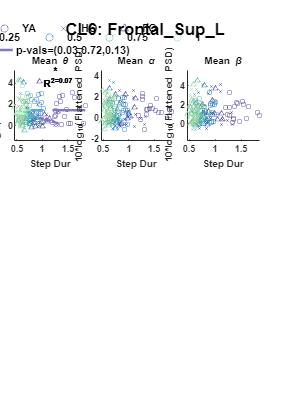

##6-theta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                      2.3817         2       1.1909        1.347     0.26291
    mean_UDexc_COV                   3.164         1        3.164       3.5788    0.060304
    group_char:mean_UDexc_COV      0.35896         2      0.17948      0.20301     0.81647
    Error                           143.22       162      0.88407                         
    Total                           156.88       167                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                          Estimate        SE        tStat       pValue  
                                         __________    ________    ________    _________

    (Intercept)                              1.8302     0.28717      6.3733    1.841e-09
    group_char_H2000's                     -0.69287     0.42252     -1.6399      0.10297
    group_char_H3000's                     -0.35373     0.51928    -0.68118      0.49673
    mean_UDexc_COV                        -0.029466    0.021108      -1.396      0.16463
    group_char_H2000's:mean_UDexc_COV      0.014692    0.029878     0.49173      0.62358
    group_char_H3000's:mean_UDexc_COV

##6-alpha_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                      2.0178         2       1.0089       1.0031     0.36903
    mean_UDexc_COV                  3.1555         1       3.1555       3.1372    0.078403
    group_char:mean_UDexc_COV       1.1716         2      0.58582      0.58242     0.55971
    Error                           162.94       162       1.0058                         
    Total                           168.94       167                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             1.1958     0.30631      3.9038    0.00013866
    group_char_H2000's                    -0.62645     0.45067       -1.39       0.16643
    group_char_H3000's                    -0.14983     0.55389     -0.2705       0.78712
    mean_UDexc_COV                       -0.037676    0.022515     -1.6734      0.096178
    group_char_H2000's:mean_UDexc_COV     0.031849    0.031869     0.99937       0.31911
    group_char_H3000's:mean_UDexc_COV

##6-beta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    group_char                      1.8143         2      0.90713        0.6938    0.50115
    mean_UDexc_COV                 0.11358         1      0.11358      0.086868    0.76857
    group_char:mean_UDexc_COV       0.6574         2       0.3287        0.2514    0.77802
    Error                           211.81       162       1.3075                         
    Total                           214.86       167                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                          Estimate         SE         tStat        pValue  
                                         ___________    ________    _________    __________

    (Intercept)                               1.4744     0.34923       4.2219    4.0262e-05
    group_char_H2000's                      -0.57591     0.51383      -1.1208       0.26402
    group_char_H3000's                     -0.053949     0.63151    -0.085429       0.93203
    mean_UDexc_COV                         -0.012644     0.02567     -0.49257       0.62298
    group_char_H2000's:mean_UDexc_COV       0.023339    0.036335      0.64232       0.52157
    group_char_H3000's:me

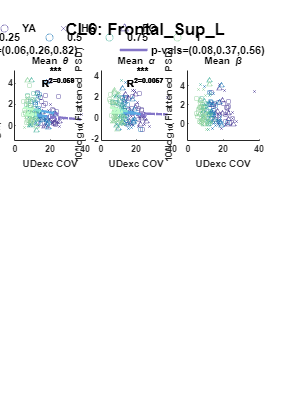

##6-theta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    ________    _______

    group_char                       1.6781         2      0.83903       0.93485    0.39475
    mean_UDexc_mean                 0.95942         1      0.95942         1.069    0.30271
    group_char:mean_UDexc_mean      0.15744         2     0.078721      0.087711    0.91607
    Error                             145.4       162       0.8975                         
    Total                            156.88       167                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                              1.278    0.33639      3.7991    0.00020511
    group_char_H2000's                    -0.67453    0.49848     -1.3532       0.17789
    group_char_H3000's                     -0.3992    0.52027     -0.7673       0.44402
    mean_UDexc_mean                          7.773     13.522     0.57486       0.56619
    group_char_H2000's:mean_UDexc_mean      5.0285     18.781     0.26774       0.78924
    group_char_H3000's:mean_UDexc_mean    

##6-alpha_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                       2.2006         2       1.1003       1.0909    0.33837
    mean_UDexc_mean                   1.729         1        1.729       1.7143    0.19229
    group_char:mean_UDexc_mean       1.5299         2      0.76496      0.75842    0.47006
    Error                             163.4       162       1.0086                        
    Total                            168.94       167                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat      pValue 
                                          ________    _______    ________    _______

    (Intercept)                            0.50989    0.35661      1.4298    0.15469
    group_char_H2000's                    -0.68017    0.52844     -1.2871    0.19989
    group_char_H3000's                    0.049865    0.55153    0.090412    0.92807
    mean_UDexc_mean                         9.0758     14.334     0.63315    0.52753
    group_char_H2000's:mean_UDexc_mean      16.041      19.91     0.80567    0.42161
    group_char_H3000's:mean_UDexc_mean      -9.525     21.755  

##6-beta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                       3.6042         2       1.8021       1.3922     0.2515
    mean_UDexc_mean                 0.70852         1      0.70852      0.54734    0.46048
    group_char:mean_UDexc_mean       2.0198         2       1.0099      0.78016    0.46005
    Error                            209.71       162       1.2945                        
    Total                            214.86       167                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                             1.4766    0.40399       3.655    0.00034709
    group_char_H2000's                    -0.99772    0.59866     -1.6666      0.097528
    group_char_H3000's                    -0.40802    0.62482    -0.65302       0.51467
    mean_UDexc_mean                        -6.8545     16.239     -0.4221       0.67351
    group_char_H2000's:mean_UDexc_mean      28.168     22.556      1.2488       0.21353
    group_char_H3000's:mean_UDexc_mean     

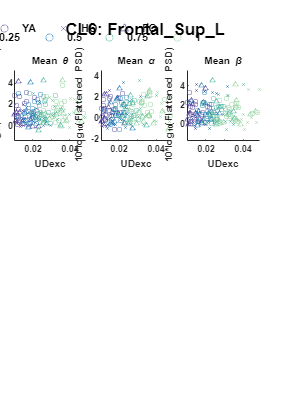

##6-theta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                     0.057799        2       0.0289      0.03275     0.96779
    mean_StanceDur                   2.9467        1       2.9467       3.3393    0.069483
    group_char:mean_StanceDur        2.2026        2       1.1013        1.248     0.28981
    Error                            142.95      162      0.88243                         
    Total                            156.88      167                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate       SE        tStat        pValue  
                                         _________    _______    ________    __________

    (Intercept)                             1.5094    0.27403       5.508    1.3989e-07
    group_char_H2000's                      0.1025    0.48626     0.21079       0.83332
    group_char_H3000's                   -0.046054    0.56314    -0.08178       0.93492
    mean_StanceDur                       -0.038796     0.1985    -0.19544       0.84529
    group_char_H2000's:mean_StanceDur     -0.60257    0.41392     -1.4558       0.14739
    group_char_H3000's:mean_StanceDur     -

##6-alpha_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares        F        pValue 
                                 ____________    ___    ___________    _________    _______

    group_char                      0.56669        2       0.28335       0.27576    0.75935
    mean_StanceDur                0.0010828        1     0.0010828     0.0010538    0.97414
    group_char:mean_StanceDur       0.66963        2       0.33481       0.32585    0.72238
    Error                            166.45      162        1.0275                         
    Total                            168.94      167                                       



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate      SE        tStat       pValue 
                                         ________    _______    ________    ________

    (Intercept)                           0.71396     0.2957      2.4144    0.016874
    group_char_H2000's                    0.04078    0.52471    0.077719     0.93815
    group_char_H3000's                   -0.41865    0.60767    -0.68894     0.49185
    mean_StanceDur                       0.007067     0.2142    0.032993     0.97372
    group_char_H2000's:mean_StanceDur    -0.25837    0.44665    -0.57847     0.56375
    group_char_H3000's:mean_StanceDur     0.25979    0.57612    

##6-beta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      1.0222         2       0.5111      0.39093    0.67706
    mean_StanceDur                 0.38212         1      0.38212      0.29228    0.58951
    group_char:mean_StanceDur      0.31232         2      0.15616      0.11944    0.88749
    Error                            211.8       162       1.3074                        
    Total                           214.86       167                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate       SE         tStat        pValue  
                                         _________    _______    _________    __________

    (Intercept)                             1.2329    0.33355       3.6964    0.00029887
    group_char_H2000's                    -0.51234    0.59187     -0.86563       0.38797
    group_char_H3000's                   -0.043808    0.68545    -0.063911       0.94912
    mean_StanceDur                        0.065554    0.24162      0.27132       0.78649
    group_char_H2000's:mean_StanceDur      0.24044    0.50382      0.47724       0.63384
    group_char_H3000's:mean_StanceDur

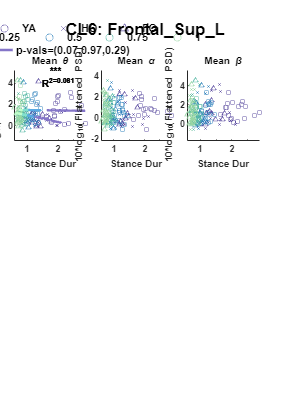

##6-theta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F        pValue 
                                    ____________    ___    ___________    _______    ________

    group_char                        0.57234         2      0.28617      0.32755     0.72116
    mean_GaitCycleDur                  4.0104         1       4.0104       4.5903    0.033646
    group_char:mean_GaitCycleDur        3.518         2        1.759       2.0134     0.13686
    Error                              141.53       162      0.87365                         
    Total                              156.88       167                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                             Estimate       SE         tStat        pValue  
                                            __________    _______    _________    __________

    (Intercept)                                 1.4683    0.32677       4.4933    1.3285e-05
    group_char_H2000's                         0.47619    0.59739      0.79712       0.42655
    group_char_H3000's                          0.2345    0.67949      0.34511       0.73046
    mean_GaitCycleDur                       -0.0042788     0.1667    -0.025668       0.97955
    group_char_H2000's:mean_GaitCycleDur      -0.65295    0.35755      -1.8262      0.069667
    group_char

##6-alpha_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F        pValue 
                                    ____________    ___    ___________    ________    _______

    group_char                          0.2855        2      0.14275       0.13888    0.87043
    mean_GaitCycleDur                 0.095144        1     0.095144      0.092566    0.76133
    group_char:mean_GaitCycleDur       0.55857        2      0.27928       0.27172    0.76242
    Error                               166.51      162       1.0278                         
    Total                               168.94      167                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate       SE        tStat       pValue 
                                            _________    _______    ________    ________

    (Intercept)                               0.71182    0.35444      2.0083    0.046273
    group_char_H2000's                        0.17853    0.64797     0.27552     0.78327
    group_char_H3000's                       -0.26605    0.73701    -0.36098     0.71858
    mean_GaitCycleDur                       0.0059945    0.18081    0.033153     0.97359
    group_char_H2000's:mean_GaitCycleDur     -0.26698    0.38782    -0.68839     0.49219
    group_char_H3000's:mean_GaitCycleDur</

##6-beta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F       pValue 
                                    ____________    ___    ___________    _______    _______

    group_char                        0.96249         2      0.48125      0.36822    0.69254
    mean_GaitCycleDur                 0.36171         1      0.36171      0.27676    0.59955
    group_char:mean_GaitCycleDur      0.38856         2      0.19428      0.14865    0.86199
    Error                              211.73       162        1.307                        
    Total                              214.86       167                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate      SE        tStat       pValue  
                                            ________    _______    ________    _________

    (Intercept)                                1.211    0.39968        3.03    0.0028473
    group_char_H2000's                      -0.60239    0.73067    -0.82444       0.4109
    group_char_H3000's                      0.010739    0.83108    0.012922      0.98971
    mean_GaitCycleDur                       0.056738    0.20389     0.27828      0.78115
    group_char_H2000's:mean_GaitCycleDur     0.22624    0.43732     0.51732      0.60564
    group_char_H3000's:mean_GaitCycleDur

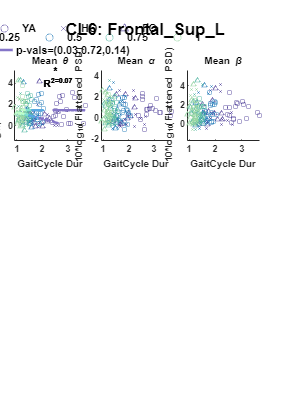

##6-theta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F       pValue 
                                          ____________    ___    ___________    _______    _______

    group_char                               3.9431         2       1.9715       2.2121    0.11276
    mean_PeakUpDownVel_mean                  1.7167         1       1.7167       1.9262    0.16708
    group_char:mean_PeakUpDownVel_mean      0.44683         2      0.22342      0.25068    0.77857
    Error                                    144.38       162      0.89124                        
    Total                                    156.88       167                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat       pValue  
                                                  ________    _______    _______    __________

    (Intercept)                                     1.3743    0.26841     5.1202    8.5686e-07
    group_char_H2000's                            -0.82598    0.41221    -2.0038      0.046761
    group_char_H3000's                            -0.60363    0.43302     -1.394       0.16523
    mean_PeakUpDownVel_mean                        0.37313     1.0587    0.35243       0.72497
    group_char_H2000's:mean_PeakUpDownVel_mean      1.0374     1.4708    0.70535        0.4816
  

##6-alpha_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F       pValue 
                                          ____________    ___    ___________    _______    _______

    group_char                               1.5818         2      0.79088      0.77475    0.46252
    mean_PeakUpDownVel_mean                 0.86855         1      0.86855      0.85084    0.35769
    group_char:mean_PeakUpDownVel_mean      0.72847         2      0.36423      0.35681    0.70046
    Error                                    165.37       162       1.0208                        
    Total                                    168.94       167                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat       pValue 
                                                  ________    _______    ________    ________

    (Intercept)                                    0.64275    0.28726      2.2375    0.026616
    group_char_H2000's                             -0.5384    0.44116     -1.2204     0.22408
    group_char_H3000's                            -0.12435    0.46343    -0.26832     0.78879
    mean_PeakUpDownVel_mean                        0.34734     1.1331     0.30654     0.75959
    group_char_H2000's:mean_PeakUpDownVel_mean      1.0449     1.5741     0.66382     0.50775
    

##6-beta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F        pValue 
                                          ____________    ___    ___________    ________    _______

    group_char                                2.7146        2       1.3573        1.0407    0.35557
    mean_PeakUpDownVel_mean                 0.010558        1     0.010558      0.008095    0.92842
    group_char:mean_PeakUpDownVel_mean        1.2182        2      0.60908         0.467    0.62772
    Error                                     211.29      162       1.3042                         
    Total                                     214.86      167                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat        pValue  
                                                  ________    _______    ________    __________

    (Intercept)                                     1.4797     0.3247      4.5572    1.0161e-05
    group_char_H2000's                            -0.71427    0.49866     -1.4324       0.15396
    group_char_H3000's                            -0.22034    0.52383    -0.42062       0.67459
    mean_PeakUpDownVel_mean                       -0.71066     1.2808    -0.55488       0.57974
    group_char_H2000's:mean_PeakUpDownVel_mean      1.6998     1.7792     0.95536       0.34

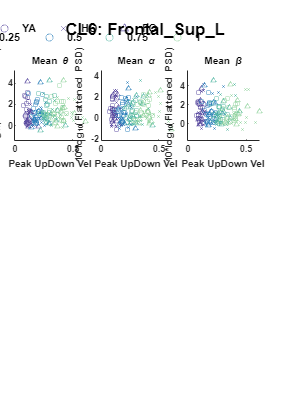

##7-theta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                     0.84533         2      0.42267      0.91637    0.40226
    mean_APexc_COV                 0.15783         1      0.15783      0.34218    0.55947
    group_char:mean_APexc_COV      0.77163         2      0.38581      0.83646     0.4353
    Error                           67.341       146      0.46124                        
    Total                            69.64       151                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                          Estimate        SE        tStat      pValue 
                                         __________    ________    ________    _______

    (Intercept)                             0.43469      0.3857       1.127    0.26159
    group_char_H2000's                      0.20454     0.58668     0.34863    0.72787
    group_char_H3000's                      0.68541      0.5221      1.3128    0.19131
    mean_APexc_COV                        0.0033862    0.023227     0.14579    0.88429
    group_char_H2000's:mean_APexc_COV    -0.0021874    0.030516    -0.07168    0.94295
    group_char_H3000's:mean_APexc_COV     -0.02752

##7-alpha_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares      F        pValue 
                                 ____________    ___    ___________    ______    ________

    group_char                      31.897         2      15.949       4.2116    0.016663
    mean_APexc_COV                  12.378         1      12.378       3.2686    0.072675
    group_char:mean_APexc_COV       17.216         2      8.6078       2.2731     0.10663
    Error                           552.88       146      3.7868                         
    Total                           687.25       151                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue  
                                         _________    ________    ________    _________

    (Intercept)                             1.7238      1.1051      1.5598      0.12097
    group_char_H2000's                      4.8453       1.681      2.8824    0.0045436
    group_char_H3000's                      1.6503       1.496      1.1031      0.27178
    mean_APexc_COV                       -0.012731    0.066553    -0.19129      0.84856
    group_char_H2000's:mean_APexc_COV     -0.13826    0.087439     -1.5812        0.116
    group_char_H3000's:mean_APexc_COV    0.

##7-beta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares      F        pValue  
                                 ____________    ___    ___________    ______    _________

    group_char                      4.5393         2       2.2696      2.5766     0.079486
    mean_APexc_COV                  6.6038         1       6.6038       7.497    0.0069496
    group_char:mean_APexc_COV       5.3132         2       2.6566      3.0159     0.052063
    Error                           128.61       146      0.88086                         
    Total                           138.23       151                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue  
                                         _________    ________    ________    _________

    (Intercept)                             1.5978     0.53301      2.9976    0.0031989
    group_char_H2000's                      1.0567     0.81076      1.3033      0.19453
    group_char_H3000's                    -0.71557     0.72151    -0.99178      0.32295
    mean_APexc_COV                       -0.042647    0.032099     -1.3286      0.18604
    group_char_H2000's:mean_APexc_COV    -0.039492    0.042172    -0.93646      0.35058
    group_char_H3000's:mean_APexc_COV     0.

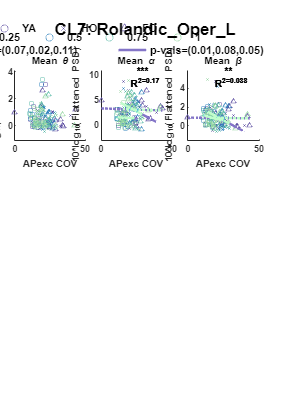

##7-theta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                        1.1231        2      0.56153       1.2044    0.30283
    mean_APexc_mean                 0.091878        1     0.091878      0.19707    0.65776
    group_char:mean_APexc_mean       0.72224        2      0.36112      0.77456    0.46279
    Error                             68.069      146      0.46623                        
    Total                              69.64      151                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat     pValue 
                                          ________    _______    _______    _______

    (Intercept)                           0.28863     0.33638    0.85805    0.39227
    group_char_H2000's                    0.77123     0.50659     1.5224    0.13007
    group_char_H3000's                    0.22751     0.43459     0.5235    0.60142
    mean_APexc_mean                        3.8624      6.2553    0.61747    0.53789
    group_char_H2000's:mean_APexc_mean    -13.359      10.775    -1.2398    0.21702
    group_char_H3000's:mean_APexc_mean    -3.6599      8.5293    -0.42

##7-alpha_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares      F        pValue  
                                  ____________    ___    ___________    ______    _________

    group_char                       35.906         2      17.953       4.8672    0.0089887
    mean_APexc_mean                  19.717         1      19.717       5.3455     0.022175
    group_char:mean_APexc_mean       34.762         2      17.381       4.7121     0.010397
    Error                            538.53       146      3.6886                          
    Total                            687.25       151                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue 
                                          ________    _______    ________    ________

    (Intercept)                            0.80753    0.94615     0.85349     0.39478
    group_char_H2000's                    -0.77456     1.4249    -0.54359     0.58755
    group_char_H3000's                        2.88     1.2224      2.3561    0.019799
    mean_APexc_mean                         13.651     17.595     0.77588     0.43907
    group_char_H2000's:mean_APexc_mean      64.701     30.307      2.1348    0.034444
    group_char_H3000's:mean_APexc_mean     -26.082     2

##7-beta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares      F        pValue  
                                  ____________    ___    ___________    ______    _________

    group_char                       8.5776         2       4.2888      5.0155    0.0078227
    mean_APexc_mean                  7.6556         1       7.6556      8.9528    0.0032537
    group_char:mean_APexc_mean       10.025         2       5.0124      5.8617    0.0035593
    Error                            124.85       146      0.85511                         
    Total                            138.23       151                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat      pValue 
                                          ________    _______    _______    ________

    (Intercept)                           0.44079     0.45556    0.96758     0.33485
    group_char_H2000's                    -1.4268     0.68606    -2.0797    0.039298
    group_char_H3000's                    0.57687     0.58856    0.98014     0.32864
    mean_APexc_mean                        8.9622      8.4715     1.0579     0.29184
    group_char_H2000's:mean_APexc_mean       35.7      14.592     2.4465    0.015613
    group_char_H3000's:mean_APexc_mean    -13.004      11.551   

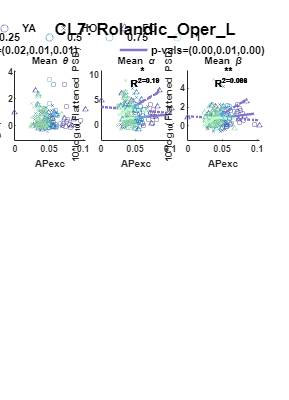

##7-theta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                     0.22198         2      0.11099      0.24146     0.7858
    mean_MLexc_COV                 0.47498         1      0.47498       1.0333    0.31106
    group_char:mean_MLexc_COV      0.59608         2      0.29804      0.64839    0.52439
    Error                           67.111       146      0.45966                        
    Total                            69.64       151                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             0.8396     0.23364      3.5935    0.00044525
    group_char_H2000's                    -0.28228     0.41341    -0.68281       0.49581
    group_char_H3000's                   -0.044903     0.37451     -0.1199       0.90473
    mean_MLexc_COV                       -0.025348    0.015765     -1.6078       0.11004
    group_char_H2000's:mean_MLexc_COV     0.033811    0.029988      1.1275       0.26139
    group_char_H3000's:mean_MLexc_COV

##7-alpha_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      7.1293         2       3.5646      0.90039    0.40866
    mean_MLexc_COV                 0.52698         1      0.52698      0.13311    0.71576
    group_char:mean_MLexc_COV      0.83638         2      0.41819      0.10563    0.89983
    Error                           578.01       146        3.959                        
    Total                           687.25       151                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue  
                                         _________    ________    ________    _________

    (Intercept)                             1.9764     0.68569      2.8823    0.0045444
    group_char_H2000's                      1.3245      1.2133      1.0917      0.27678
    group_char_H3000's                      1.2257      1.0991      1.1152      0.26659
    mean_MLexc_COV                       -0.033217    0.046268    -0.71792      0.47395
    group_char_H2000's:mean_MLexc_COV     0.032249    0.088007     0.36643      0.71457
    group_char_H3000's:mean_MLexc_COV     0

##7-beta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                     0.85217         2      0.42609      0.45527    0.63518
    mean_MLexc_COV                 0.41114         1      0.41114       0.4393    0.50851
    group_char:mean_MLexc_COV      0.71805         2      0.35903      0.38361    0.68208
    Error                           136.64       146      0.93591                        
    Total                           138.23       151                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             1.2767     0.33339      3.8295    0.00019001
    group_char_H2000's                    -0.24559      0.5899    -0.41632       0.67779
    group_char_H3000's                    -0.50781     0.53439    -0.95026       0.34355
    mean_MLexc_COV                       -0.026774    0.022496     -1.1902       0.23592
    group_char_H2000's:mean_MLexc_COV     0.014116     0.04279     0.32988       0.74196
    group_char_H3000's:mean_MLexc_COV

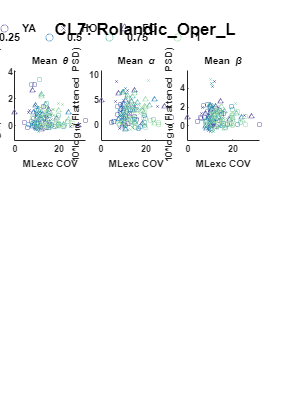

##7-theta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                       1.2228         2      0.61142        1.315    0.27164
    mean_MLexc_mean                    0.15         1         0.15      0.32261    0.57091
    group_char:mean_MLexc_mean      0.70775         2      0.35388      0.76108      0.469
    Error                            67.885       146      0.46496                        
    Total                             69.64       151                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE         tStat      pValue 
                                          ________    _______    _________    _______

    (Intercept)                            0.29273    0.25197       1.1617    0.24723
    group_char_H2000's                     0.54568    0.37495       1.4554    0.14772
    group_char_H3000's                    0.018577    0.36069     0.051505    0.95899
    mean_MLexc_mean                         2.4838     2.9925      0.83001    0.40789
    group_char_H2000's:mean_MLexc_mean     -4.4644     4.2025      -1.0623    0.28984
    group_char_H3000's:mean_MLexc_mean    -0.20156     3

##7-alpha_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares        F          pValue 
                                  ____________    ___    ___________    __________    ________

    group_char                         19.088       2         9.544         2.4094    0.093435
    mean_MLexc_mean                0.00023394       1    0.00023394     5.9058e-05     0.99388
    group_char:mean_MLexc_mean          1.719       2       0.85948        0.21698     0.80521
    Error                              578.33     146        3.9611                           
    Total                              687.25     151                                         



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate       SE         tStat        pValue 
                                          _________    _______    __________    ________

    (Intercept)                              1.3463    0.73545        1.8306    0.069202
    group_char_H2000's                       1.7565     1.0944         1.605     0.11066
    group_char_H3000's                       2.1853     1.0528        2.0758    0.039666
    mean_MLexc_mean                           2.162     8.7345       0.24753     0.80485
    group_char_H2000's:mean_MLexc_mean    -0.037511     12.266    -0.0030581     0.99756
    group_char_H3000's:mean_MLexc_mean

##7-beta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    ________    _______

    group_char                        1.1809        2      0.59047        0.6321    0.53292
    mean_MLexc_mean                 0.076549        1     0.076549      0.081946    0.77508
    group_char:mean_MLexc_mean        1.7208        2      0.86041       0.92107    0.40039
    Error                             136.38      146      0.93414                         
    Total                             138.23      151                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat     pValue 
                                          ________    _______    _______    _______

    (Intercept)                           0.60776     0.35715     1.7017    0.09094
    group_char_H2000's                    0.11996     0.53146    0.22571    0.82174
    group_char_H3000's                    0.55138     0.51124     1.0785    0.28258
    mean_MLexc_mean                        3.7761      4.2416    0.89024     0.3748
    group_char_H2000's:mean_MLexc_mean    -2.1522      5.9567    -0.3613     0.7184
    group_char_H3000's:mean_MLexc_mean    -7.1862      5.5521    -1.294

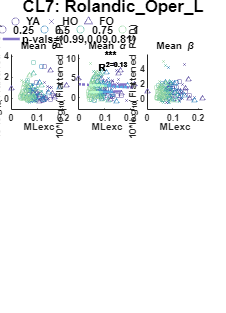

##7-theta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F       pValue 
                               ____________    ___    ___________    _______    _______

    group_char                   0.97025         2      0.48512       1.0417    0.35545
    mean_StepDur                  0.1879         1       0.1879       0.4035    0.52628
    group_char:mean_StepDur      0.76862         2      0.38431      0.82525    0.44016
    Error                          67.99       146      0.46569                        
    Total                          69.64       151                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate      SE        tStat       pValue 
                                       ________    _______    ________    ________

    (Intercept)                         0.46896    0.26231      1.7878    0.075876
    group_char_H2000's                  0.38572     0.4739     0.81392     0.41701
    group_char_H3000's                 -0.49546    0.53485    -0.92635     0.35579
    mean_StepDur                       0.022903    0.27612    0.082945     0.93401
    group_char_H2000's:mean_StepDur    -0.27768     0.5822    -0.47696      0.6341
    group_char_H3000's:mean_StepDur     0.76173    0.70321      1.0832      0.28

##7-alpha_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F       pValue 
                               ____________    ___    ___________    _______    _______

    group_char                     4.649         2      2.3245       0.60007    0.55012
    mean_StepDur                  8.8938         1      8.8938        2.2959    0.13188
    group_char:mean_StepDur       5.9906         2      2.9953       0.77324     0.4634
    Error                         565.57       146      3.8737                         
    Total                         687.25       151                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate      SE        tStat      pValue 
                                       ________    _______    ________    _______

    (Intercept)                          1.0151    0.75653      1.3417    0.18177
    group_char_H2000's                  0.32553     1.3668     0.23817    0.81208
    group_char_H3000's                   1.6873     1.5426      1.0938    0.27584
    mean_StepDur                        0.55942    0.79637     0.70246    0.48351
    group_char_H2000's:mean_StepDur      2.0608     1.6791      1.2273    0.22169
    group_char_H3000's:mean_StepDur    0.063791     2.0282    0.031452    0.97495


Num

##7-beta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F       pValue 
                               ____________    ___    ___________    _______    _______

    group_char                   0.49285         2      0.24642      0.26567    0.76706
    mean_StepDur                  1.9716         1       1.9716       2.1256      0.147
    group_char:mean_StepDur      0.61878         2      0.30939      0.33356    0.71691
    Error                         135.42       146      0.92754                        
    Total                         138.23       151                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate       SE        tStat      pValue 
                                       _________    _______    ________    _______

    (Intercept)                          0.60806    0.37019      1.6425    0.10263
    group_char_H2000's                  -0.48431    0.66881    -0.72413    0.47014
    group_char_H3000's                 -0.087703    0.75484    -0.11619    0.90766
    mean_StepDur                         0.33273    0.38969     0.85383     0.3946
    group_char_H2000's:mean_StepDur      0.67066    0.82166     0.81622     0.4157
    group_char_H3000's:mean_StepDur      0.12165    0.99245     0.12258    0.9026

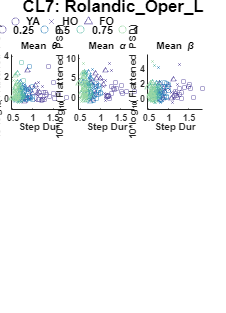

##7-theta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                     0.85894         2      0.42947      0.92044    0.40064
    mean_UDexc_COV                 0.30915         1      0.30915      0.66257    0.41698
    group_char:mean_UDexc_COV      0.46541         2      0.23271      0.49874    0.60833
    Error                           68.122       146      0.46659                        
    Total                            69.64       151                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue 
                                         _________    ________    ________    ________

    (Intercept)                            0.42118     0.21919      1.9215    0.056614
    group_char_H2000's                      0.4537      0.3488      1.3007      0.1954
    group_char_H3000's                     0.30286     0.34886     0.86817     0.38673
    mean_UDexc_COV                       0.0056184    0.016593      0.3386      0.7354
    group_char_H2000's:mean_UDexc_COV    -0.021519    0.025257      -0.852     0.39561
    group_char_H3000's:mean_UDexc_COV    -0.021724

##7-alpha_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                       37.09         2      18.545        4.7673    0.009872
    mean_UDexc_COV                  5.5921         1      5.5921        1.4375     0.23248
    group_char:mean_UDexc_COV       7.2276         2      3.6138       0.92896     0.39728
    Error                           567.96       146      3.8901                          
    Total                           687.25       151                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                          Estimate         SE          tStat        pValue  
                                         ___________    ________    ___________    _________

    (Intercept)                               1.5177      0.6329         2.3981     0.017745
    group_char_H2000's                        3.0341      1.0071         3.0126    0.0030544
    group_char_H3000's                        1.8251      1.0073         1.8119     0.072058
    mean_UDexc_COV                       -1.1206e-05    0.047911    -0.00023389      0.99981
    group_char_H2000's:mean_UDexc_COV      -0.095826     0.07293        -1.3139      0.19092
    group_char_H3

##7-beta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      2.8563         2       1.4281       1.5543    0.21482
    mean_UDexc_COV                 0.76033         1      0.76033      0.82748     0.3645
    group_char:mean_UDexc_COV       3.1872         2       1.5936       1.7343    0.18013
    Error                           134.15       146      0.91885                        
    Total                           138.23       151                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                          Estimate        SE         tStat       pValue  
                                         __________    ________    _________    _________

    (Intercept)                             0.93168     0.30759       3.0289    0.0029032
    group_char_H2000's                       0.6466     0.48948        1.321      0.18857
    group_char_H3000's                     -0.26987     0.48956     -0.55125      0.58231
    mean_UDexc_COV                       -0.0020317    0.023285    -0.087253      0.93059
    group_char_H2000's:mean_UDexc_COV     -0.051722    0.035444      -1.4593      0.14664
    group_char_H3000's:mean_UDexc_COV</

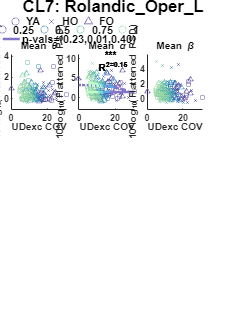

##7-theta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                      0.47507         2      0.23754      0.50947    0.60188
    mean_UDexc_mean                 0.14985         1      0.14985      0.32139    0.57164
    group_char:mean_UDexc_mean      0.62387         2      0.31194      0.66904    0.51376
    Error                            68.071       146      0.46624                        
    Total                             69.64       151                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE         tStat      pValue 
                                          ________    _______    _________    _______

    (Intercept)                            0.3033     0.25933       1.1696    0.24408
    group_char_H2000's                    0.16882     0.37749      0.44722    0.65538
    group_char_H3000's                    0.38713     0.38362       1.0091    0.31458
    mean_UDexc_mean                        8.3028      10.918       0.7605    0.44818
    group_char_H2000's:mean_UDexc_mean    -0.4495      15.036    -0.029895    0.97619
    group_char_H3000's:mean_UDexc_mean    -14.342      1

##7-alpha_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    _______    ________

    group_char                       35.729         2      17.865        4.6713    0.010803
    mean_UDexc_mean                  1.9983         1      1.9983       0.52253     0.47092
    group_char:mean_UDexc_mean       18.607         2      9.3033        2.4326    0.091356
    Error                            558.35       146      3.8243                          
    Total                            687.25       151                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                            1.4938     0.74272      2.0112     0.046141
    group_char_H2000's                       1.21      1.0811      1.1192      0.26488
    group_char_H3000's                     3.3386      1.0987      3.0387    0.0028158
    mean_UDexc_mean                         1.062      31.268    0.033963      0.97295
    group_char_H2000's:mean_UDexc_mean     22.711      43.062      0.5274      0.59871
    group_char_H3000's:mean_UDexc_mean    -62.844

##7-beta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                        3.3496        2       1.6748       1.8259    0.16474
    mean_UDexc_mean                 0.099101        1     0.099101      0.10804    0.74286
    group_char:mean_UDexc_mean        4.0064        2       2.0032       2.1839    0.11627
    Error                             133.92      146      0.91728                        
    Total                             138.23      151                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                             1.0028    0.36375      2.7569    0.0065795
    group_char_H2000's                    -0.59332    0.52948     -1.1206      0.26431
    group_char_H3000's                     0.45761    0.53808     0.85045      0.39647
    mean_UDexc_mean                        -4.2741     15.313    -0.27911      0.78056
    group_char_H2000's:mean_UDexc_mean      22.985      21.09      1.0899      0.27757
    group_char_H3000's:mean_UDexc_mean      -18.39

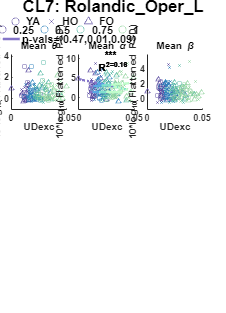

##7-theta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                     0.65695         2      0.32848       0.7021    0.49721
    mean_StanceDur                 0.16119         1      0.16119      0.34453    0.55813
    group_char:mean_StanceDur      0.37116         2      0.18558      0.39667    0.67328
    Error                           68.306       146      0.46785                        
    Total                            69.64       151                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate      SE        tStat       pValue 
                                         ________    _______    ________    ________

    (Intercept)                           0.40761    0.21999      1.8529    0.065919
    group_char_H2000's                    0.35758    0.39083     0.91494     0.36173
    group_char_H3000's                     -0.203    0.43788    -0.46359     0.64363
    mean_StanceDur                        0.06719    0.16623      0.4042     0.68666
    group_char_H2000's:mean_StanceDur    -0.16701    0.34809     -0.4798     0.63209
    group_char_H3000's:mean_StanceDur     0.26876    0.41653    

##7-alpha_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                       6.779         2      3.3895       0.87347    0.41967
    mean_StanceDur                  9.7196         1      9.7196        2.5047    0.11567
    group_char:mean_StanceDur       3.9159         2       1.958       0.50456    0.60482
    Error                           566.56       146      3.8805                         
    Total                           687.25       151                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate      SE        tStat     pValue 
                                         ________    _______    _______    _______

    (Intercept)                           1.0318     0.63357     1.6286    0.10555
    group_char_H2000's                   0.85179      1.1256    0.75676    0.45042
    group_char_H3000's                    1.5807      1.2611     1.2534    0.21206
    mean_StanceDur                       0.39839     0.47875    0.83215    0.40668
    group_char_H2000's:mean_StanceDur     1.0051      1.0025     1.0026    0.31772
    group_char_H3000's:mean_StanceDur    0.15511      1.1996     0.1293     0.

##7-beta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    group_char                     0.087833        2     0.043916       0.04716    0.95395
    mean_StanceDur                   1.6573        1       1.6573        1.7797    0.18427
    group_char:mean_StanceDur       0.13169        2     0.065846      0.070709    0.93177
    Error                            135.96      146      0.93122                         
    Total                            138.23      151                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate       SE        tStat       pValue 
                                         _________    _______    ________    ________

    (Intercept)                            0.61752    0.31036      1.9897    0.048495
    group_char_H2000's                    -0.16761    0.55139    -0.30398     0.76158
    group_char_H3000's                   -0.079057    0.61778    -0.12797     0.89835
    mean_StanceDur                         0.23737    0.23452      1.0121     0.31315
    group_char_H2000's:mean_StanceDur      0.18197    0.49109     0.37055     0.71151
    group_char_H3000's:mean_StanceDur       0.0785    0.58

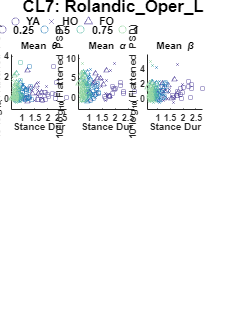

##7-theta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F       pValue 
                                    ____________    ___    ___________    _______    _______

    group_char                        0.96303         2      0.48151       1.0339    0.35821
    mean_GaitCycleDur                 0.18601         1      0.18601      0.39938     0.5284
    group_char:mean_GaitCycleDur      0.76083         2      0.38041       0.8168    0.44385
    Error                              67.997       146      0.46574                        
    Total                               69.64       151                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate      SE        tStat       pValue 
                                            ________    _______    ________    ________

    (Intercept)                              0.46823    0.26214      1.7861    0.076151
    group_char_H2000's                       0.38558    0.47346     0.81439     0.41675
    group_char_H3000's                      -0.49073    0.53393    -0.91911     0.35956
    mean_GaitCycleDur                       0.011853    0.13788    0.085967     0.93161
    group_char_H2000's:mean_GaitCycleDur    -0.13861    0.29068    -0.47687     0.63417
    group_char_H3000's:mean_GaitCycleDur

##7-alpha_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F       pValue 
                                    ____________    ___    ___________    _______    _______

    group_char                          4.814         2       2.407       0.62139    0.53861
    mean_GaitCycleDur                  8.7724         1      8.7724        2.2647    0.13451
    group_char:mean_GaitCycleDur       6.0634         2      3.0317       0.78267    0.45909
    Error                              565.54       146      3.8736                         
    Total                              687.25       151                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate      SE        tStat      pValue 
                                            ________    _______    ________    _______

    (Intercept)                               1.0152    0.75601      1.3429     0.1814
    group_char_H2000's                       0.32202     1.3654     0.23584    0.81389
    group_char_H3000's                        1.7133     1.5398      1.1126    0.26769
    mean_GaitCycleDur                        0.27947    0.39765     0.70281     0.4833
    group_char_H2000's:mean_GaitCycleDur      1.0324    0.83829      1.2316    0.22008
    group_char_H3000's:mean_GaitCycleDur    0.0

##7-beta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F       pValue 
                                    ____________    ___    ___________    _______    _______

    group_char                        0.50946         2      0.25473      0.27466    0.76022
    mean_GaitCycleDur                  1.9643         1       1.9643        2.118    0.14772
    group_char:mean_GaitCycleDur      0.63727         2      0.31864      0.34357    0.70981
    Error                               135.4       146      0.92743                        
    Total                              138.23       151                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate       SE        tStat      pValue 
                                            _________    _______    ________    _______

    (Intercept)                               0.60892    0.36992      1.6461     0.1019
    group_char_H2000's                       -0.49083    0.66812    -0.73465    0.46373
    group_char_H3000's                      -0.079363    0.75344    -0.10533    0.91626
    mean_GaitCycleDur                         0.16579    0.19457     0.85205    0.39558
    group_char_H2000's:mean_GaitCycleDur      0.33953    0.41018     0.82774    0.40917
    group_char_H3000's:mean_GaitCycleDur 

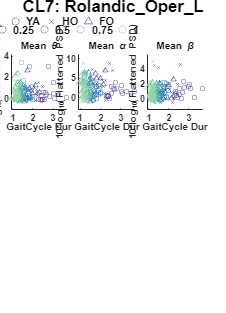

##7-theta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F        pValue 
                                          ____________    ___    ___________    ________    _______

    group_char                              0.55484         2      0.27742       0.59614    0.55227
    mean_PeakUpDownVel_mean                 0.04277         1      0.04277      0.091908     0.7622
    group_char:mean_PeakUpDownVel_mean      0.81981         2      0.40991       0.88084    0.41663
    Error                                    67.942       146      0.46536                         
    Total                                     69.64       151                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat      pValue 
                                                  ________    _______    _______    ________

    (Intercept)                                   0.38058     0.20279     1.8767    0.062556
    group_char_H2000's                            0.11724     0.30791    0.38076     0.70393
    group_char_H3000's                            0.34229     0.31454     1.0882     0.27829
    mean_PeakUpDownVel_mean                       0.47161     0.79641    0.59216     0.55466
    group_char_H2000's:mean_PeakUpDownVel_mean    0.16438      1.1208    0.14667      0.8836
    grou

##7-alpha_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares      F        pValue 
                                          ____________    ___    ___________    ______    ________

    group_char                               46.815         2      23.407       6.1267    0.002786
    mean_PeakUpDownVel_mean                  7.3707         1      7.3707       1.9292     0.16696
    group_char:mean_PeakUpDownVel_mean         14.2         2      7.1001       1.8584     0.15959
    Error                                     557.8       146      3.8206                         
    Total                                    687.25       151                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate       SE         tStat        pValue  
                                                  _________    _______    _________    __________

    (Intercept)                                      1.5343    0.58106       2.6405     0.0091796
    group_char_H2000's                               1.7637    0.88225       1.9991       0.04745
    group_char_H3000's                               3.1098    0.90126       3.4504    0.00073202
    mean_PeakUpDownVel_mean                       -0.072172      2.282    -0.031627       0.97481
    group_char_H2000's:mean_PeakUpDownVel_mean     0.035958     3.2113     0.01

##7-beta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F       pValue 
                                          ____________    ___    ___________    _______    _______

    group_char                               1.2994         2      0.64968      0.69833    0.49907
    mean_PeakUpDownVel_mean                 0.47741         1      0.47741      0.51317    0.47491
    group_char:mean_PeakUpDownVel_mean       1.7525         2      0.87627       0.9419    0.39224
    Error                                    135.83       146      0.93032                        
    Total                                    138.23       151                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat       pValue  
                                                  ________    _______    ________    _________

    (Intercept)                                    0.96158    0.28673      3.3536    0.0010163
    group_char_H2000's                            -0.21743    0.43536    -0.49944      0.61822
    group_char_H3000's                             0.33696    0.44474     0.75766      0.44988
    mean_PeakUpDownVel_mean                       -0.23644     1.1261    -0.20997      0.83398
    group_char_H2000's:mean_PeakUpDownVel_mean     0.71319     1.5847     0.45006      0.65334
   

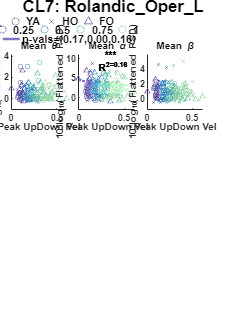

##8-theta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                     0.77037         2      0.38519      0.34166    0.71123
    mean_APexc_COV                  1.3073         1       1.3073       1.1596    0.28355
    group_char:mean_APexc_COV      0.28097         2      0.14048      0.12461    0.88295
    Error                           146.56       130       1.1274                        
    Total                           160.97       135                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue 
                                         _________    ________    ________    ________

    (Intercept)                             1.1674     0.51124      2.2834    0.024032
    group_char_H2000's                    -0.67917     0.97555     -0.6962     0.48755
    group_char_H3000's                     0.14082     0.78183     0.18011     0.85734
    mean_APexc_COV                       -0.030732    0.031366    -0.97978     0.32901
    group_char_H2000's:mean_APexc_COV     0.014864    0.050058     0.29693       0.767
    group_char_H3000's:mean_APexc_COV      0.01881

##8-alpha_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                      24.014         2       12.007       2.0458     0.13342
    mean_APexc_COV                  33.246         1       33.246       5.6647    0.018763
    group_char:mean_APexc_COV       1.9887         2      0.99433      0.16942     0.84434
    Error                           762.97       130        5.869                         
    Total                           897.85       135                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             4.3996      1.1665      3.7717    0.00024518
    group_char_H2000's                    0.098219      2.2258    0.044127       0.96487
    group_char_H3000's                       3.416      1.7838       1.915      0.057694
    mean_APexc_COV                       -0.073377    0.071566     -1.0253       0.30712
    group_char_H2000's:mean_APexc_COV    -0.025342     0.11421    -0.22188       0.82475
    group_char_H3000's:mean_APexc_COV

##8-beta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                     0.35558         2      0.17779      0.14193    0.86782
    mean_APexc_COV                  2.0045         1       2.0045       1.6002    0.20814
    group_char:mean_APexc_COV       1.7316         2      0.86578      0.69116    0.50282
    Error                           162.84       130       1.2526                        
    Total                           169.67       135                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                          Estimate        SE        tStat        pValue  
                                         __________    ________    ________    __________

    (Intercept)                                1.98     0.53889      3.6742    0.00034755
    group_char_H2000's                     0.029771      1.0283    0.028951       0.97695
    group_char_H3000's                      -0.4037     0.82411    -0.48987       0.62506
    mean_APexc_COV                        -0.035182    0.033062     -1.0641       0.28926
    group_char_H2000's:mean_APexc_COV    -0.0049262    0.052765    -0.09336       0.92576
    group_char_H3000's:mean_APexc_COV</

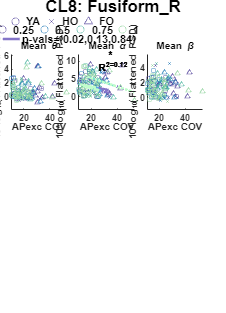

##8-theta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    ________    _______

    group_char                        3.4859        2       1.7429        1.5375    0.21881
    mean_APexc_mean                 0.064619        1     0.064619      0.057001    0.81168
    group_char:mean_APexc_mean       0.81471        2      0.40736       0.35933    0.69883
    Error                             147.37      130       1.1336                         
    Total                             160.97      135                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat      pValue 
                                          ________    _______    ________    _______

    (Intercept)                            0.47941     0.4943     0.96986    0.33392
    group_char_H2000's                    -0.58727    0.86133    -0.68182    0.49657
    group_char_H3000's                     0.74301    0.64532      1.1514    0.25169
    mean_APexc_mean                         3.7353     8.6354     0.43256    0.66605
    group_char_H2000's:mean_APexc_mean      2.6527     18.423     0.14398    0.88574
    group_char_H3000's:mean_APexc_mean     -9.0067     12.171  

##8-alpha_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares      F        pValue 
                                  ____________    ___    ___________    ______    ________

    group_char                       14.371         2      7.1853       1.2146     0.30019
    mean_APexc_mean                  21.695         1      21.695       3.6671    0.057692
    group_char:mean_APexc_mean       24.513         2      12.256       2.0717     0.13011
    Error                            769.08       130       5.916                         
    Total                            897.85       135                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE       tStat       pValue  
                                          ________    ______    ________    _________

    (Intercept)                            3.5604     1.1292      3.1531    0.0020066
    group_char_H2000's                    -3.0529     1.9676     -1.5515       0.1232
    group_char_H3000's                    -1.2011     1.4742    -0.81477      0.41669
    mean_APexc_mean                       -5.6936     19.727    -0.28862      0.77333
    group_char_H2000's:mean_APexc_mean     52.189     42.087        1.24       0.2172
    group_char_H3000's:mean_APexc_mean     53.794     27

##8-beta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                       1.7413         2      0.87067      0.71328    0.49194
    mean_APexc_mean                 0.86665         1      0.86665      0.70999      0.401
    group_char:mean_APexc_mean       4.2968         2       2.1484         1.76    0.17612
    Error                            158.69       130       1.2207                        
    Total                            169.67       135                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE         tStat       pValue  
                                          ________    _______    _________    _________

    (Intercept)                             1.4985    0.51292       2.9215    0.0041085
    group_char_H2000's                    -0.24283    0.89377     -0.27169      0.78629
    group_char_H3000's                    -0.77952    0.66963      -1.1641      0.24651
    mean_APexc_mean                        -1.2905     8.9607     -0.14401      0.88571
    group_char_H2000's:mean_APexc_mean    -0.57725     19.117    -0.030195      0.97596
    group_char_H3000's:mean_APexc_mean     

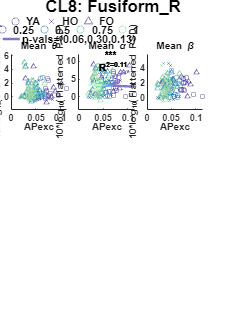

##8-theta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      4.5806         2       2.2903       2.0544    0.13232
    mean_MLexc_COV                  1.4175         1       1.4175       1.2714    0.26157
    group_char:mean_MLexc_COV       1.1537         2      0.57687      0.51745    0.59726
    Error                           144.93       130       1.1148                        
    Total                           160.97       135                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue 
                                         _________    ________    ________    ________

    (Intercept)                             1.0544     0.42003      2.5103    0.013289
    group_char_H2000's                    -0.97989     0.73936     -1.3253     0.18739
    group_char_H3000's                     0.65303     0.67554     0.96669     0.33549
    mean_MLexc_COV                       -0.025665    0.027586    -0.93035     0.35391
    group_char_H2000's:mean_MLexc_COV     0.031765    0.050117     0.63382     0.52731
    group_char_H3000's:mean_MLexc_COV    -0.023217

##8-alpha_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                      28.426         2      14.213        2.4444    0.090758
    mean_MLexc_COV                  36.735         1      36.735        6.3177    0.013175
    group_char:mean_MLexc_COV       7.5655         2      3.7827       0.65057     0.52344
    Error                           755.89       130      5.8145                          
    Total                           897.85       135                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate       SE        tStat        pValue  
                                         _________    _______    ________    __________

    (Intercept)                              5.328    0.95926      5.5543    1.5092e-07
    group_char_H2000's                     -2.3987     1.6885     -1.4206       0.15783
    group_char_H3000's                      1.6712     1.5428      1.0833       0.28069
    mean_MLexc_COV                        -0.14446      0.063     -2.2931      0.023449
    group_char_H2000's:mean_MLexc_COV      0.10982    0.11446     0.95949        0.3391
    group_char_H3000's:mean_MLexc_COV    -0

##8-beta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      3.7282         2       1.8641       1.5308    0.22023
    mean_MLexc_COV                  3.0292         1       3.0292       2.4876    0.11717
    group_char:mean_MLexc_COV       1.9834         2      0.99172      0.81441    0.44515
    Error                            158.3       130       1.2177                        
    Total                           169.67       135                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                          Estimate        SE        tStat        pValue  
                                         __________    ________    ________    __________

    (Intercept)                              2.2141     0.43899      5.0438    1.5014e-06
    group_char_H2000's                      -1.1529     0.77272      -1.492       0.13811
    group_char_H3000's                      0.23163     0.70601     0.32808       0.74338
    mean_MLexc_COV                        -0.054615    0.028831     -1.8943      0.060402
    group_char_H2000's:mean_MLexc_COV      0.063029    0.052378      1.2033       0.23103
    group_char_H3000's:mean_MLexc_COV</

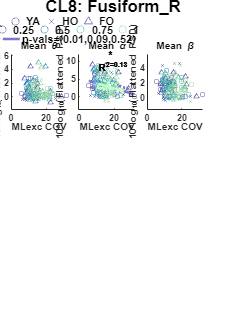

##8-theta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares      F       pValue 
                                  ____________    ___    ___________    ______    _______

    group_char                      0.36329         2      0.18164        0.17    0.84385
    mean_MLexc_mean                  2.7708         1       2.7708      2.5931    0.10975
    group_char:mean_MLexc_mean       3.3729         2       1.6864      1.5783    0.21025
    Error                            138.91       130       1.0685                       
    Total                            160.97       135                                    



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat      pValue 
                                          ________    _______    ________    _______

    (Intercept)                            0.24032    0.40963     0.58667    0.55844
    group_char_H2000's                    0.090777    0.65872     0.13781     0.8906
    group_char_H3000's                    -0.25734    0.57561    -0.44708    0.65556
    mean_MLexc_mean                         5.6883     4.9565      1.1476    0.25322
    group_char_H2000's:mean_MLexc_mean     -7.8714     7.8741    -0.99965    0.31934
    group_char_H3000's:mean_MLexc_mean      5.0105     6.3535  

##8-alpha_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue  
                                  ____________    ___    ___________    _______    _________

    group_char                       9.1172         2      4.5586       0.81972      0.44282
    mean_MLexc_mean                  39.997         1      39.997        7.1923    0.0082721
    group_char:mean_MLexc_mean       26.204         2      13.102         2.356     0.098839
    Error                            722.95       130      5.5611                           
    Total                            897.85       135                                       



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                            2.7779     0.93452      2.9725    0.0035207
    group_char_H2000's                    -1.3045      1.5028    -0.86806      0.38696
    group_char_H3000's                    -1.6128      1.3132     -1.2282      0.22159
    mean_MLexc_mean                        6.0088      11.307      0.5314      0.59605
    group_char_H2000's:mean_MLexc_mean     6.3744      17.964     0.35485      0.72328
    group_char_H3000's:mean_MLexc_mean     29.566

##8-beta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                      0.90279         2      0.45139      0.36912    0.69207
    mean_MLexc_mean                  1.7029         1       1.7029       1.3925    0.24014
    group_char:mean_MLexc_mean       2.6652         2       1.3326       1.0897    0.33937
    Error                            158.98       130       1.2229                        
    Total                            169.67       135                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                             1.2063    0.43823      2.7527    0.0067558
    group_char_H2000's                    0.065923    0.70471    0.093546      0.92561
    group_char_H3000's                    -0.44614    0.61579    -0.72451      0.47006
    mean_MLexc_mean                         2.8313     5.3025     0.53396      0.59428
    group_char_H2000's:mean_MLexc_mean     -4.0309     8.4238    -0.47851      0.63309
    group_char_H3000's:mean_MLexc_mean      6.6722

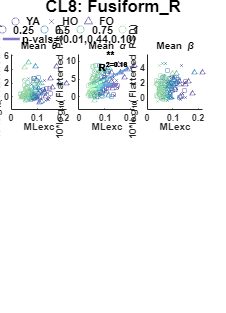

##8-theta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F        pValue 
                               ____________    ___    ___________    ________    _______

    group_char                     1.0607        2      0.53036       0.46597    0.62857
    mean_StepDur                 0.063987        1     0.063987      0.056218    0.81295
    group_char:mean_StepDur      0.034854        2     0.017427      0.015311    0.98481
    Error                          147.97      130       1.1382                         
    Total                          160.97      135                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate       SE         tStat      pValue 
                                       _________    _______    _________    _______

    (Intercept)                           0.5245    0.40808       1.2853    0.20098
    group_char_H2000's                  -0.47112    0.83335     -0.56533    0.57282
    group_char_H3000's                   0.45946    0.75834      0.60588    0.54565
    mean_StepDur                         0.17227    0.41285      0.41727    0.67717
    group_char_H2000's:mean_StepDur    -0.028832     1.0388    -0.027756     0.9779
    group_char_H3000's:mean_StepDur     -0.16759    0.95775     -0.17498 

##8-alpha_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares      F        pValue 
                               ____________    ___    ___________    ______    ________

    group_char                     13.51         2       6.755       1.1458     0.32116
    mean_StepDur                  32.265         1      32.265       5.4727    0.020839
    group_char:mean_StepDur       33.704         2      16.852       2.8585    0.060969
    Error                         766.42       130      5.8955                         
    Total                         897.85       135                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate      SE        tStat       pValue  
                                       ________    _______    ________    _________

    (Intercept)                         3.0468     0.92875      3.2805    0.0013302
    group_char_H2000's                 -1.7482      1.8966    -0.92176      0.35836
    group_char_H3000's                 -2.4184      1.7259     -1.4013      0.16352
    mean_StepDur                       0.21557      0.9396     0.22943       0.8189
    group_char_H2000's:mean_StepDur     1.3482      2.3642     0.57027      0.56948
    group_char_H3000's:mean_StepDur     5.1995      2.1797      2.3854   

##8-beta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares      F       pValue 
                               ____________    ___    ___________    ______    _______

    group_char                    1.5119         2      0.75596      0.6119    0.54387
    mean_StepDur                  3.3064         1       3.3064      2.6763    0.10427
    group_char:mean_StepDur       3.0137         2       1.5068      1.2197    0.29868
    Error                         160.61       130       1.2354                       
    Total                         169.67       135                                    



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate      SE        tStat      pValue  
                                       ________    _______    _______    _________

    (Intercept)                          1.2838    0.42516     3.0197    0.0030468
    group_char_H2000's                  -0.4269    0.86821    -0.4917      0.62376
    group_char_H3000's                 -0.85763    0.79006    -1.0855       0.2797
    mean_StepDur                        0.15447    0.43012    0.35914      0.72007
    group_char_H2000's:mean_StepDur     0.28125     1.0823    0.25987      0.79537
    group_char_H3000's:mean_StepDur      1.5584    0.99782     1.5618      0.1207

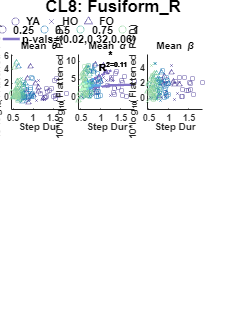

##8-theta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      3.0064         2       1.5032       1.3359     0.2665
    mean_UDexc_COV                  0.7146         1       0.7146      0.63509    0.42695
    group_char:mean_UDexc_COV       1.5323         2      0.76617      0.68092    0.50795
    Error                           146.28       130       1.1252                        
    Total                           160.97       135                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                         Estimate       SE         tStat      pValue 
                                         _________    _______    _________    _______

    (Intercept)                            0.53329     0.3513       1.5181    0.13143
    group_char_H2000's                    -0.02234    0.66029    -0.033834    0.97306
    group_char_H3000's                     0.90709    0.58935       1.5391     0.1262
    mean_UDexc_COV                         0.01278    0.02729      0.46831    0.64035
    group_char_H2000's:mean_UDexc_COV    -0.039727    0.04869     -0.81593    0.41603
    group_char_H3000's:mean_UDexc_COV    -0.044829    0.0

##8-alpha_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      7.1183         2       3.5592      0.57577     0.5637
    mean_UDexc_COV                  7.4124         1       7.4124       1.1991    0.27552
    group_char:mean_UDexc_COV       1.5139         2      0.75693      0.12245    0.88485
    Error                            803.6       130       6.1815                        
    Total                           897.85       135                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                         Estimate       SE        tStat       pValue  
                                         ________    ________    _______    __________

    (Intercept)                            4.1391     0.82339     5.0269    1.6165e-06
    group_char_H2000's                    -1.0874      1.5476    -0.7026       0.48356
    group_char_H3000's                     0.7548      1.3814    0.54642       0.58571
    mean_UDexc_COV                       -0.07522    0.063963     -1.176       0.24175
    group_char_H2000's:mean_UDexc_COV    0.029131     0.11412    0.25526       0.79892
    group_char_H3000's:mean_UDexc_COV     0.04768 

##8-beta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    group_char                      0.78778        2      0.39389       0.31325    0.73162
    mean_UDexc_COV                 0.052675        1     0.052675      0.041891    0.83815
    group_char:mean_UDexc_COV        1.9552        2       0.9776       0.77746     0.4617
    Error                            163.47      130       1.2574                         
    Total                            169.67      135                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             1.6008     0.37137      4.3106    3.1885e-05
    group_char_H2000's                    -0.28579     0.69801    -0.40943       0.68289
    group_char_H3000's                    -0.48114     0.62301    -0.77228       0.44135
    mean_UDexc_COV                       -0.014615    0.028849     -0.5066       0.61329
    group_char_H2000's:mean_UDexc_COV    0.0040989    0.051472    0.079635       0.93665
    group_char_H3000's:mean_UDexc_COV

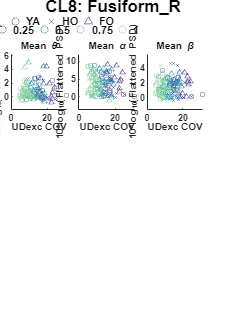

##8-theta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares        F        pValue 
                                  ____________    ___    ___________    _________    _______

    group_char                        4.8406        2        2.4203        2.1383    0.12198
    mean_UDexc_mean                0.0063343        1     0.0063343     0.0055962    0.94048
    group_char:mean_UDexc_mean        1.0429        2       0.52146        0.4607    0.63187
    Error                             147.15      130        1.1319                         
    Total                             160.97      135                                       



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE         tStat       pValue 
                                          ________    _______    _________    ________

    (Intercept)                             0.6961    0.41827       1.6642    0.098475
    group_char_H2000's                    -0.89029    0.66459      -1.3396     0.18271
    group_char_H3000's                     0.58119    0.64857      0.89611     0.37185
    mean_UDexc_mean                        -0.4825     16.851    -0.028633      0.9772
    group_char_H2000's:mean_UDexc_mean       15.22     26.209      0.58073     0.56242
    group_char_H3000's:mean_UDexc_mean     -11.34

##8-alpha_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares      F       pValue 
                                  ____________    ___    ___________    ______    _______

    group_char                       27.173         2      13.587       2.1859     0.1165
    mean_UDexc_mean                  1.3805         1      1.3805       0.2221    0.63823
    group_char:mean_UDexc_mean       5.0086         2      2.5043       0.4029    0.66921
    Error                            808.04       130      6.2157                        
    Total                            897.85       135                                    



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                            3.3618     0.98017      3.4298    0.00080991
    group_char_H2000's                    -1.2159      1.5574    -0.78073       0.43638
    group_char_H3000's                     2.2126      1.5198      1.4558       0.14786
    mean_UDexc_mean                       -4.8791       39.49    -0.12355       0.90186
    group_char_H2000's:mean_UDexc_mean     17.559      61.417      0.2859       0.77541
    group_char_H3000's:mean_UDexc_mean    

##8-beta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    _______    ________

    group_char                       1.7753         2      0.88767       0.7253     0.48613
    mean_UDexc_mean                  5.9568         1       5.9568       4.8672    0.029128
    group_char:mean_UDexc_mean      0.60247         2      0.30123      0.24613     0.78218
    Error                             159.1       130       1.2239                         
    Total                            169.67       135                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                            1.8213     0.43493      4.1874    5.166e-05
    group_char_H2000's                     -0.106     0.69106    -0.15338      0.87833
    group_char_H3000's                    0.69431     0.67441      1.0295      0.30515
    mean_UDexc_mean                       -16.792      17.523    -0.95831      0.33969
    group_char_H2000's:mean_UDexc_mean    -5.6422      27.253    -0.20703      0.83631
    group_char_H3000's:mean_UDexc_mean    -18.419 

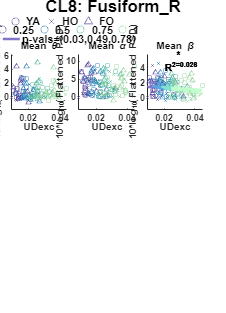

##8-theta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    group_char                        1.155        2      0.57749       0.50742    0.60323
    mean_StanceDur                 0.053393        1     0.053393      0.046914    0.82886
    group_char:mean_StanceDur       0.03322        2      0.01661      0.014595    0.98551
    Error                            147.95      130       1.1381                         
    Total                            160.97      135                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate       SE        tStat      pValue 
                                         _________    _______    ________    _______

    (Intercept)                            0.54349    0.34538      1.5736    0.11801
    group_char_H2000's                    -0.40476    0.68401    -0.59175    0.55505
    group_char_H3000's                     0.39994    0.64131     0.62363    0.53396
    mean_StanceDur                         0.11127    0.24942     0.44612    0.65625
    group_char_H2000's:mean_StanceDur    -0.090716    0.62046    -0.14621    0.88398
    group_char_H3000's:mean_StanceDur    -0.065921    0.58854   

##8-alpha_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                      6.0464         2      3.0232       0.50428     0.60512
    mean_StanceDur                  20.948         1      20.948        3.4943    0.063832
    group_char:mean_StanceDur       24.923         2      12.461        2.0786     0.12924
    Error                           779.36       130      5.9951                          
    Total                           897.85       135                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate      SE        tStat        pValue  
                                         ________    _______    ________    __________

    (Intercept)                            3.036     0.79269        3.83    0.00019845
    group_char_H2000's                   -1.0109      1.5699    -0.64395       0.52074
    group_char_H3000's                   -1.3493      1.4719    -0.91671       0.36099
    mean_StanceDur                       0.16646     0.57245     0.29079       0.77168
    group_char_H2000's:mean_StanceDur    0.26476       1.424     0.18592        0.8528
    group_char_H3000's:mean_StanceDur     2.7454  

##8-beta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                     0.63229         2      0.31614      0.25353    0.77644
    mean_StanceDur                  1.9138         1       1.9138       1.5348    0.21762
    group_char:mean_StanceDur        2.022         2        1.011      0.81079    0.44674
    Error                            162.1       130        1.247                        
    Total                           169.67       135                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate       SE         tStat        pValue  
                                         _________    _______    _________    __________

    (Intercept)                              1.278    0.36152        3.535    0.00056556
    group_char_H2000's                    -0.16211    0.71597     -0.22642       0.82123
    group_char_H3000's                    -0.47746    0.67128     -0.71126        0.4782
    mean_StanceDur                          0.1178    0.26107      0.45122       0.65259
    group_char_H2000's:mean_StanceDur    -0.055032    0.64946    -0.084735        0.9326
    group_char_H3000's:mean_StanceDur

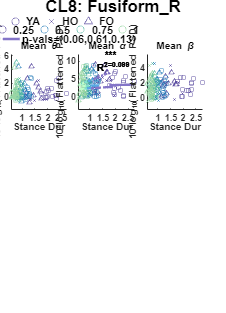

##8-theta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F        pValue 
                                    ____________    ___    ___________    ________    _______

    group_char                          1.0625        2      0.53125       0.46677    0.62807
    mean_GaitCycleDur                 0.064044        1     0.064044      0.056271    0.81286
    group_char:mean_GaitCycleDur      0.036547        2     0.018274      0.016056    0.98407
    Error                               147.96      130       1.1381                         
    Total                               160.97      135                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate       SE         tStat      pValue 
                                            _________    _______    _________    _______

    (Intercept)                               0.52185    0.40766       1.2801    0.20279
    group_char_H2000's                        -0.4672     0.8322      -0.5614    0.57549
    group_char_H3000's                        0.46297    0.75809      0.61071    0.54246
    mean_GaitCycleDur                        0.087493    0.20603      0.42466    0.67178
    group_char_H2000's:mean_GaitCycleDur    -0.016673    0.51833    -0.032166    0.97439
    group_char_H3000's:mean_GaitCycleDur</

##8-alpha_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares      F        pValue 
                                    ____________    ___    ___________    ______    ________

    group_char                         13.505         2      6.7523        1.145      0.3214
    mean_GaitCycleDur                  32.186         1      32.186        5.458    0.021008
    group_char:mean_GaitCycleDur       33.639         2       16.82       2.8523    0.061333
    Error                              766.61       130       5.897                         
    Total                              897.85       135                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate      SE        tStat       pValue  
                                            ________    _______    ________    _________

    (Intercept)                              3.0508     0.92793      3.2877    0.0012992
    group_char_H2000's                      -1.7523      1.8943    -0.92502      0.35667
    group_char_H3000's                      -2.4142      1.7256      -1.399      0.16418
    mean_GaitCycleDur                       0.10557     0.46897     0.22512      0.82224
    group_char_H2000's:mean_GaitCycleDur    0.67599      1.1798     0.57295      0.56767
    group_char_H3000's:mean_GaitCycleDur</

##8-beta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F       pValue 
                                    ____________    ___    ___________    _______    _______

    group_char                         1.5155         2      0.75775      0.61333     0.5431
    mean_GaitCycleDur                   3.312         1        3.312       2.6808    0.10398
    group_char:mean_GaitCycleDur       3.0153         2       1.5077       1.2203     0.2985
    Error                              160.61       130       1.2355                        
    Total                              169.67       135                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate      SE        tStat       pValue 
                                            ________    _______    ________    ________

    (Intercept)                               1.2849    0.42473      3.0252    0.002995
    group_char_H2000's                      -0.42961    0.86706    -0.49548      0.6211
    group_char_H3000's                      -0.85782    0.78984     -1.0861     0.27946
    mean_GaitCycleDur                       0.076596    0.21466     0.35683      0.7218
    group_char_H2000's:mean_GaitCycleDur     0.14226    0.54004     0.26342     0.79264
    group_char_H3000's:mean_GaitCycleDur 

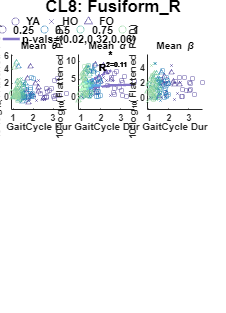

##8-theta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F        pValue 
                                          ____________    ___    ___________    ________    _______

    group_char                                 1.879        2      0.93952       0.82591    0.44012
    mean_PeakUpDownVel_mean                 0.046907        1     0.046907      0.041235     0.8394
    group_char:mean_PeakUpDownVel_mean       0.28389        2      0.14195       0.12478     0.8828
    Error                                     147.88      130       1.1376                         
    Total                                     160.97      135                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat       pValue 
                                                  ________    _______    ________    ________

    (Intercept)                                    0.75515     0.3274      2.3065    0.022666
    group_char_H2000's                            -0.63225    0.55837     -1.1323     0.25959
    group_char_H3000's                            0.070064    0.51022     0.13732     0.89099
    mean_PeakUpDownVel_mean                       -0.29835     1.2595    -0.23687     0.81313
    group_char_H2000's:mean_PeakUpDownVel_mean     0.44066     2.0538     0.21455     0.83045
    

##8-alpha_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F        pValue 
                                          ____________    ___    ___________    ________    _______

    group_char                               20.826         2       10.413        1.6726    0.19177
    mean_PeakUpDownVel_mean                  4.0148         1       4.0148       0.64488    0.42341
    group_char:mean_PeakUpDownVel_mean      0.78832         2      0.39416      0.063312    0.93868
    Error                                    809.33       130       6.2256                         
    Total                                    897.85       135                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat        pValue  
                                                  ________    _______    ________    __________

    (Intercept)                                     3.5902    0.76593      4.6873    6.8912e-06
    group_char_H2000's                            -0.94933     1.3063    -0.72675       0.46868
    group_char_H3000's                              1.5298     1.1936      1.2816       0.20226
    mean_PeakUpDownVel_mean                        -1.4534     2.9466    -0.49327       0.62265
    group_char_H2000's:mean_PeakUpDownVel_mean     0.69938     4.8048     0.14556       0.8

##8-beta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F        pValue 
                                          ____________    ___    ___________    _______    ________

    group_char                               3.2845         2       1.6422       1.3355     0.26661
    mean_PeakUpDownVel_mean                  4.2036         1       4.2036       3.4185    0.066741
    group_char:mean_PeakUpDownVel_mean       1.2515         2      0.62575      0.50888     0.60236
    Error                                    159.86       130       1.2297                         
    Total                                    169.67       135                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat        pValue  
                                                  ________    _______    ________    __________

    (Intercept)                                     1.7082     0.3404      5.0181    1.6795e-06
    group_char_H2000's                            -0.32908    0.58054    -0.56685        0.5718
    group_char_H3000's                             0.64026    0.53047       1.207       0.22964
    mean_PeakUpDownVel_mean                        -1.1898     1.3095    -0.90857       0.36526
    group_char_H2000's:mean_PeakUpDownVel_mean     0.39506     2.1354     0.18501       0.85

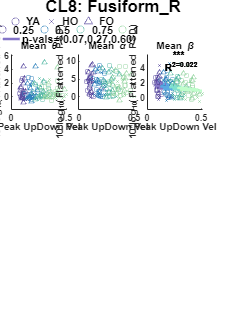

##9-theta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      1.6223         2      0.81114       1.3488    0.26152
    mean_APexc_COV                 0.50162         1      0.50162      0.83414      0.362
    group_char:mean_APexc_COV      0.56304         2      0.28152      0.46814    0.62674
    Error                           143.12       238      0.60136                        
    Total                           155.17       243                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue 
                                         _________    ________    ________    ________

    (Intercept)                            0.57204     0.32152      1.7791    0.076493
    group_char_H2000's                    -0.09835     0.52138    -0.18863     0.85054
    group_char_H3000's                    -0.69156     0.44728     -1.5461      0.1234
    mean_APexc_COV                        0.012422    0.019814     0.62695     0.53129
    group_char_H2000's:mean_APexc_COV    -0.015696     0.02671    -0.58765     0.55733
    group_char_H3000's:mean_APexc_COV    0.0052965

##9-alpha_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      11.556         2      5.7778         1.161    0.31496
    mean_APexc_COV                  1.5529         1      1.5529       0.31203    0.57696
    group_char:mean_APexc_COV       8.7845         2      4.3923       0.88256    0.41507
    Error                           1184.5       238      4.9767                         
    Total                           1202.9       243                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue  
                                         _________    ________    ________    _________

    (Intercept)                             2.5525     0.92495      2.7596    0.0062366
    group_char_H2000's                     -2.2777      1.4999     -1.5185       0.1302
    group_char_H3000's                     -1.0117      1.2867    -0.78628      0.43249
    mean_APexc_COV                       -0.038789       0.057     -0.6805      0.49685
    group_char_H2000's:mean_APexc_COV      0.10171    0.076838      1.3236      0.18689
    group_char_H3000's:mean_APexc_COV     0

##9-beta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      6.6208         2       3.3104      0.87474    0.41831
    mean_APexc_COV                 0.42733         1      0.42733      0.11292    0.73714
    group_char:mean_APexc_COV       9.1474         2       4.5737       1.2086    0.30045
    Error                           900.69       238       3.7844                        
    Total                            980.6       243                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE         tStat        pValue  
                                         _________    ________    _________    __________

    (Intercept)                             2.8708     0.80658       3.5592    0.00044896
    group_char_H2000's                     -1.5659      1.3079      -1.1972        0.2324
    group_char_H3000's                   -0.030017      1.1221    -0.026752       0.97868
    mean_APexc_COV                       -0.048771    0.049705      -0.9812       0.32749
    group_char_H2000's:mean_APexc_COV      0.10268    0.067004       1.5324       0.12675
    group_char_H3000's:mean_APexc_COV</

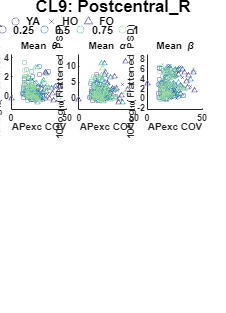

##9-theta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                       1.3228         2      0.66142       1.0958    0.33597
    mean_APexc_mean                 0.57702         1      0.57702      0.95593    0.32921
    group_char:mean_APexc_mean      0.60708         2      0.30354      0.50286    0.60544
    Error                            143.66       238      0.60362                        
    Total                            155.17       243                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate       SE         tStat        pValue  
                                          _________    _______    __________    _________

    (Intercept)                             0.80279    0.28532        2.8136    0.0053078
    group_char_H2000's                    -0.013311    0.43409     -0.030664      0.97556
    group_char_H3000's                      -0.4635    0.36169       -1.2815      0.20128
    mean_APexc_mean                        -0.65285     5.0582      -0.12907      0.89741
    group_char_H2000's:mean_APexc_mean      -7.4848     8.2534      -0.90687      0.36539
    group_char_H3000's:mean_APexc_mea

##9-alpha_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                       2.0192         2      1.0096       0.20236    0.81694
    mean_APexc_mean                  4.5518         1      4.5518       0.91233    0.34047
    group_char:mean_APexc_mean        4.027         2      2.0135       0.40357    0.66839
    Error                            1187.4       238      4.9892                         
    Total                            1202.9       243                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE         tStat        pValue 
                                          ________    _______    __________    ________

    (Intercept)                             1.9485    0.82029        2.3754    0.018325
    group_char_H2000's                    -0.67304      1.248       -0.5393     0.59019
    group_char_H3000's                    -0.59082     1.0399      -0.56817     0.57045
    mean_APexc_mean                       -0.11091     14.542    -0.0076269     0.99392
    group_char_H2000's:mean_APexc_mean      8.4391     23.728       0.35565     0.72242
    group_char_H3000's:mean_APexc_mean    

##9-beta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares      F        pValue 
                                  ____________    ___    ___________    ______    ________

    group_char                        32.26         2       16.13       4.3062    0.014551
    mean_APexc_mean                  5.2663         1      5.2663       1.4059     0.23692
    group_char:mean_APexc_mean        17.97         2       8.985       2.3987    0.093028
    Error                            891.49       238      3.7458                         
    Total                             980.6       243                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                            2.1593     0.71075       3.038    0.0026472
    group_char_H2000's                    -1.3923      1.0813     -1.2876      0.19915
    group_char_H3000's                     1.4302     0.90101      1.5874      0.11375
    mean_APexc_mean                       -1.0253        12.6    -0.08137      0.93522
    group_char_H2000's:mean_APexc_mean     37.381       20.56      1.8182     0.070296
    group_char_H3000's:mean_APexc_mean    -5.6585 

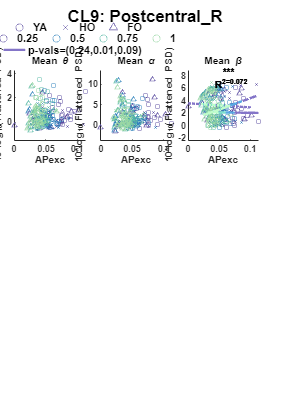

##9-theta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    group_char                       1.6586        2      0.82929        1.3747    0.25492
    mean_MLexc_COV                   1.0124        1       1.0124        1.6782    0.19642
    group_char:mean_MLexc_COV      0.076015        2     0.038008      0.063003    0.93896
    Error                            143.58      238      0.60326                         
    Total                            155.17      243                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue 
                                         _________    ________    ________    ________

    (Intercept)                             0.6376     0.22005      2.8975    0.004112
    group_char_H2000's                    -0.46913     0.34053     -1.3776     0.16961
    group_char_H3000's                    -0.47875     0.33791     -1.4168     0.15785
    mean_MLexc_COV                       0.0089542     0.01416     0.63236     0.52776
    group_char_H2000's:mean_MLexc_COV    0.0077838    0.022327     0.34862     0.72768
    group_char_H3000's:mean_MLexc_COV    0.0017741

##9-alpha_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      9.4432         2      4.7216       0.95631    0.38578
    mean_MLexc_COV                  3.9306         1      3.9306       0.79609    0.37317
    group_char:mean_MLexc_COV       15.717         2      7.8584        1.5916    0.20575
    Error                           1175.1       238      4.9373                         
    Total                           1202.9       243                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                          Estimate        SE        tStat        pValue  
                                         __________    ________    ________    __________

    (Intercept)                              2.7437     0.62953      4.3583    1.9504e-05
    group_char_H2000's                      -0.2104      0.9742    -0.21597        0.8292
    group_char_H3000's                      -1.2858     0.96671     -1.3301       0.18477
    mean_MLexc_COV                        -0.055269    0.040509     -1.3644       0.17374
    group_char_H2000's:mean_MLexc_COV    -0.0066697    0.063875    -0.10442       0.91693
    group_char_H3000's:mean_MLexc_COV<

##9-beta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      4.3969         2      2.1984       0.58033    0.56051
    mean_MLexc_COV                  5.1969         1      5.1969        1.3718    0.24267
    group_char:mean_MLexc_COV       4.3568         2      2.1784       0.57504    0.56346
    Error                           901.61       238      3.7883                         
    Total                            980.6       243                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             2.5162     0.55143      4.5631    8.0785e-06
    group_char_H2000's                     0.81499     0.85334     0.95506       0.34052
    group_char_H3000's                     0.72325     0.84678     0.85412        0.3939
    mean_MLexc_COV                       -0.028455    0.035483    -0.80193       0.42339
    group_char_H2000's:mean_MLexc_COV    -0.031191    0.055951    -0.55748       0.57773
    group_char_H3000's:mean_MLexc_COV

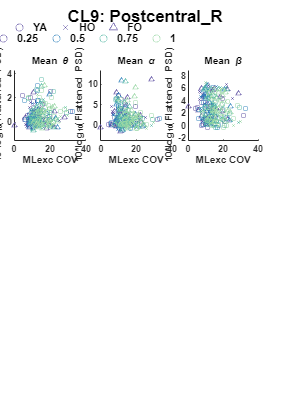

##9-theta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    _______    ________

    group_char                        3.3311        2       1.6655       2.7963    0.063042
    mean_MLexc_mean                 0.019804        1     0.019804      0.03325     0.85547
    group_char:mean_MLexc_mean        2.8036        2       1.4018       2.3535    0.097244
    Error                             141.76      238      0.59562                         
    Total                             155.17      243                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat      pValue 
                                          ________    _______    _______    ________

    (Intercept)                            0.60479    0.23385     2.5863    0.010298
    group_char_H2000's                     0.19266    0.35429    0.54378      0.5871
    group_char_H3000's                    -0.53623    0.31053    -1.7268    0.085503
    mean_MLexc_mean                         2.0126      2.725    0.73857     0.46089
    group_char_H2000's:mean_MLexc_mean     -6.1471     3.7481      -1.64     0.10232
    group_char_H3000's:mean_MLexc_mean     0.90619     3.5334  

##9-alpha_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares        F        pValue 
                                  ____________    ___    ___________    _________    _______

    group_char                       0.93956        2      0.46978       0.094262    0.91008
    mean_MLexc_mean                   9.6373        1       9.6373         1.9337    0.16565
    group_char:mean_MLexc_mean      0.062802        2     0.031401      0.0063007    0.99372
    Error                             1186.1      238       4.9838                          
    Total                             1202.9      243                                       



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE         tStat       pValue 
                                          ________    _______    _________    ________

    (Intercept)                             1.4839    0.67644       2.1937    0.029221
    group_char_H2000's                    -0.33173     1.0248     -0.32369     0.74646
    group_char_H3000's                    0.081045    0.89826     0.090224     0.92818
    mean_MLexc_mean                          5.675     7.8826      0.71995     0.47226
    group_char_H2000's:mean_MLexc_mean     -0.2438     10.842    -0.022487     0.98208
    group_char_H3000's:mean_MLexc_mean     0.8019

##9-beta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares      F        pValue 
                                  ____________    ___    ___________    ______    ________

    group_char                       51.874         2      25.937       6.9378    0.001179
    mean_MLexc_mean                  1.3021         1      1.3021       0.3483     0.55564
    group_char:mean_MLexc_mean       21.326         2      10.663       2.8522    0.059693
    Error                            889.77       238      3.7385                         
    Total                             980.6       243                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                             1.5516    0.58586      2.6484    0.0086287
    group_char_H2000's                    0.083521    0.88762    0.094095      0.92511
    group_char_H3000's                      2.5503    0.77799       3.278    0.0012016
    mean_MLexc_mean                         6.8331     6.8271      1.0009       0.3179
    group_char_H2000's:mean_MLexc_mean      2.2144     9.3903     0.23582      0.81378
    group_char_H3000's:mean_MLexc_mean     -16.251

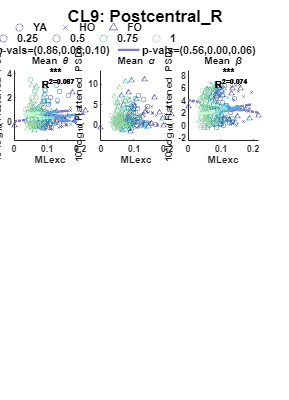

##9-theta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F       pValue 
                               ____________    ___    ___________    _______    _______

    group_char                    0.2368         2       0.1184      0.19726    0.82111
    mean_StepDur                  1.7638         1       1.7638       2.9387    0.08778
    group_char:mean_StepDur      0.62878         2      0.31439       0.5238    0.59295
    Error                         142.85       238       0.6002                        
    Total                         155.17       243                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate       SE         tStat        pValue  
                                       _________    _______    _________    __________

    (Intercept)                           0.8804    0.23675       3.7186    0.00024986
    group_char_H2000's                 -0.010868    0.45142    -0.024076       0.98081
    group_char_H3000's                  -0.24157    0.39988      -0.6041       0.54635
    mean_StepDur                        -0.12399     0.2449      -0.5063       0.61312
    group_char_H2000's:mean_StepDur     -0.48343    0.53981     -0.89555        0.3714
    group_char_H3000's:mean_StepDur     -0.34599    

##9-alpha_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F        pValue 
                               ____________    ___    ___________    ________    _______

    group_char                   0.93772         2      0.46886      0.093404    0.91086
    mean_StepDur                  1.5944         1       1.5944       0.31763    0.57357
    group_char:mean_StepDur        0.318         2        0.159      0.031675    0.96883
    Error                         1194.7       238       5.0197                         
    Total                         1202.9       243                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate      SE        tStat       pValue 
                                       ________    _______    ________    ________

    (Intercept)                          1.7722    0.68468      2.5884    0.010236
    group_char_H2000's                 -0.51866     1.3055    -0.39729     0.69151
    group_char_H3000's                 0.044422     1.1564    0.038413     0.96939
    mean_StepDur                        0.18684    0.70824      0.2638     0.79216
    group_char_H2000's:mean_StepDur     0.35698     1.5611     0.22867     0.81932
    group_char_H3000's:mean_StepDur     0.22475     1.4738      0.1525     0.878

##9-beta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F       pValue 
                               ____________    ___    ___________    _______    _______

    group_char                    6.2768         2       3.1384      0.82444    0.43973
    mean_StepDur                  4.8279         1       4.8279       1.2683    0.26123
    group_char:mean_StepDur       1.3924         2      0.69622      0.18289    0.83298
    Error                            906       238       3.8067                        
    Total                          980.6       243                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate      SE        tStat      pValue  
                                       ________    _______    _______    _________

    (Intercept)                          1.8016    0.59624     3.0217    0.0027886
    group_char_H2000's                 -0.18883     1.1369    -0.1661      0.86822
    group_char_H3000's                    1.167     1.0071     1.1588      0.24771
    mean_StepDur                        0.33149    0.61676    0.53747      0.59144
    group_char_H2000's:mean_StepDur     0.82221     1.3595     0.6048      0.54589
    group_char_H3000's:mean_StepDur     0.17094     1.2835    0.13319      0.8941

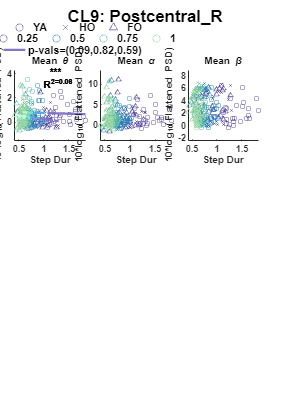

##9-theta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                      3.1196         2       1.5598       2.5813    0.077794
    mean_UDexc_COV                 0.15689         1      0.15689      0.25963     0.61084
    group_char:mean_UDexc_COV      0.59542         2      0.29771      0.49267     0.61162
    Error                           143.82       238      0.60428                         
    Total                           155.17       243                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                            0.93988     0.19965      4.7076    4.2574e-06
    group_char_H2000's                    -0.63979     0.31088      -2.058      0.040682
    group_char_H3000's                    -0.52774     0.30253     -1.7444      0.082374
    mean_UDexc_COV                       -0.013762    0.014619    -0.94137       0.34747
    group_char_H2000's:mean_UDexc_COV      0.02127    0.021741     0.97834        0.3289
    group_char_H3000's:mean_UDexc_COV

##9-alpha_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    group_char                      0.2812         2      0.1406       0.028156    0.97224
    mean_UDexc_COV                  5.3992         1      5.3992         1.0812    0.29948
    group_char:mean_UDexc_COV       2.8318         2      1.4159        0.28355    0.75336
    Error                           1188.5       238      4.9935                          
    Total                           1202.9       243                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                         Estimate        SE         tStat        pValue  
                                         _________    ________    _________    __________

    (Intercept)                             2.2007     0.57393       3.8344    0.00016122
    group_char_H2000's                     0.18438     0.89368      0.20632       0.83672
    group_char_H3000's                   -0.016298     0.86966    -0.018741       0.98506
    mean_UDexc_COV                       -0.020603    0.042025     -0.49027        0.6244
    group_char_H2000's:mean_UDexc_COV    -0.032405    0.062497      -0.5185       0.60459
    group_char_H3000's:mean_UDexc_COV<

##9-beta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    group_char                      3.1174         2       1.5587       0.41101    0.66345
    mean_UDexc_COV                 0.15175         1      0.15175      0.040014    0.84162
    group_char:mean_UDexc_COV       8.5981         2       4.2991        1.1336    0.32361
    Error                           902.61       238       3.7925                         
    Total                            980.6       243                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue  
                                         _________    ________    ________    _________

    (Intercept)                             2.3212     0.50017      4.6407    5.737e-06
    group_char_H2000's                     0.68947     0.77882     0.88527       0.3769
    group_char_H3000's                     0.41871     0.75789     0.55247      0.58114
    mean_UDexc_COV                        -0.01735    0.036624    -0.47374      0.63612
    group_char_H2000's:mean_UDexc_COV    -0.020456    0.054465    -0.37558      0.70756
    group_char_H3000's:mean_UDexc_COV     0.

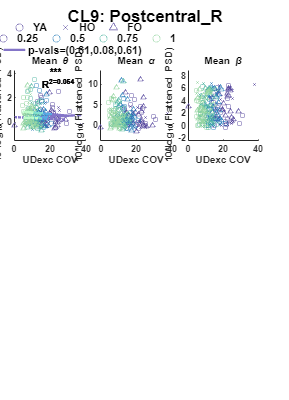

##9-theta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                       1.7958         2      0.89789       1.4841     0.2288
    mean_UDexc_mean                 0.41579         1      0.41579      0.68724    0.40794
    group_char:mean_UDexc_mean      0.13464         2     0.067322      0.11127    0.89474
    Error                            143.99       238      0.60502                        
    Total                            155.17       243                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                            0.67471    0.23084      2.9228    0.0038034
    group_char_H2000's                    -0.31816    0.36503    -0.87159      0.38431
    group_char_H3000's                    -0.55089    0.32028       -1.72     0.086729
    mean_UDexc_mean                         3.8801     9.0726     0.42767      0.66928
    group_char_H2000's:mean_UDexc_mean     -2.1423     13.763    -0.15565      0.87644
    group_char_H3000's:mean_UDexc_mean      3.964

##9-alpha_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                       6.7163         2      3.3581       0.67238    0.51146
    mean_UDexc_mean                  2.0678         1      2.0678       0.41401    0.52056
    group_char:mean_UDexc_mean       5.8344         2      2.9172       0.58409    0.55841
    Error                            1188.7       238      4.9944                         
    Total                            1202.9       243                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                             2.2622    0.66325      3.4108    0.00076075
    group_char_H2000's                     -1.2028     1.0488     -1.1468       0.25261
    group_char_H3000's                    -0.62183    0.92021    -0.67574       0.49986
    mean_UDexc_mean                        -13.384     26.067    -0.51345       0.60812
    group_char_H2000's:mean_UDexc_mean      37.408     39.543     0.94601       0.34511
    group_char_H3000's:mean_UDexc_mean    

##9-beta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    _______    ________

    group_char                       30.468         2      15.234        4.0507    0.018624
    mean_UDexc_mean                  1.0945         1      1.0945       0.29103     0.59006
    group_char:mean_UDexc_mean       13.583         2      6.7916        1.8059     0.16657
    Error                            895.08       238      3.7608                          
    Total                             980.6       243                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                             2.4856    0.57554      4.3187    2.3054e-05
    group_char_H2000's                    -0.71514     0.9101    -0.78579       0.43277
    group_char_H3000's                      1.6584    0.79852      2.0768      0.038892
    mean_UDexc_mean                        -15.983      22.62    -0.70659       0.48051
    group_char_H2000's:mean_UDexc_mean      44.657     34.314      1.3014       0.19437
    group_char_H3000's:mean_UDexc_mean     

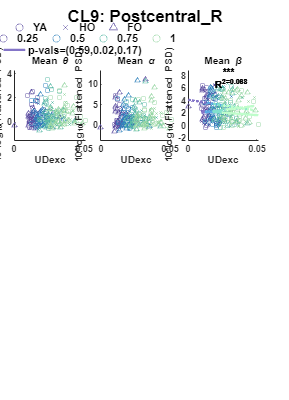

##9-theta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                     0.74126         2      0.37063      0.61715    0.54034
    mean_StanceDur                  1.6155         1       1.6155       2.6899    0.10231
    group_char:mean_StanceDur      0.48014         2      0.24007      0.39974    0.67094
    Error                           142.93       238      0.60056                        
    Total                           155.17       243                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate       SE        tStat       pValue  
                                         _________    _______    ________    _________

    (Intercept)                            0.88815    0.19763      4.4939    1.092e-05
    group_char_H2000's                    -0.09752    0.36934    -0.26404      0.79198
    group_char_H3000's                    -0.37156    0.33553     -1.1074      0.26925
    mean_StanceDur                       -0.097348    0.14604     -0.6666      0.50567
    group_char_H2000's:mean_StanceDur     -0.27904    0.32064    -0.87025      0.38504
    group_char_H3000's:mean_StanceDur     -0.12004

##9-alpha_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      1.7183         2      0.85916      0.17168    0.84235
    mean_StanceDur                  5.1774         1       5.1774       1.0346    0.31012
    group_char:mean_StanceDur       1.7647         2      0.88233      0.17631    0.83847
    Error                             1191       238       5.0044                        
    Total                           1202.9       243                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate      SE        tStat       pValue  
                                         ________    _______    ________    _________

    (Intercept)                            1.7738    0.57051      3.1092    0.0021044
    group_char_H2000's                   -0.62112     1.0662    -0.58257      0.56073
    group_char_H3000's                   -0.23578    0.96857    -0.24343      0.80788
    mean_StanceDur                        0.13598    0.42156     0.32256      0.74731
    group_char_H2000's:mean_StanceDur     0.36663    0.92559     0.39611      0.69238
    group_char_H3000's:mean_StanceDur      0.4627    0.89

##9-beta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      9.0295         2       4.5147       1.1893    0.30625
    mean_StanceDur                  6.9509         1       6.9509        1.831    0.17729
    group_char:mean_StanceDur       1.9667         2      0.98335      0.25903    0.77201
    Error                            903.5       238       3.7962                        
    Total                            980.6       243                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate      SE        tStat        pValue  
                                         ________    _______    ________    __________

    (Intercept)                            1.7963    0.49689       3.615    0.00036651
    group_char_H2000's                   -0.15074    0.92859    -0.16233       0.87119
    group_char_H3000's                     1.1847    0.84359      1.4044       0.16152
    mean_StanceDur                        0.24789    0.36717     0.67514       0.50024
    group_char_H2000's:mean_StanceDur     0.58014    0.80615     0.71964       0.47246
    group_char_H3000's:mean_StanceDur      0.1098  

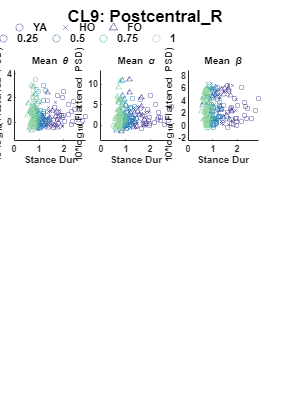

##9-theta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F        pValue 
                                    ____________    ___    ___________    _______    ________

    group_char                        0.23477         2      0.11739      0.19556      0.8225
    mean_GaitCycleDur                  1.7551         1       1.7551        2.924    0.088573
    group_char:mean_GaitCycleDur       0.6215         2      0.31075      0.51771     0.59655
    Error                              142.86       238      0.60024                         
    Total                              155.17       243                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate       SE         tStat        pValue  
                                            _________    _______    _________    __________

    (Intercept)                               0.88045    0.23645       3.7237    0.00024518
    group_char_H2000's                      -0.015743    0.44976    -0.035003       0.97211
    group_char_H3000's                       -0.24153    0.39966     -0.60434       0.54619
    mean_GaitCycleDur                       -0.061985    0.12219     -0.50727       0.61243
    group_char_H2000's:mean_GaitCycleDur     -0.23832    0.26854     -0.88748       0.37572
    group_char_H3000'

##9-alpha_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F        pValue 
                                    ____________    ___    ___________    ________    _______

    group_char                        0.91925         2      0.45963      0.091566    0.91253
    mean_GaitCycleDur                  1.6136         1       1.6136       0.32146    0.57127
    group_char:mean_GaitCycleDur      0.31294         2      0.15647      0.031172    0.96931
    Error                              1194.7       238       5.0196                         
    Total                              1202.9       243                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate      SE        tStat       pValue 
                                            ________    _______    ________    ________

    (Intercept)                               1.7699    0.68376      2.5885    0.010232
    group_char_H2000's                      -0.51234     1.3006    -0.39392       0.694
    group_char_H3000's                      0.042081     1.1557     0.03641     0.97099
    mean_GaitCycleDur                       0.094608    0.35336     0.26774     0.78913
    group_char_H2000's:mean_GaitCycleDur     0.17443    0.77657     0.22462     0.82247
    group_char_H3000's:mean_GaitCycleDur

##9-beta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F       pValue 
                                    ____________    ___    ___________    _______    _______

    group_char                         6.2478         2       3.1239      0.82064    0.44139
    mean_GaitCycleDur                  4.8489         1       4.8489       1.2738    0.26019
    group_char:mean_GaitCycleDur        1.392         2      0.69602      0.18284    0.83302
    Error                              905.98       238       3.8066                        
    Total                               980.6       243                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate      SE        tStat       pValue  
                                            ________    _______    ________    _________

    (Intercept)                               1.8021    0.59545      3.0265    0.0027463
    group_char_H2000's                      -0.18621     1.1326    -0.16441      0.86955
    group_char_H3000's                        1.1639     1.0065      1.1564      0.24868
    mean_GaitCycleDur                        0.16539    0.30772     0.53749      0.59143
    group_char_H2000's:mean_GaitCycleDur     0.40894    0.67626      0.6047      0.54595
    group_char_H3000's:mean_GaitCycleDur

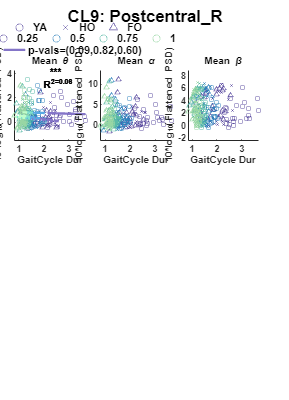

##9-theta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares      F        pValue 
                                          ____________    ___    ___________    ______    ________

    group_char                               2.9256         2       1.4628      2.4308    0.090147
    mean_PeakUpDownVel_mean                 0.94716         1      0.94716       1.574     0.21086
    group_char:mean_PeakUpDownVel_mean      0.35024         2      0.17512       0.291     0.74778
    Error                                    143.22       238      0.60177                        
    Total                                    155.17       243                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat       pValue  
                                                  ________    _______    ________    _________

    (Intercept)                                    0.66555    0.18906      3.5204    0.0005163
    group_char_H2000's                            -0.32069    0.30373     -1.0559       0.2921
    group_char_H3000's                            -0.60814     0.2763      -2.201     0.028695
    mean_PeakUpDownVel_mean                        0.43332    0.73032     0.59333      0.55353
    group_char_H2000's:mean_PeakUpDownVel_mean    -0.22148     1.0938    -0.20249      0.83971
  

##9-alpha_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F        pValue 
                                          ____________    ___    ___________    ________    _______

    group_char                               6.7757         2       3.3878       0.67587    0.50969
    mean_PeakUpDownVel_mean                 0.25794         1      0.25794      0.051459    0.82074
    group_char:mean_PeakUpDownVel_mean        3.217         2       1.6085       0.32089    0.72582
    Error                                      1193       238       5.0126                         
    Total                                    1202.9       243                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat        pValue  
                                                  ________    _______    ________    __________

    (Intercept)                                     2.0923    0.54564      3.8345    0.00016113
    group_char_H2000's                            -0.88324    0.87659     -1.0076       0.31468
    group_char_H3000's                            0.076331    0.79743    0.095722       0.92382
    mean_PeakUpDownVel_mean                       -0.63724     2.1078    -0.30233       0.76267
    group_char_H2000's:mean_PeakUpDownVel_mean        2.39     3.1569     0.75707       0.4

##9-beta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares      F        pValue 
                                          ____________    ___    ___________    ______    ________

    group_char                               29.449         2      14.724       3.9161    0.021214
    mean_PeakUpDownVel_mean                  4.9813         1      4.9813       1.3249     0.25088
    group_char:mean_PeakUpDownVel_mean       9.8598         2      4.9299       1.3112     0.27144
    Error                                    894.86       238      3.7599                         
    Total                                     980.6       243                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat        pValue  
                                                  ________    _______    ________    __________

    (Intercept)                                     2.5277    0.47257      5.3489    2.0758e-07
    group_char_H2000's                            -0.34107     0.7592    -0.44925       0.65366
    group_char_H3000's                              1.5939    0.69064      2.3079      0.021863
    mean_PeakUpDownVel_mean                        -1.8037     1.8255    -0.98806       0.32413
    group_char_H2000's:mean_PeakUpDownVel_mean       2.998     2.7341      1.0965       0.27

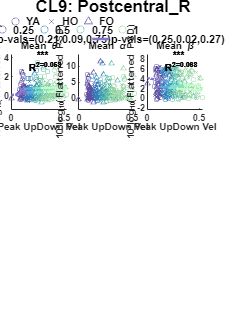

##10-theta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      1.8614         2      0.93069       1.5872    0.20681
    mean_APexc_COV                 0.15737         1      0.15737      0.26839    0.60493
    group_char:mean_APexc_COV       2.1247         2       1.0623       1.8117    0.16578
    Error                           130.17       222      0.58637                        
    Total                           133.22       227                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue 
                                         _________    ________    ________    ________

    (Intercept)                            0.99074     0.32211      3.0758    0.002363
    group_char_H2000's                   -0.057901     0.53919    -0.10738     0.91458
    group_char_H3000's                    -0.83685     0.49764     -1.6816    0.094045
    mean_APexc_COV                         -0.0192    0.019566    -0.98128     0.32753
    group_char_H2000's:mean_APexc_COV    0.0017288    0.026952    0.064145     0.94891
    group_char_H3000's:mean_APexc_COV     0.039793

##10-alpha_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      18.146         2       9.073        1.3748    0.25502
    mean_APexc_COV                  2.5375         1      2.5375       0.38451    0.53583
    group_char:mean_APexc_COV       18.866         2      9.4332        1.4294    0.24164
    Error                             1465       222      6.5993                         
    Total                           1504.6       227                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate       SE        tStat        pValue  
                                         ________    ________    ________    __________

    (Intercept)                            4.0645      1.0806      3.7614    0.00021621
    group_char_H2000's                    -1.5742      1.8089    -0.87027       0.38509
    group_char_H3000's                    -2.7349      1.6695     -1.6382       0.10279
    mean_APexc_COV                       -0.10641     0.06564     -1.6212        0.1064
    group_char_H2000's:mean_APexc_COV     0.11932    0.090416      1.3197       0.18829
    group_char_H3000's:mean_APexc_COV     0

##10-beta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      1.4796         2      0.73981      0.41272    0.66235
    mean_APexc_COV                 0.18747         1      0.18747      0.10459     0.7467
    group_char:mean_APexc_COV       1.4595         2      0.72977      0.40712    0.66606
    Error                           397.94       222       1.7925                        
    Total                           421.49       227                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue  
                                         _________    ________    ________    _________

    (Intercept)                             1.9231     0.56318      3.4146    0.0007592
    group_char_H2000's                     0.05403     0.94273    0.057313      0.95435
    group_char_H3000's                    -0.70828     0.87008    -0.81404       0.4165
    mean_APexc_COV                       -0.029771     0.03421    -0.87024      0.38511
    group_char_H2000's:mean_APexc_COV     0.035018    0.047123     0.74312       0.4582
    group_char_H3000's:mean_APexc_COV     0.

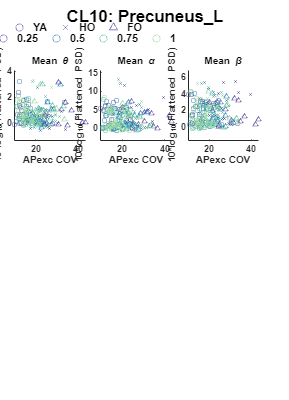

##10-theta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                        0.968         2        0.484      0.82619    0.43906
    mean_APexc_mean                  1.3456         1       1.3456        2.297    0.13105
    group_char:mean_APexc_mean       1.0553         2      0.52763      0.90066    0.40778
    Error                            130.05       222      0.58582                        
    Total                            133.22       227                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate       SE        tStat       pValue 
                                          _________    _______    ________    ________

    (Intercept)                              0.7485     0.2888      2.5917    0.010183
    group_char_H2000's                    -0.094565    0.40699    -0.23235     0.81648
    group_char_H3000's                      0.38039    0.39574     0.96122     0.33749
    mean_APexc_mean                         -1.1724      5.087    -0.23048     0.81793
    group_char_H2000's:mean_APexc_mean      -1.5872     8.0851    -0.19632     0.84454
    group_char_H3000's:mean_APexc_mean      -10.0

##10-alpha_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares        F        pValue 
                                  ____________    ___    ___________    _________    _______

    group_char                       0.45392        2      0.22696       0.033976     0.9666
    mean_APexc_mean                 0.061191        1     0.061191      0.0091604    0.92384
    group_char:mean_APexc_mean        1.7101        2      0.85505          0.128    0.87992
    Error                               1483      222         6.68                          
    Total                             1504.6      227                                       



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue 
                                          ________    _______    ________    ________

    (Intercept)                            2.1515     0.97523      2.2061    0.028402
    group_char_H2000's                    0.35816      1.3743     0.26061     0.79463
    group_char_H3000's                    0.17361      1.3363     0.12992     0.89675
    mean_APexc_mean                        3.9569      17.178     0.23035     0.81803
    group_char_H2000's:mean_APexc_mean     2.4101      27.302    0.088277     0.92974
    group_char_H3000's:mean_APexc_mean     -11.04      2

##10-beta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                       7.1014         2       3.5507       1.9824    0.14017
    mean_APexc_mean                 0.18772         1      0.18772      0.10481    0.74644
    group_char:mean_APexc_mean       1.4585         2      0.72926      0.40715    0.66604
    Error                            397.63       222       1.7911                        
    Total                            421.49       227                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE         tStat       pValue 
                                          ________    _______    _________    ________

    (Intercept)                             1.1033    0.50499       2.1847    0.029957
    group_char_H2000's                      1.2425    0.71164       1.7459     0.08221
    group_char_H3000's                    0.058893    0.69197      0.08511     0.93225
    mean_APexc_mean                          6.323     8.8948      0.71086     0.47792
    group_char_H2000's:mean_APexc_mean     -12.092     14.137     -0.85531      0.3933
    group_char_H3000's:mean_APexc_mean     -1.2006

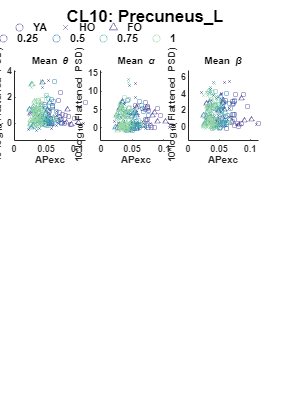

##10-theta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                     0.065626        2     0.032813      0.05531     0.9462
    mean_MLexc_COV                   0.2633        1       0.2633      0.44382    0.50597
    group_char:mean_MLexc_COV       0.27607        2      0.13804      0.23268     0.7926
    Error                             131.7      222      0.59326                        
    Total                            133.22      227                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue 
                                         _________    ________    ________    ________

    (Intercept)                             0.5376     0.22366      2.4037    0.017053
    group_char_H2000's                    0.044652     0.36128     0.12359     0.90175
    group_char_H3000's                    -0.08924     0.37122     -0.2404     0.81025
    mean_MLexc_COV                       0.0099004    0.014066     0.70384     0.48227
    group_char_H2000's:mean_MLexc_COV    -0.013285    0.023719    -0.56008     0.57599
    group_char_H3000's:mean_MLexc_COV    0.0043748

##10-alpha_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares      F       pValue 
                                 ____________    ___    ___________    ______    _______

    group_char                      13.351         2      6.6755       1.0102     0.3658
    mean_MLexc_COV                  13.186         1      13.186       1.9955    0.15917
    group_char:mean_MLexc_COV       7.2131         2      3.6066       0.5458    0.58015
    Error                           1466.9       222      6.6079                        
    Total                           1504.6       227                                    



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE         tStat        pValue  
                                         _________    ________    _________    __________

    (Intercept)                             2.5897     0.74644       3.4694    0.00062645
    group_char_H2000's                      1.5581      1.2057       1.2923       0.19761
    group_char_H3000's                   -0.083407      1.2389    -0.067322       0.94639
    mean_MLexc_COV                       -0.014984    0.046945     -0.31918       0.74989
    group_char_H2000's:mean_MLexc_COV    -0.082202     0.07916      -1.0384        0.3002
    group_char_H3000's:mean_MLexc_COV<

##10-beta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares      F        pValue 
                                 ____________    ___    ___________    ______    ________

    group_char                      9.3599         2        4.68       2.6465    0.073133
    mean_MLexc_COV                  3.3974         1      3.3974       1.9212     0.16711
    group_char:mean_MLexc_COV       5.5172         2      2.7586         1.56     0.21243
    Error                           392.57       222      1.7683                         
    Total                           421.49       227                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat      pValue  
                                         _________    ________    _______    _________

    (Intercept)                             1.2269     0.38614     3.1774    0.0016975
    group_char_H2000's                      1.3856     0.62373     2.2215     0.027328
    group_char_H3000's                     0.88689     0.64091     1.3838      0.16781
    mean_MLexc_COV                        0.014914    0.024285    0.61411      0.53977
    group_char_H2000's:mean_MLexc_COV     -0.05169     0.04095    -1.2623      0.20818
    group_char_H3000's:mean_MLexc_COV    -0.067735 

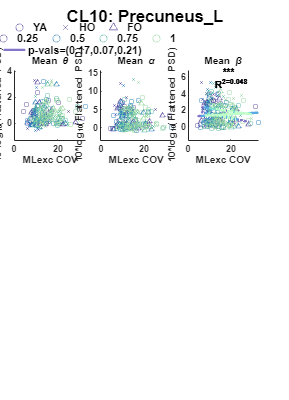

##10-theta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    ________    _______

    group_char                      0.04961         2     0.024805      0.042096    0.95879
    mean_MLexc_mean                 0.97727         1      0.97727        1.6585    0.19914
    group_char:mean_MLexc_mean      0.32409         2      0.16205       0.27501    0.75982
    Error                            130.81       222      0.58924                         
    Total                            133.22       227                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                            0.73587    0.23784       3.094    0.0022285
    group_char_H2000's                    0.092125    0.32909     0.27994      0.77979
    group_char_H3000's                    0.070729    0.34245     0.20654      0.83656
    mean_MLexc_mean                       -0.63542     2.7721    -0.22922      0.81891
    group_char_H2000's:mean_MLexc_mean     -2.6216     3.6054    -0.72711      0.46792
    group_char_H3000's:mean_MLexc_mean     -1.105

##10-alpha_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                       5.3776         2       2.6888      0.40262    0.66905
    mean_MLexc_mean                 0.57058         1      0.57058      0.08544    0.77033
    group_char:mean_MLexc_mean       1.8373         2      0.91866      0.13756    0.87155
    Error                            1482.5       222       6.6781                        
    Total                            1504.6       227                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                             2.7835    0.80068      3.4764    0.00061125
    group_char_H2000's                    0.035874     1.1079    0.032381        0.9742
    group_char_H3000's                    -0.87545     1.1529    -0.75937       0.44844
    mean_MLexc_mean                        -5.1505     9.3324    -0.55189       0.58158
    group_char_H2000's:mean_MLexc_mean      4.7636     12.138     0.39246       0.69509
    group_char_H3000's:mean_MLexc_mean    

##10-beta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    ________    _______

    group_char                       5.0603         2       2.5302        1.4084    0.24671
    mean_MLexc_mean                 0.16619         1      0.16619      0.092509     0.7613
    group_char:mean_MLexc_mean      0.48823         2      0.24412       0.13589    0.87301
    Error                            398.82       222       1.7965                         
    Total                            421.49       227                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                             1.5976    0.41528       3.847    0.00015627
    group_char_H2000's                     0.63935    0.57462      1.1126       0.26706
    group_char_H3000's                    -0.31589    0.59794    -0.52829       0.59782
    mean_MLexc_mean                        -1.8485     4.8404     -0.3819        0.7029
    group_char_H2000's:mean_MLexc_mean     0.29003     6.2954    0.046071        0.9633
    group_char_H3000's:mean_MLexc_mean     

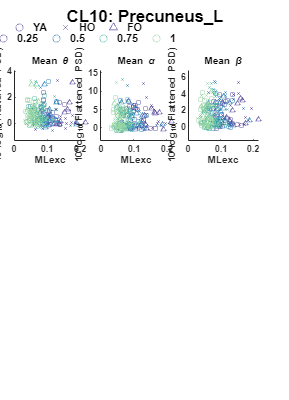

##10-theta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F       pValue 
                               ____________    ___    ___________    _______    _______

    group_char                   0.73939         2      0.36969      0.62792    0.53464
    mean_StepDur                  1.3541         1       1.3541       2.2999     0.1308
    group_char:mean_StepDur       1.0217         2      0.51087      0.86771    0.42133
    Error                          130.7       222      0.58875                        
    Total                         133.22       227                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate       SE        tStat       pValue  
                                       _________    _______    ________    _________

    (Intercept)                          0.72048    0.24324       2.962    0.0033891
    group_char_H2000's                  0.020883    0.42467    0.049174      0.96082
    group_char_H3000's                    0.4869    0.45085        1.08      0.28133
    mean_StepDur                       -0.039401    0.25177    -0.15649      0.87579
    group_char_H2000's:mean_StepDur     -0.23562    0.51266    -0.45961      0.64625
    group_char_H3000's:mean_StepDur     -0.75395    0.57804     -1

##10-alpha_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares        F        pValue 
                               ____________    ___    ___________    _________    _______

    group_char                   0.12357         2     0.061784      0.0092602    0.99078
    mean_StepDur                  1.7111         1       1.7111        0.25646    0.61306
    group_char:mean_StepDur      0.80322         2      0.40161       0.060194     0.9416
    Error                         1481.2       222       6.6719                          
    Total                         1504.6       227                                       



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate      SE        tStat       pValue 
                                       ________    _______    ________    ________

    (Intercept)                          1.9842    0.81883      2.4232    0.016186
    group_char_H2000's                  0.19133     1.4296     0.13384     0.89365
    group_char_H3000's                 0.027171     1.5177    0.017903     0.98573
    mean_StepDur                        0.41996    0.84755      0.4955     0.62074
    group_char_H2000's:mean_StepDur     0.39082     1.7258     0.22646     0.82105
    group_char_H3000's:mean_StepDur    -0.40543     1.9459    -0.20835     0.835

##10-beta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F       pValue 
                               ____________    ___    ___________    _______    _______

    group_char                    5.4688         2       2.7344       1.5268    0.21949
    mean_StepDur                 0.50617         1      0.50617      0.28264    0.59551
    group_char:mean_StepDur       1.4076         2      0.70382        0.393     0.6755
    Error                         397.58       222       1.7909                        
    Total                         421.49       227                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate      SE        tStat       pValue  
                                       ________    _______    ________    _________

    (Intercept)                          1.2725    0.42423      2.9994    0.0030135
    group_char_H2000's                   1.0399    0.74065      1.4041      0.16169
    group_char_H3000's                 -0.43678    0.78631    -0.55548      0.57912
    mean_StepDur                        0.19268    0.43911      0.4388      0.66124
    group_char_H2000's:mean_StepDur    -0.47991    0.89412    -0.53674      0.59198
    group_char_H3000's:mean_StepDur     0.57917     1.0082     0.57448    

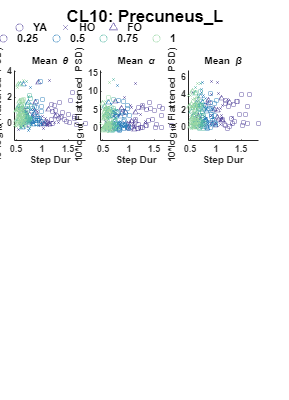

##10-theta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                     0.51925         2      0.25962      0.44007    0.64455
    mean_UDexc_COV                  1.1376         1       1.1376       1.9282    0.16635
    group_char:mean_UDexc_COV      0.36842         2      0.18421      0.31224    0.73213
    Error                           130.97       222      0.58997                        
    Total                           133.22       227                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                          Estimate        SE        tStat        pValue  
                                         __________    ________    ________    __________

    (Intercept)                             0.76495     0.19974      3.8298    0.00016689
    group_char_H2000's                     -0.11618      0.3033    -0.38305       0.70205
    group_char_H3000's                      0.20914     0.33036     0.63307       0.52734
    mean_UDexc_COV                        -0.006281    0.014291    -0.43952       0.66072
    group_char_H2000's:mean_UDexc_COV    -0.0022297    0.021125    -0.10555       0.91604
    group_char_H3000's:mean_UDexc_COV<

##10-alpha_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      7.1896         2      3.5948       0.54282    0.58188
    mean_UDexc_COV                  9.7625         1      9.7625        1.4741    0.22598
    group_char:mean_UDexc_COV       7.0281         2       3.514       0.53062    0.58898
    Error                           1470.2       222      6.6225                         
    Total                           1504.6       227                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                              2.326      0.6692      3.4758    0.00061245
    group_char_H2000's                      1.0222      1.0162      1.0059       0.31555
    group_char_H3000's                     0.71905      1.1068     0.64965       0.51659
    mean_UDexc_COV                       0.0032289    0.047879    0.067438       0.94629
    group_char_H2000's:mean_UDexc_COV    -0.045314    0.070777    -0.64024       0.52267
    group_char_H3000's:mean_UDexc_COV

##10-beta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                       8.871         2       4.4355       2.4815    0.085931
    mean_UDexc_COV                  1.0165         1       1.0165      0.56871     0.45157
    group_char:mean_UDexc_COV       1.8191         2      0.90955      0.50887     0.60187
    Error                            396.8       222       1.7874                         
    Total                           421.49       227                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue  
                                         _________    ________    _______    __________

    (Intercept)                             1.3595     0.34766     3.9104    0.00012244
    group_char_H2000's                      1.1395     0.52792     2.1585       0.03196
    group_char_H3000's                     0.20341     0.57501    0.35376       0.72386
    mean_UDexc_COV                       0.0069316    0.024874    0.27867       0.78076
    group_char_H2000's:mean_UDexc_COV    -0.036974     0.03677    -1.0056       0.31573
    group_char_H3000's:mean_UDexc_COV    -0.

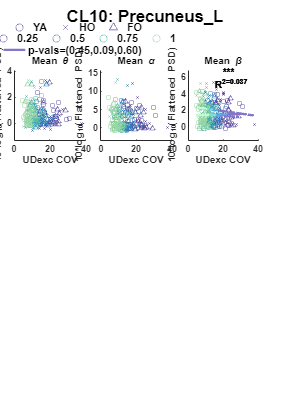

##10-theta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares      F       pValue 
                                  ____________    ___    ___________    ______    _______

    group_char                       3.0548         2       1.5274      2.6292    0.07438
    mean_UDexc_mean                  1.0478         1       1.0478      1.8037    0.18064
    group_char:mean_UDexc_mean       2.2695         2       1.1347      1.9533    0.14423
    Error                            128.97       222      0.58093                       
    Total                            133.22       227                                    



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                            0.81804    0.23641      3.4602    0.00064709
    group_char_H2000's                    -0.77247    0.33728     -2.2903      0.022943
    group_char_H3000's                      -0.345    0.34569      -0.998       0.31936
    mean_UDexc_mean                        -5.5811     9.3073    -0.59965       0.54935
    group_char_H2000's:mean_UDexc_mean      25.854     13.089      1.9752      0.049484
    group_char_H3000's:mean_UDexc_mean    

##10-alpha_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                       5.0214         2      2.5107       0.37766     0.6859
    mean_UDexc_mean                  1.7266         1      1.7266       0.25971    0.61083
    group_char:mean_UDexc_mean       7.3023         2      3.6511        0.5492    0.57819
    Error                            1475.9       222      6.6481                         
    Total                            1504.6       227                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue 
                                          ________    _______    ________    ________

    (Intercept)                            1.6133     0.79976      2.0172    0.044876
    group_char_H2000's                     0.9214       1.141     0.80755     0.42022
    group_char_H3000's                    0.78237      1.1694     0.66903     0.50417
    mean_UDexc_mean                         31.52      31.485      1.0011     0.31786
    group_char_H2000's:mean_UDexc_mean    -21.167      44.279    -0.47805     0.63309
    group_char_H3000's:mean_UDexc_mean    -45.954      4

##10-beta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    _______    ________

    group_char                       12.398         2       6.1992       3.5121    0.031501
    mean_UDexc_mean                 0.28585         1      0.28585      0.16195     0.68776
    group_char:mean_UDexc_mean       7.2663         2       3.6331       2.0583      0.1301
    Error                            391.85       222       1.7651                         
    Total                            421.49       227                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat      pValue  
                                          ________    _______    _______    _________

    (Intercept)                           0.90369     0.41209     2.1929      0.02935
    group_char_H2000's                     1.5364     0.58791     2.6133    0.0095793
    group_char_H3000's                    0.98823     0.60257       1.64      0.10241
    mean_UDexc_mean                        22.763      16.224     1.4031      0.16199
    group_char_H2000's:mean_UDexc_mean    -36.996      22.816    -1.6215      0.10633
    group_char_H3000's:mean_UDexc_mean    -42.457      22

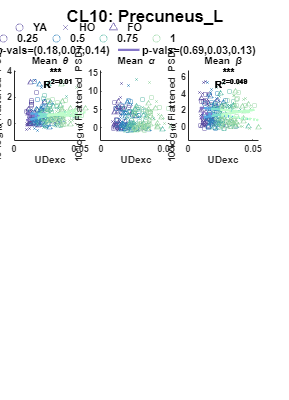

##10-theta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                     0.61566         2      0.30783      0.52251    0.59376
    mean_StanceDur                  1.3524         1       1.3524       2.2955    0.13117
    group_char:mean_StanceDur      0.94361         2       0.4718      0.80084    0.45024
    Error                           130.79       222      0.58914                        
    Total                           133.22       227                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate       SE        tStat        pValue  
                                         _________    _______    ________    __________

    (Intercept)                            0.71125    0.20347      3.4957    0.00057091
    group_char_H2000's                    0.015785    0.34855    0.045287       0.96392
    group_char_H3000's                     0.37368    0.37969     0.98418        0.3261
    mean_StanceDur                       -0.021543    0.15083    -0.14282       0.88656
    group_char_H2000's:mean_StanceDur     -0.16663    0.30196    -0.55182       0.58163
    group_char_H3000's:mean_StanceDur     -

##10-alpha_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    group_char                     0.69787         2      0.34894      0.052275    0.94908
    mean_StanceDur                  1.9728         1       1.9728       0.29555    0.58723
    group_char:mean_StanceDur      0.42602         2      0.21301      0.031911     0.9686
    Error                           1481.9       222       6.6751                         
    Total                           1504.6       227                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate       SE         tStat       pValue  
                                         _________    _______    _________    _________

    (Intercept)                             2.1178    0.68487       3.0922    0.0022413
    group_char_H2000's                     0.21533     1.1732      0.18354      0.85454
    group_char_H3000's                    -0.24977     1.2781     -0.19543      0.84524
    mean_StanceDur                         0.20124    0.50771      0.39636      0.69222
    group_char_H2000's:mean_StanceDur      0.24059     1.0164      0.23671       0.8131
    group_char_H3000's:mean_StanceDur    -0

##10-beta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      5.8279         2       2.9139       1.6243    0.19938
    mean_StanceDur                 0.28712         1      0.28712      0.16005    0.68949
    group_char:mean_StanceDur       0.9801         2      0.49005      0.27317    0.76122
    Error                           398.26       222       1.7939                        
    Total                           421.49       227                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate      SE        tStat       pValue  
                                         ________    _______    _______    __________

    (Intercept)                             1.346    0.35505     3.7911    0.00019327
    group_char_H2000's                    0.90699    0.60822     1.4912       0.13733
    group_char_H3000's                   -0.32803    0.66256    -0.4951       0.62102
    mean_StanceDur                       0.082415    0.26321    0.31312       0.75449
    group_char_H2000's:mean_StanceDur    -0.23548    0.52692    -0.4469       0.65538
    group_char_H3000's:mean_StanceDur      0.2943    0.613

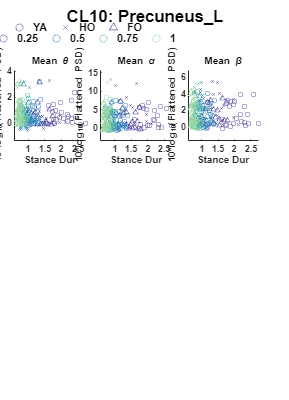

##10-theta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F       pValue 
                                    ____________    ___    ___________    _______    _______

    group_char                        0.72186         2      0.36093      0.61293    0.54267
    mean_GaitCycleDur                  1.3413         1       1.3413       2.2778    0.13266
    group_char:mean_GaitCycleDur       1.0038         2      0.50191      0.85235     0.4278
    Error                              130.73       222      0.58886                        
    Total                              133.22       227                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate       SE        tStat       pValue  
                                            _________    _______    ________    _________

    (Intercept)                               0.72031    0.24316      2.9623    0.0033858
    group_char_H2000's                        0.02264    0.42438    0.053348       0.9575
    group_char_H3000's                        0.48165    0.45087      1.0683      0.28656
    mean_GaitCycleDur                       -0.019602    0.12578    -0.15584       0.8763
    group_char_H2000's:mean_GaitCycleDur     -0.11891    0.25601    -0.46446      0.64277
    group_char_H3000's:mean_GaitCyc

##10-alpha_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F        pValue 
                                    ____________    ___    ___________    ________    _______

    group_char                        0.13811         2     0.069056       0.01035     0.9897
    mean_GaitCycleDur                   1.763         1        1.763       0.26424    0.60774
    group_char:mean_GaitCycleDur      0.73882         2      0.36941      0.055367    0.94615
    Error                              1481.2       222        6.672                         
    Total                              1504.6       227                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate       SE         tStat       pValue 
                                            _________    _______    _________    ________

    (Intercept)                                1.9837    0.81849       2.4237    0.016166
    group_char_H2000's                        0.19795     1.4285      0.13857     0.88991
    group_char_H3000's                      0.0091237     1.5177    0.0060116     0.99521
    mean_GaitCycleDur                         0.21014    0.42339      0.49632     0.62016
    group_char_H2000's:mean_GaitCycleDur      0.19098    0.86176      0.22161     0.82482
    group_char_H3000's:mean_GaitCyc

##10-beta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F       pValue 
                                    ____________    ___    ___________    _______    _______

    group_char                          5.543         2       2.7715       1.5477    0.21502
    mean_GaitCycleDur                 0.50787         1      0.50787      0.28361    0.59488
    group_char:mean_GaitCycleDur       1.4478         2      0.72392      0.40426    0.66796
    Error                              397.54       222       1.7907                        
    Total                              421.49       227                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate      SE        tStat       pValue  
                                            ________    _______    ________    _________

    (Intercept)                               1.2732    0.42403      3.0026    0.0029835
    group_char_H2000's                        1.0441    0.74005      1.4108       0.1597
    group_char_H3000's                      -0.44326    0.78625    -0.56377      0.57348
    mean_GaitCycleDur                       0.095887    0.21934     0.43715      0.66243
    group_char_H2000's:mean_GaitCycleDur     -0.2427    0.44645    -0.54361      0.58725
    group_char_H3000's:mean_GaitCycleDur

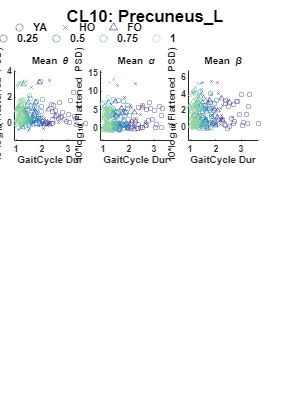

##10-theta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F       pValue 
                                          ____________    ___    ___________    _______    _______

    group_char                               1.7558         2       0.8779       1.5008    0.22519
    mean_PeakUpDownVel_mean                  1.3313         1       1.3313       2.2759    0.13282
    group_char:mean_PeakUpDownVel_mean       1.0877         2      0.54383      0.92972    0.39619
    Error                                    129.86       222      0.58493                        
    Total                                    133.22       227                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat        pValue  
                                                  ________    _______    ________    __________

    (Intercept)                                    0.72767    0.19295      3.7713    0.00020832
    group_char_H2000's                            -0.46166    0.28382     -1.6266       0.10525
    group_char_H3000's                            -0.37037    0.29402     -1.2597       0.20911
    mean_PeakUpDownVel_mean                        -0.1819    0.74079    -0.24555       0.80625
    group_char_H2000's:mean_PeakUpDownVel_mean      1.2198     1.0328      1.1811       0.2

##10-alpha_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares        F        pValue 
                                          ____________    ___    ___________    _________    _______

    group_char                                6.5022        2       3.2511        0.48642    0.61548
    mean_PeakUpDownVel_mean                 0.044956        1     0.044956      0.0067262    0.93471
    group_char:mean_PeakUpDownVel_mean       0.90076        2      0.45038       0.067385    0.93485
    Error                                     1483.8      222       6.6837                          
    Total                                     1504.6      227                                       



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat        pValue  
                                                  ________    _______    ________    __________

    (Intercept)                                     2.2496    0.65224      3.4491    0.00067297
    group_char_H2000's                             0.73709    0.95941     0.76827       0.44314
    group_char_H3000's                            -0.20953    0.99387    -0.21082       0.83322
    mean_PeakUpDownVel_mean                        0.49637     2.5041     0.19822       0.84305
    group_char_H2000's:mean_PeakUpDownVel_mean     -1.2772      3.491    -0.36584       0.7

##10-beta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F       pValue 
                                          ____________    ___    ___________    _______    _______

    group_char                                6.835         2      3.4175        1.9068    0.15098
    mean_PeakUpDownVel_mean                  0.5548         1      0.5548       0.30956    0.57851
    group_char:mean_PeakUpDownVel_mean       1.0028         2      0.5014       0.27976    0.75623
    Error                                    397.88       222      1.7923                         
    Total                                    421.49       227                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat        pValue  
                                                  ________    _______    ________    __________

    (Intercept)                                    1.3592     0.33775      4.0242    7.8421e-05
    group_char_H2000's                            0.94687     0.49682      1.9059       0.05796
    group_char_H3000's                            0.24147     0.51466     0.46919       0.63939
    mean_PeakUpDownVel_mean                        0.3755      1.2967     0.28958       0.77241
    group_char_H2000's:mean_PeakUpDownVel_mean    -1.1842      1.8078    -0.65504       0.51

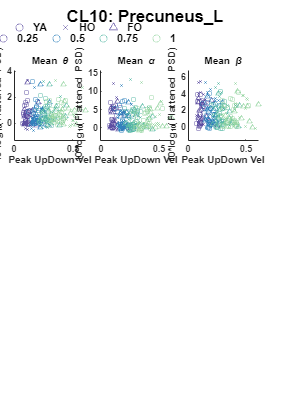

##11-theta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares      F        pValue 
                                 ____________    ___    ___________    ______    ________

    group_char                      1.6675         2      0.83377      2.9605    0.053643
    mean_APexc_COV                 0.75771         1      0.75771      2.6904     0.10223
    group_char:mean_APexc_COV      0.64944         2      0.32472       1.153     0.31739
    Error                           69.282       246      0.28163                        
    Total                           76.488       251                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat      pValue  
                                         _________    ________    _______    _________

    (Intercept)                            0.69399     0.20753      3.344    0.0009547
    group_char_H2000's                    -0.55083      0.3714    -1.4831      0.13932
    group_char_H3000's                     0.39718     0.31703     1.2528      0.21146
    mean_APexc_COV                       -0.020995    0.012694    -1.6539     0.099425
    group_char_H2000's:mean_APexc_COV     0.025917    0.019195     1.3502      0.17819
    group_char_H3000's:mean_APexc_COV    0.0020899

##11-alpha_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares      F        pValue 
                                 ____________    ___    ___________    ______    ________

    group_char                      42.923         2      21.462       3.9255    0.020981
    mean_APexc_COV                  23.925         1      23.925       4.3761    0.037471
    group_char:mean_APexc_COV       41.224         2      20.612       3.7701    0.024392
    Error                           1344.9       246      5.4672                         
    Total                           1418.1       251                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             3.1892     0.91439      3.4878    0.00057671
    group_char_H2000's                      3.6051      1.6364      2.2031      0.028514
    group_char_H3000's                     -1.1249      1.3968    -0.80537       0.42139
    mean_APexc_COV                       -0.012692    0.055931    -0.22692       0.82068
    group_char_H2000's:mean_APexc_COV     -0.18063    0.084572     -2.1359      0.033679
    group_char_H3000's:mean_APexc_COV

##11-beta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares      F         pValue  
                                 ____________    ___    ___________    ______    __________

    group_char                      22.081         2      11.041       7.8334    0.00050344
    mean_APexc_COV                  6.3222         1      6.3222       4.4856      0.035184
    group_char:mean_APexc_COV       15.342         2      7.6711       5.4427     0.0048649
    Error                           346.72       246      1.4094                           
    Total                            382.5       251                                       



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             1.6055     0.46427      3.4581    0.00064098
    group_char_H2000's                      2.6051     0.83084      3.1355     0.0019239
    group_char_H3000's                    -0.78096     0.70921     -1.1012        0.2719
    mean_APexc_COV                       -0.003481    0.028398    -0.12258       0.90254
    group_char_H2000's:mean_APexc_COV     -0.10752     0.04294     -2.5038      0.012935
    group_char_H3000's:mean_APexc_COV

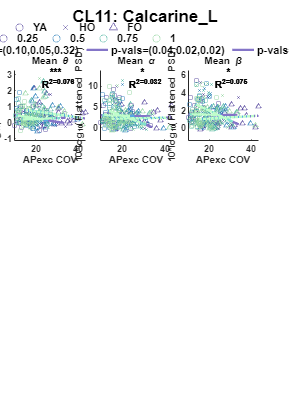

##11-theta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares       F         pValue 
                                  ____________    ___    ___________    ________    ________

    group_char                        2.5214        2        1.2607       4.4042    0.013205
    mean_APexc_mean                0.0087638        1     0.0087638     0.030615     0.86125
    group_char:mean_APexc_mean       0.79497        2       0.39748       1.3886     0.25138
    Error                             70.419      246       0.28626                         
    Total                             76.488      251                                       



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue 
                                          ________    _______    ________    ________

    (Intercept)                            0.42847    0.18131      2.3632    0.018897
    group_char_H2000's                    -0.39893     0.2725      -1.464     0.14448
    group_char_H3000's                     0.38294    0.24805      1.5438     0.12393
    mean_APexc_mean                        -1.2449     3.1967    -0.38942      0.6973
    group_char_H2000's:mean_APexc_mean      5.9958     5.2807      1.1354      0.2573
    group_char_H3000's:mean_APexc_mean     -3.4016     4

##11-alpha_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    _______    ________

    group_char                       35.933         2      17.967        3.2289    0.041285
    mean_APexc_mean                  3.6165         1      3.6165       0.64996     0.42091
    group_char:mean_APexc_mean       24.493         2      12.246        2.2009     0.11288
    Error                            1368.8       246      5.5643                          
    Total                            1418.1       251                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                             3.579     0.79938      4.4773    1.1573e-05
    group_char_H2000's                     0.6398      1.2014     0.53255       0.59483
    group_char_H3000's                    -2.0911      1.0936     -1.9121      0.057022
    mean_APexc_mean                       -10.842      14.094    -0.76924       0.44249
    group_char_H2000's:mean_APexc_mean    -21.156      23.282     -0.9087        0.3644
    group_char_H3000's:mean_APexc_mean    

##11-beta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    _______    ________

    group_char                       13.607         2       6.8037       4.6696    0.010222
    mean_APexc_mean                 0.47418         1      0.47418      0.32545     0.56887
    group_char:mean_APexc_mean       5.4013         2       2.7006       1.8536     0.15886
    Error                            358.42       246        1.457                         
    Total                             382.5       251                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                             1.6375    0.40905      4.0032    8.2778e-05
    group_char_H2000's                     0.97386    0.61477      1.5841       0.11445
    group_char_H3000's                    -0.84675    0.55962     -1.5131       0.13155
    mean_APexc_mean                        -1.6008      7.212    -0.22196       0.82453
    group_char_H2000's:mean_APexc_mean     -14.122     11.914     -1.1854       0.23702
    group_char_H3000's:mean_APexc_mean     

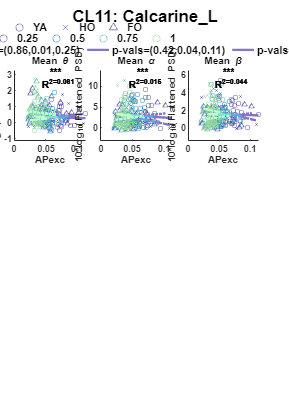

##11-theta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                      1.4715         2      0.73577       2.5645    0.079014
    mean_MLexc_COV                 0.38137         1      0.38137       1.3293     0.25006
    group_char:mean_MLexc_COV      0.27947         2      0.13974      0.48705     0.61503
    Error                           70.579       246      0.28691                         
    Total                           76.488       251                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                          Estimate        SE         tStat       pValue 
                                         __________    _________    ________    ________

    (Intercept)                             0.26336      0.14676      1.7945    0.073967
    group_char_H2000's                     -0.27146      0.24743     -1.0971     0.27366
    group_char_H3000's                      0.36188      0.24673      1.4667     0.14373
    mean_MLexc_COV                        0.0067241    0.0095514       0.704      0.4821
    group_char_H2000's:mean_MLexc_COV      0.010725     0.016002     0.67027     0.50332
    group_char_H3000's:mean_MLexc_COV

##11-alpha_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares      F        pValue 
                                 ____________    ___    ___________    ______    ________

    group_char                      36.663         2      18.332       3.4037    0.034824
    mean_MLexc_COV                  34.345         1      34.345       6.3769    0.012191
    group_char:mean_MLexc_COV       24.102         2      12.051       2.2376     0.10889
    Error                           1324.9       246      5.3858                         
    Total                           1418.1       251                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                          Estimate        SE         tStat       pValue  
                                         __________    ________    _________    _________

    (Intercept)                              4.6773     0.63587       7.3557    2.822e-12
    group_char_H2000's                      -0.0734       1.072    -0.068468      0.94547
    group_char_H3000's                      -2.6346       1.069      -2.4646       0.0144
    mean_MLexc_COV                         -0.11688    0.041383      -2.8243    0.0051269
    group_char_H2000's:mean_MLexc_COV    -0.0096831    0.069329     -0.13967      0.88904
    group_char_H3000's:mean_MLexc_COV<

##11-beta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares      F        pValue 
                                 ____________    ___    ___________    ______    ________

    group_char                      11.177         2      5.5887       3.8967    0.021574
    mean_MLexc_COV                  6.9478         1      6.9478       4.8444    0.028666
    group_char:mean_MLexc_COV       4.3524         2      2.1762       1.5174     0.22133
    Error                           352.81       246      1.4342                         
    Total                            382.5       251                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue  
                                         _________    ________    _______    __________

    (Intercept)                             1.9267     0.32813     5.8717    1.3904e-08
    group_char_H2000's                      1.0213      0.5532     1.8461      0.066077
    group_char_H3000's                    -0.72157     0.55163    -1.3081       0.19207
    mean_MLexc_COV                       -0.026045    0.021355    -1.2196       0.22378
    group_char_H2000's:mean_MLexc_COV    -0.046273    0.035776    -1.2934       0.19709
    group_char_H3000's:mean_MLexc_COV     0.

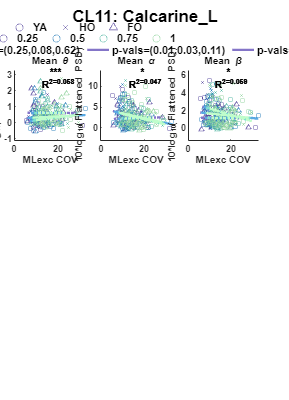

##11-theta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                        1.3005        2      0.65025       2.2507    0.10749
    mean_MLexc_mean                 0.038465        1     0.038465      0.13314    0.71552
    group_char:mean_MLexc_mean       0.13718        2     0.068591      0.23741    0.78885
    Error                             71.073      246      0.28891                        
    Total                             76.488      251                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                            0.43801    0.15466      2.8321    0.0050073
    group_char_H2000's                    -0.24679    0.23041     -1.0711      0.28519
    group_char_H3000's                     0.25041    0.22307      1.1226      0.26271
    mean_MLexc_mean                        -0.9721     1.8375    -0.52903      0.59726
    group_char_H2000's:mean_MLexc_mean      1.6092     2.5872     0.62199      0.53452
    group_char_H3000's:mean_MLexc_mean     0.1732

##11-alpha_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F         pValue 
                                  ____________    ___    ___________    ________    ________

    group_char                       28.756         2       14.378         2.582    0.077674
    mean_MLexc_mean                 0.22823         1      0.22823      0.040984     0.83974
    group_char:mean_MLexc_mean       26.276         2       13.138        2.3593     0.09662
    Error                            1369.9       246       5.5687                          
    Total                            1418.1       251                                       



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                             2.5483    0.67899      3.7531    0.00021795
    group_char_H2000's                      1.4946     1.0116      1.4775       0.14083
    group_char_H3000's                    -0.82323    0.97933    -0.84061       0.40139
    mean_MLexc_mean                         5.5148     8.0673      0.6836       0.49487
    group_char_H2000's:mean_MLexc_mean     -20.461     11.359     -1.8013      0.072876
    group_char_H3000's:mean_MLexc_mean    

##11-beta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    _______    ________

    group_char                       12.188         2      6.0939        4.1753    0.016474
    mean_MLexc_mean                  1.0979         1      1.0979       0.75226     0.38661
    group_char:mean_MLexc_mean        4.065         2      2.0325        1.3926     0.25039
    Error                            359.04       246      1.4595                          
    Total                             382.5       251                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE         tStat        pValue  
                                          ________    _______    _________    __________

    (Intercept)                             1.5795    0.34761       4.5438    8.6643e-06
    group_char_H2000's                     0.94809    0.51788       1.8307      0.068353
    group_char_H3000's                    -0.56505    0.50137       -1.127       0.26084
    mean_MLexc_mean                       -0.36776     4.1301    -0.089044       0.92912
    group_char_H2000's:mean_MLexc_mean     -7.0072     5.8151       -1.205       0.22936
    group_char_H3000's:mean_MLexc_mean

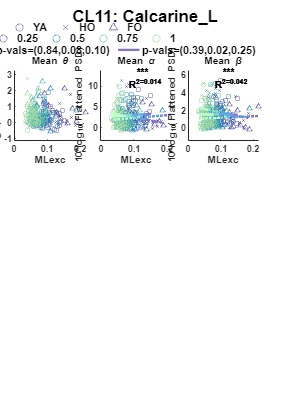

##11-theta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F       pValue 
                               ____________    ___    ___________    _______    _______

    group_char                    0.98742        2      0.49371       1.7103    0.18296
    mean_StepDur                 0.022263        1     0.022263      0.07712    0.78147
    group_char:mean_StepDur       0.19335        2     0.096675      0.33489    0.71574
    Error                          71.014      246      0.28867                        
    Total                          76.488      251                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate       SE        tStat       pValue  
                                       _________    _______    ________    _________

    (Intercept)                          0.42606    0.15209      2.8015    0.0054917
    group_char_H2000's                  -0.29364    0.28474     -1.0313      0.30343
    group_char_H3000's                   0.33598    0.28522       1.178      0.23994
    mean_StepDur                       -0.072147    0.15826    -0.45587      0.64889
    group_char_H2000's:mean_StepDur      0.21845     0.3369     0.64841      0.51733
    group_char_H3000's:mean_StepDur     -0.13462    0.37361    -0.

##11-alpha_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F       pValue 
                               ____________    ___    ___________    _______    _______

    group_char                     6.723         2      3.3615        0.5949    0.55241
    mean_StepDur                  3.5088         1      3.5088       0.62097    0.43145
    group_char:mean_StepDur       2.8953         2      1.4477        0.2562    0.77419
    Error                           1390       246      5.6505                         
    Total                         1418.1       251                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate      SE        tStat        pValue  
                                       ________    _______    ________    __________

    (Intercept)                          2.6357    0.67286      3.9172    0.00011613
    group_char_H2000's                  0.17497     1.2598     0.13889       0.88965
    group_char_H3000's                  -1.2588     1.2619    -0.99754       0.31948
    mean_StepDur                        0.38769    0.70019      0.5537       0.58029
    group_char_H2000's:mean_StepDur    -0.45016     1.4905    -0.30202        0.7629
    group_char_H3000's:mean_StepDur     0.95194     1.6529     0.5

##11-beta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares        F        pValue 
                               ____________    ___    ___________    _________    _______

    group_char                     3.8021        2        1.901         1.2876    0.27778
    mean_StepDur                 0.011992        1     0.011992      0.0081226    0.92826
    group_char:mean_StepDur       0.78186        2      0.39093        0.26479    0.76759
    Error                          363.19      246       1.4764                          
    Total                           382.5      251                                       



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate      SE        tStat        pValue  
                                       ________    _______    ________    __________

    (Intercept)                          1.4202    0.34394      4.1292    4.9887e-05
    group_char_H2000's                  0.74798    0.64395      1.1616       0.24654
    group_char_H3000's                 -0.47125    0.64502    -0.73059       0.46573
    mean_StepDur                        0.14317    0.35791     0.40001        0.6895
    group_char_H2000's:mean_StepDur    -0.49482     0.7619    -0.64945       0.51665
    group_char_H3000's:mean_StepDur     0.16265    0.84491     0.19

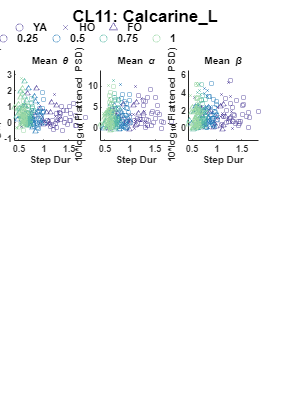

##11-theta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                       1.242         2      0.62098       2.1839    0.11478
    mean_UDexc_COV                 0.76285         1      0.76285       2.6828    0.10271
    group_char:mean_UDexc_COV      0.31368         2      0.15684      0.55158    0.57675
    Error                           69.949       246      0.28435                        
    Total                           76.488       251                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                         Estimate        SE         tStat       pValue  
                                         _________    _________    _______    __________

    (Intercept)                            0.57848      0.12574     4.6007    6.7444e-06
    group_char_H2000's                    -0.30732      0.21493    -1.4299       0.15402
    group_char_H3000's                     0.21104      0.22012    0.95877       0.33862
    mean_UDexc_COV                       -0.017317    0.0091844    -1.8854      0.060549
    group_char_H2000's:mean_UDexc_COV     0.015488     0.014755     1.0497       0.29487
    group_char_H3000's:mean_UDexc_COV

##11-alpha_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      13.365         2      6.6825          1.19    0.30596
    mean_UDexc_COV                  5.7794         1      5.7794        1.0292    0.31135
    group_char:mean_UDexc_COV       5.7973         2      2.8986       0.51619    0.59744
    Error                           1381.4       246      5.6155                         
    Total                           1418.1       251                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             3.8033     0.55877      6.8065    7.5862e-11
    group_char_H2000's                     -0.7891     0.95513    -0.82617       0.40951
    group_char_H3000's                     -1.4713      0.9782     -1.5041       0.13385
    mean_UDexc_COV                       -0.064812    0.040815     -1.5879       0.11358
    group_char_H2000's:mean_UDexc_COV     0.046647    0.065569     0.71141        0.4775
    group_char_H3000's:mean_UDexc_COV

##11-beta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares      F        pValue 
                                 ____________    ___    ___________    ______    ________

    group_char                      7.4356         2       3.7178      2.5415    0.080818
    mean_UDexc_COV                   1.698         1        1.698      1.1608     0.28236
    group_char:mean_UDexc_COV       1.9041         2      0.95203      0.6508     0.52252
    Error                           359.86       246       1.4629                        
    Total                            382.5       251                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                         Estimate        SE         tStat        pValue  
                                         _________    ________    _________    __________

    (Intercept)                             1.8812     0.28519       6.5961    2.5643e-10
    group_char_H2000's                     0.40885     0.48749      0.83868       0.40246
    group_char_H3000's                    -0.84483     0.49927      -1.6922      0.091883
    mean_UDexc_COV                         -0.0263    0.020832      -1.2625       0.20797
    group_char_H2000's:mean_UDexc_COV    -0.002137    0.033466    -0.063855       0.94914
    group_char_H3000's:mean_UDexc_COV</

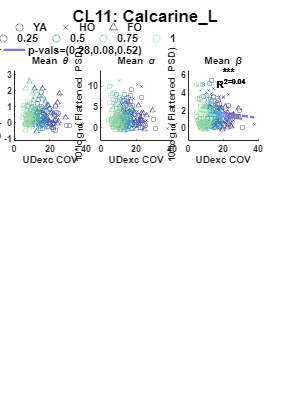

##11-theta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    _______    ________

    group_char                        2.2835        2       1.1418       3.9752    0.019993
    mean_UDexc_mean                 0.073411        1     0.073411      0.25559     0.61362
    group_char:mean_UDexc_mean       0.57698        2      0.28849       1.0044     0.36775
    Error                             70.656      246      0.28722                         
    Total                             76.488      251                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue 
                                          ________    _______    ________    ________

    (Intercept)                             0.3378    0.14942      2.2607    0.024652
    group_char_H2000's                    -0.31045    0.24274     -1.2789     0.20212
    group_char_H3000's                     0.39668    0.22439      1.7678    0.078329
    mean_UDexc_mean                        0.95814     5.9294     0.16159     0.87176
    group_char_H2000's:mean_UDexc_mean      8.5376     9.7597     0.87478     0.38255
    group_char_H3000's:mean_UDexc_mean     -5.5583     8

##11-alpha_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                       4.6977         2       2.3488      0.41811    0.65876
    mean_UDexc_mean                  14.062         1       14.062       2.5031    0.11491
    group_char:mean_UDexc_mean        1.198         2      0.59902      0.10663     0.8989
    Error                              1382       246       5.6178                        
    Total                            1418.1       251                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                              3.552    0.66083      5.3751    1.7768e-07
    group_char_H2000's                    0.099061     1.0735    0.092277       0.92655
    group_char_H3000's                    -0.78596    0.99237      -0.792       0.42912
    mean_UDexc_mean                         -23.75     26.223    -0.90568       0.36599
    group_char_H2000's:mean_UDexc_mean     -14.883     43.163    -0.34481       0.73053
    group_char_H3000's:mean_UDexc_mean    

##11-beta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    ________    _______

    group_char                       1.9753         2      0.98764       0.67168    0.51178
    mean_UDexc_mean                  1.9633         1       1.9633        1.3352      0.249
    group_char:mean_UDexc_mean      0.08379         2     0.041895      0.028492    0.97191
    Error                            361.72       246       1.4704                         
    Total                             382.5       251                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                            1.8472     0.33809      5.4637    1.141e-07
    group_char_H2000's                    0.21474     0.54922     0.39099      0.69614
    group_char_H3000's                    -0.4239      0.5077    -0.83494      0.40456
    mean_UDexc_mean                         -12.5      13.416    -0.93171       0.3524
    group_char_H2000's:mean_UDexc_mean     5.2714      22.083     0.23871      0.81153
    group_char_H3000's:mean_UDexc_mean     1.9552 

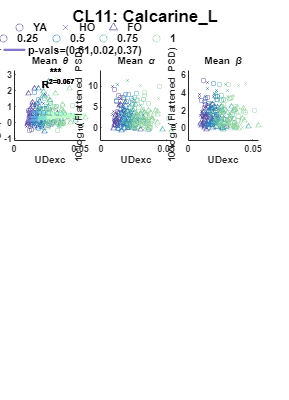

##11-theta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                      1.3588         2       0.6794       2.3559    0.096942
    mean_StanceDur                 0.04403         1      0.04403      0.15268     0.69633
    group_char:mean_StanceDur      0.24598         2      0.12299      0.42648     0.65328
    Error                           70.942       246      0.28838                         
    Total                           76.488       251                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue  
                                         _________    ________    ________    _________

    (Intercept)                            0.41977     0.12754      3.2912    0.0011438
    group_char_H2000's                    -0.26758     0.23439     -1.1416      0.25472
    group_char_H3000's                     0.34465     0.23985      1.4369      0.15201
    mean_StanceDur                       -0.047843    0.094869    -0.50431       0.6145
    group_char_H2000's:mean_StanceDur      0.13756     0.20024     0.68698      0.49274
    group_char_H3000's:mean_StanceDur     -

##11-alpha_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      7.2672         2      3.6336       0.64325    0.52646
    mean_StanceDur                  3.4955         1      3.4955       0.61882    0.43224
    group_char:mean_StanceDur       2.8345         2      1.4172       0.25089     0.7783
    Error                           1389.6       246      5.6488                         
    Total                           1418.1       251                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate      SE        tStat        pValue  
                                         ________    _______    ________    __________

    (Intercept)                            2.6457    0.56448      4.6869    4.5954e-06
    group_char_H2000's                    0.18219     1.0374     0.17562       0.86073
    group_char_H3000's                    -1.0847     1.0615     -1.0218       0.30787
    mean_StanceDur                        0.27638    0.41987     0.65825       0.51099
    group_char_H2000's:mean_StanceDur    -0.33923    0.88624    -0.38277       0.70222
    group_char_H3000's:mean_StanceDur     0.50986 

##11-beta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares        F        pValue 
                                 ____________    ___    ___________    _________    _______

    group_char                       4.3526        2        2.1763        1.4742    0.23098
    mean_StanceDur                0.0026922        1     0.0026922     0.0018237    0.96597
    group_char:mean_StanceDur       0.82426        2       0.41213       0.27917    0.75665
    Error                            363.16      246        1.4763                         
    Total                             382.5      251                                       



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate      SE        tStat        pValue  
                                         ________    _______    ________    __________

    (Intercept)                            1.4151    0.28857       4.904    1.7077e-06
    group_char_H2000's                     0.7161    0.53032      1.3503       0.17815
    group_char_H3000's                   -0.33895    0.54268    -0.62458       0.53283
    mean_StanceDur                        0.10914    0.21465     0.50845       0.61159
    group_char_H2000's:mean_StanceDur     -0.3349    0.45306    -0.73919       0.46049
    group_char_H3000's:mean_StanceDur    -0.02026  

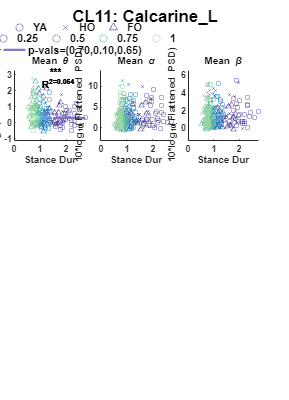

##11-theta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F        pValue 
                                    ____________    ___    ___________    ________    _______

    group_char                         0.99349        2      0.49675        1.7208    0.18107
    mean_GaitCycleDur                 0.019131        1     0.019131      0.066271    0.79706
    group_char:mean_GaitCycleDur       0.19762        2     0.098808       0.34229    0.71048
    Error                               71.013      246      0.28867                         
    Total                               76.488      251                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate        SE        tStat       pValue  
                                            _________    ________    ________    _________

    (Intercept)                               0.42586     0.15199      2.8019    0.0054841
    group_char_H2000's                        -0.2975     0.28395     -1.0477      0.29579
    group_char_H3000's                        0.33303     0.28506      1.1683      0.24382
    mean_GaitCycleDur                       -0.035942    0.079036    -0.45476      0.64968
    group_char_H2000's:mean_GaitCycleDur      0.11164     0.16776      0.6655      0.50636
    group_char_H3000's:mean_

##11-alpha_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F       pValue 
                                    ____________    ___    ___________    _______    _______

    group_char                         6.8142         2      3.4071         0.603    0.54798
    mean_GaitCycleDur                  3.4706         1      3.4706       0.61424    0.43395
    group_char:mean_GaitCycleDur       2.9813         2      1.4907       0.26382    0.76833
    Error                                1390       246      5.6503                         
    Total                              1418.1       251                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate      SE        tStat        pValue  
                                            ________    _______    ________    __________

    (Intercept)                               2.6347    0.67242      3.9182    0.00011564
    group_char_H2000's                       0.18973     1.2562     0.15103       0.88007
    group_char_H3000's                       -1.2604     1.2611     -0.9994       0.31858
    mean_GaitCycleDur                        0.19432    0.34967     0.55573        0.5789
    group_char_H2000's:mean_GaitCycleDur    -0.23437    0.74221    -0.31578       0.75244
    group_char_H3000's:mean_GaitCyc

##11-beta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares        F        pValue 
                                    ____________    ___    ___________    _________    _______

    group_char                          3.8466        2       1.9233         1.3028    0.27365
    mean_GaitCycleDur                 0.010553        1     0.010553      0.0071483    0.93269
    group_char:mean_GaitCycleDur       0.80125        2      0.40063        0.27137    0.76257
    Error                               363.18      246       1.4763                          
    Total                                382.5      251                                       



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate      SE        tStat        pValue  
                                            ________    _______    ________    __________

    (Intercept)                               1.4202    0.34371       4.132    4.9335e-05
    group_char_H2000's                       0.75226    0.64214      1.1715       0.24254
    group_char_H3000's                      -0.47057    0.64465    -0.72997        0.4661
    mean_GaitCycleDur                       0.071554    0.17874     0.40033       0.68926
    group_char_H2000's:mean_GaitCycleDur    -0.24996    0.37939    -0.65886        0.5106
    group_char_H3000's:mean_GaitCycl

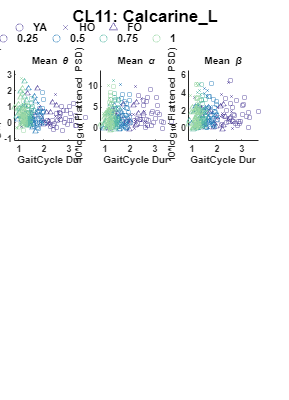

##11-theta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F        pValue 
                                          ____________    ___    ___________    _______    ________

    group_char                                1.3681        2      0.68404       2.3692    0.095688
    mean_PeakUpDownVel_mean                   0.1533        1       0.1533      0.53095      0.4669
    group_char:mean_PeakUpDownVel_mean      0.075629        2     0.037814      0.13097      0.8773
    Error                                     71.026      246      0.28872                         
    Total                                     76.488      251                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat       pValue 
                                                  ________    _______    ________    ________

    (Intercept)                                    0.29319    0.12064      2.4303      0.0158
    group_char_H2000's                             -0.1414    0.20308    -0.69629     0.48691
    group_char_H3000's                             0.32501     0.1954      1.6633    0.097522
    mean_PeakUpDownVel_mean                        0.28548    0.46542     0.61338     0.54019
    group_char_H2000's:mean_PeakUpDownVel_mean     0.10115    0.76586     0.13208     0.89503
    

##11-alpha_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F        pValue 
                                          ____________    ___    ___________    ________    _______

    group_char                               2.0628         2       1.0314       0.18299    0.83289
    mean_PeakUpDownVel_mean                   8.849         1        8.849          1.57    0.21139
    group_char:mean_PeakUpDownVel_mean      0.25658         2      0.12829      0.022762     0.9775
    Error                                    1386.5       246       5.6362                         
    Total                                    1418.1       251                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat        pValue  
                                                  ________    _______    ________    __________

    (Intercept)                                     3.3796    0.53301      6.3405    1.0872e-09
    group_char_H2000's                            -0.28344    0.89726    -0.31589       0.75235
    group_char_H3000's                             -0.5144    0.86331    -0.59585       0.55182
    mean_PeakUpDownVel_mean                        -1.6607     2.0564    -0.80757       0.42012
    group_char_H2000's:mean_PeakUpDownVel_mean     0.28773     3.3838    0.085032       0.9

##11-beta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F       pValue 
                                          ____________    ___    ___________    _______    _______

    group_char                               1.4635         2      0.73176      0.49624    0.60942
    mean_PeakUpDownVel_mean                 0.66456         1      0.66456      0.45068    0.50264
    group_char:mean_PeakUpDownVel_mean      0.42036         2      0.21018      0.14253    0.86723
    Error                                    362.75       246       1.4746                        
    Total                                     382.5       251                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat        pValue  
                                                  ________    _______    ________    __________

    (Intercept)                                     1.7054    0.27263      6.2554    1.7445e-09
    group_char_H2000's                             0.16876    0.45895      0.3677       0.71341
    group_char_H3000's                            -0.32081    0.44158    -0.72651       0.46822
    mean_PeakUpDownVel_mean                       -0.65782     1.0518    -0.62541       0.53228
    group_char_H2000's:mean_PeakUpDownVel_mean     0.74606     1.7308     0.43105       0.66

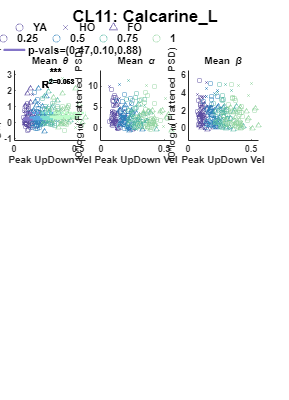

##12-theta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                       2.246         2        1.123       1.7407    0.17775
    mean_APexc_COV                 0.25621         1      0.25621      0.39713    0.52921
    group_char:mean_APexc_COV       1.6643         2      0.83213       1.2898    0.27735
    Error                           145.81       226      0.64517                        
    Total                            149.4       231                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat      pValue  
                                         _________    ________    _______    _________

    (Intercept)                            0.90668     0.34185     2.6522    0.0085624
    group_char_H2000's                    -0.82878     0.62118    -1.3342      0.18348
    group_char_H3000's                    -0.79985     0.46093    -1.7353     0.084055
    mean_APexc_COV                       -0.032137    0.021064    -1.5257      0.12849
    group_char_H2000's:mean_APexc_COV     0.036975    0.031517     1.1732      0.24196
    group_char_H3000's:mean_APexc_COV     0.038179

##12-alpha_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      3.1635         2       1.5817      0.26976     0.7638
    mean_APexc_COV                  1.0048         1       1.0048      0.17137    0.67929
    group_char:mean_APexc_COV       1.3433         2      0.67167      0.11455    0.89182
    Error                           1325.1       226       5.8634                        
    Total                           1387.8       231                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat      pValue 
                                         _________    ________    ________    _______

    (Intercept)                             3.4301      1.0306      3.3283    0.00102
    group_char_H2000's                     0.57416      1.8727      0.3066    0.75943
    group_char_H3000's                    -0.67284      1.3896    -0.48421    0.62871
    mean_APexc_COV                       0.0087122    0.063501      0.1372      0.891
    group_char_H2000's:mean_APexc_COV    -0.045267    0.095014    -0.47642    0.63424
    group_char_H3000's:mean_APexc_COV    -0.022967    0.0

##12-beta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                      2.2111         2      1.1055       0.55751     0.57342
    mean_APexc_COV                  6.3156         1      6.3156        3.1849    0.075663
    group_char:mean_APexc_COV       3.4803         2      1.7401       0.87752     0.41722
    Error                           448.16       226       1.983                          
    Total                            461.5       231                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             2.0845     0.59933       3.478    0.00060581
    group_char_H2000's                    -0.70719       1.089    -0.64937       0.51676
    group_char_H3000's                     0.40009      0.8081      0.4951       0.62101
    mean_APexc_COV                        0.025851    0.036929     0.70003       0.48463
    group_char_H2000's:mean_APexc_COV     0.044515    0.055255     0.80562       0.42131
    group_char_H3000's:mean_APexc_COV

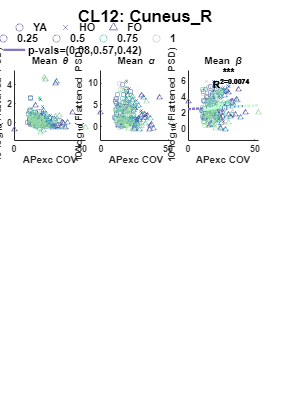

##12-theta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    ________    _______

    group_char                      0.027057        2     0.013529      0.020745    0.97947
    mean_APexc_mean                 0.014209        1     0.014209      0.021789    0.88278
    group_char:mean_APexc_mean      0.082981        2     0.041491      0.063623    0.93838
    Error                             147.38      226      0.65213                         
    Total                              149.4      231                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate       SE         tStat      pValue 
                                          _________    _______    _________    _______

    (Intercept)                             0.28362    0.28973      0.97891    0.32867
    group_char_H2000's                    -0.084006    0.42879     -0.19592    0.84485
    group_char_H3000's                    -0.019467    0.39136    -0.049742    0.96037
    mean_APexc_mean                          2.1173      5.039      0.42019    0.67475
    group_char_H2000's:mean_APexc_mean      -2.4891     8.2199     -0.30281    0.76231
    group_char_H3000's:mean_APexc_mean      -2.33

##12-alpha_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                        17.05         2      8.5249        1.4667    0.23286
    mean_APexc_mean                   11.16         1       11.16        1.9202     0.1672
    group_char:mean_APexc_mean       4.8547         2      2.4273       0.41763    0.65911
    Error                            1313.5       226      5.8121                         
    Total                            1387.8       231                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                             3.3328    0.86497      3.8531    0.00015196
    group_char_H2000's                    -0.68347     1.2801    -0.53392       0.59392
    group_char_H3000's                     -1.9585     1.1684     -1.6762      0.095076
    mean_APexc_mean                         4.2541     15.043     0.28279        0.7776
    group_char_H2000's:mean_APexc_mean      8.0677      24.54     0.32876       0.74264
    group_char_H3000's:mean_APexc_mean    

##12-beta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                       2.5313         2       1.2657       0.6354    0.53066
    mean_APexc_mean                 0.88951         1      0.88951      0.44657    0.50465
    group_char:mean_APexc_mean       4.6314         2       2.3157       1.1626    0.31454
    Error                            450.17       226       1.9919                        
    Total                             461.5       231                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE         tStat        pValue  
                                          ________    _______    _________    __________

    (Intercept)                             2.5252    0.50637       4.9868    1.2227e-06
    group_char_H2000's                    -0.42768    0.74938     -0.57071       0.56877
    group_char_H3000's                     0.38049    0.68398      0.55629       0.57856
    mean_APexc_mean                       -0.60538     8.8066    -0.068742       0.94526
    group_char_H2000's:mean_APexc_mean      18.154     14.366       1.2637       0.20765
    group_char_H3000's:mean_APexc_mean

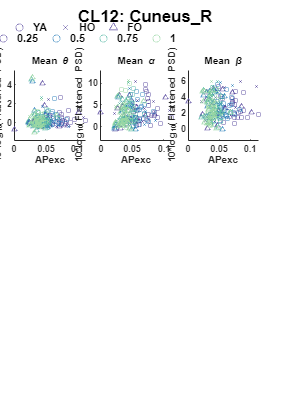

##12-theta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                     0.18196         2      0.09098      0.13975    0.86965
    mean_MLexc_COV                 0.14581         1      0.14581      0.22398    0.63648
    group_char:mean_MLexc_COV      0.16266         2      0.08133      0.12493    0.88262
    Error                           147.13       226        0.651                        
    Total                            149.4       231                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat      pValue 
                                         _________    ________    ________    _______

    (Intercept)                            0.29664      0.2285      1.2982    0.19553
    group_char_H2000's                   -0.073533      0.3885    -0.18927    0.85005
    group_char_H3000's                    -0.19196     0.36312    -0.52864    0.59757
    mean_MLexc_COV                       0.0073496    0.015107     0.48651    0.62708
    group_char_H2000's:mean_MLexc_COV    -0.010323    0.026417    -0.39079    0.69632
    group_char_H3000's:mean_MLexc_COV    0.0039794    0.0

##12-alpha_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares      F        pValue 
                                 ____________    ___    ___________    ______    ________

    group_char                      45.487         2      22.743       4.0228      0.0192
    mean_MLexc_COV                  22.389         1      22.389       3.9601    0.047797
    group_char:mean_MLexc_COV        18.61         2      9.3049       1.6458     0.19516
    Error                           1277.7       226      5.6536                         
    Total                           1387.8       231                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate       SE        tStat        pValue  
                                         ________    ________    ________    __________

    (Intercept)                            5.1353     0.67337      7.6262    6.6624e-13
    group_char_H2000's                   -0.54126      1.1449    -0.47276       0.63684
    group_char_H3000's                    -2.9676      1.0701     -2.7732     0.0060149
    mean_MLexc_COV                       -0.11113    0.044519     -2.4962      0.013267
    group_char_H2000's:mean_MLexc_COV    0.009726    0.077849     0.12493       0.90069
    group_char_H3000's:mean_MLexc_COV     0

##12-beta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    group_char                      2.3321         2        1.166       0.58542    0.55772
    mean_MLexc_COV                 0.02491         1      0.02491      0.012506    0.91106
    group_char:mean_MLexc_COV       4.6343         2       2.3172        1.1633     0.3143
    Error                           450.15       226       1.9918                         
    Total                            461.5       231                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             3.0123     0.39968      7.5368    1.1542e-12
    group_char_H2000's                    -0.14048     0.67956    -0.20672       0.83641
    group_char_H3000's                    -0.67531     0.63516     -1.0632       0.28882
    mean_MLexc_COV                       -0.036893    0.026424     -1.3962       0.16403
    group_char_H2000's:mean_MLexc_COV     0.038981    0.046208     0.84361       0.39978
    group_char_H3000's:mean_MLexc_COV

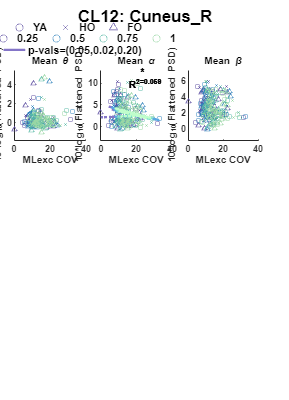

##12-theta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares      F        pValue 
                                  ____________    ___    ___________    ______    ________

    group_char                       4.1011         2       2.0506      3.2616    0.040139
    mean_MLexc_mean                 0.75119         1      0.75119      1.1948     0.27552
    group_char:mean_MLexc_mean        3.976         2        1.988       3.162    0.044218
    Error                            142.09       226       0.6287                        
    Total                             149.4       231                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE         tStat       pValue 
                                          ________    _______    _________    ________

    (Intercept)                            0.46619    0.24187       1.9274    0.055178
    group_char_H2000's                    -0.18807    0.37678     -0.49914     0.61816
    group_char_H3000's                    -0.80436    0.32911       -2.444    0.015291
    mean_MLexc_mean                       -0.80388     2.7823     -0.28893      0.7729
    group_char_H2000's:mean_MLexc_mean    -0.22788     4.0212    -0.056671     0.95486
    group_char_H3000's:mean_MLexc_mean      7.757

##12-alpha_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares      F        pValue 
                                  ____________    ___    ___________    ______    ________

    group_char                       24.008         2      12.004       2.1003     0.12481
    mean_MLexc_mean                  21.271         1      21.271       3.7216    0.054965
    group_char:mean_MLexc_mean        9.818         2       4.909       0.8589     0.42501
    Error                            1291.7       226      5.7155                         
    Total                            1387.8       231                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                            2.6327     0.72927        3.61    0.00037712
    group_char_H2000's                    0.52785       1.136     0.46464       0.64264
    group_char_H3000's                     -1.529     0.99231     -1.5408       0.12475
    mean_MLexc_mean                        11.409      8.3888        1.36       0.17517
    group_char_H2000's:mean_MLexc_mean    -10.842      12.124    -0.89421       0.37216
    group_char_H3000's:mean_MLexc_mean    

##12-beta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    _______    ________

    group_char                       13.729         2       6.8646       3.4936    0.032044
    mean_MLexc_mean                 0.58369         1      0.58369      0.29706     0.58627
    group_char:mean_MLexc_mean       11.111         2       5.5553       2.8272    0.061272
    Error                            444.07       226       1.9649                         
    Total                             461.5       231                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    _______    __________

    (Intercept)                            1.7066      0.4276      3.991    8.8929e-05
    group_char_H2000's                     1.1209      0.6661     1.6828      0.093793
    group_char_H3000's                     1.5077     0.58183     2.5912      0.010186
    mean_MLexc_mean                        9.5848      4.9187     1.9487      0.052574
    group_char_H2000's:mean_MLexc_mean    -8.7987      7.1089    -1.2377       0.21711
    group_char_H3000's:mean_MLexc_mean    -15.444 

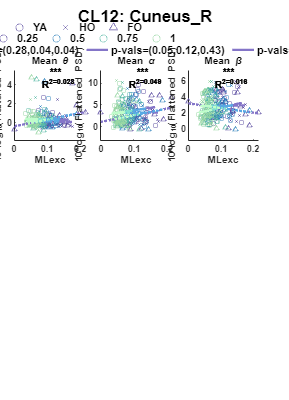

##12-theta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F       pValue 
                               ____________    ___    ___________    _______    _______

    group_char                   0.21149         2      0.10575      0.16267    0.84997
    mean_StepDur                  0.2759         1       0.2759      0.42441    0.51541
    group_char:mean_StepDur      0.19166         2     0.095831      0.14742    0.86302
    Error                         146.92       226      0.65007                        
    Total                          149.4       231                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate       SE        tStat      pValue 
                                       _________    _______    ________    _______

    (Intercept)                          0.25664    0.24454      1.0495    0.29508
    group_char_H2000's                 -0.054267    0.46274    -0.11727    0.90675
    group_char_H3000's                  -0.24359    0.42915     -0.5676    0.57087
    mean_StepDur                         0.15637    0.25059     0.62402    0.53325
    group_char_H2000's:mean_StepDur     -0.18223    0.55417    -0.32883    0.74259
    group_char_H3000's:mean_StepDur       0.1996    0.55975     0.35658    0.721

##12-alpha_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F        pValue 
                               ____________    ___    ___________    _______    ________

    group_char                    19.664         2      9.8322        1.7003     0.18495
    mean_StepDur                  17.584         1      17.584        3.0409    0.082548
    group_char:mean_StepDur       7.7532         2      3.8766       0.67039     0.51252
    Error                         1306.9       226      5.7825                          
    Total                         1387.8       231                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate      SE        tStat        pValue  
                                       ________    _______    ________    __________

    (Intercept)                          3.0732    0.72934      4.2137    3.6324e-05
    group_char_H2000's                 -0.52963     1.3801    -0.38376       0.70152
    group_char_H3000's                  -2.3494     1.2799     -1.8355      0.067739
    mean_StepDur                        0.53771    0.74737     0.71947        0.4726
    group_char_H2000's:mean_StepDur     0.33822     1.6528     0.20464       0.83804
    group_char_H3000's:mean_StepDur      1.9324     1.6694      1.

##12-beta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F        pValue 
                               ____________    ___    ___________    ________    _______

    group_char                    0.42398        2      0.21199       0.10529    0.90011
    mean_StepDur                  0.20408        1      0.20408       0.10136     0.7505
    group_char:mean_StepDur      0.069211        2     0.034605      0.017187    0.98296
    Error                          455.03      226       2.0134                         
    Total                           461.5      231                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate       SE         tStat        pValue  
                                       _________    _______    _________    __________

    (Intercept)                            2.398    0.43037        5.572    7.1347e-08
    group_char_H2000's                   0.30129    0.81437      0.36997       0.71175
    group_char_H3000's                   0.27966    0.75526      0.37029       0.71151
    mean_StepDur                         0.10207    0.44101      0.23144       0.81718
    group_char_H2000's:mean_StepDur       0.1609    0.97528      0.16498       0.86911
    group_char_H3000's:mean_StepDur    -0.048706     

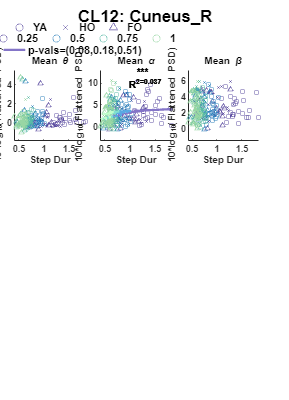

##12-theta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    group_char                      0.15653        2     0.078263       0.12025    0.88676
    mean_UDexc_COV                 0.044482        1     0.044482      0.068343      0.794
    group_char:mean_UDexc_COV       0.37431        2      0.18716       0.28755    0.75037
    Error                            147.09      226      0.65086                         
    Total                             149.4      231                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                          Estimate        SE         tStat       pValue 
                                         __________    ________    _________    ________

    (Intercept)                             0.36725     0.21194       1.7328    0.084492
    group_char_H2000's                   -0.0080029     0.33372    -0.023981     0.98089
    group_char_H3000's                     -0.15063     0.32966     -0.45692     0.64817
    mean_UDexc_COV                         0.002695    0.015904      0.16945     0.86559
    group_char_H2000's:mean_UDexc_COV     -0.015678    0.023434     -0.66902     0.50416
    group_char_H3000's:mean_UDexc_COV

##12-alpha_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      11.492         2       5.746       0.98372    0.37551
    mean_UDexc_COV                  4.6711         1      4.6711        0.7997    0.37213
    group_char:mean_UDexc_COV       3.3589         2      1.6795       0.28753    0.75039
    Error                           1320.1       226      5.8411                         
    Total                           1387.8       231                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                          Estimate        SE         tStat        pValue  
                                         __________    ________    _________    __________

    (Intercept)                              3.6737      0.6349       5.7862    2.3855e-08
    group_char_H2000's                      0.31476     0.99973      0.31485       0.75317
    group_char_H3000's                      -1.1053     0.98758      -1.1192       0.26424
    mean_UDexc_COV                        -0.008659    0.047644     -0.18174       0.85595
    group_char_H2000's:mean_UDexc_COV     -0.048332    0.070202     -0.68848       0.49186
    group_char_H3000's:mean_UDe

##12-beta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                        2.54         2        1.27       0.63664    0.53001
    mean_UDexc_COV                  1.5716         1      1.5716       0.78783     0.3757
    group_char:mean_UDexc_COV       3.0229         2      1.5114       0.75765    0.46995
    Error                           450.84       226      1.9949                         
    Total                            461.5       231                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                          Estimate        SE        tStat        pValue  
                                         __________    ________    ________    __________

    (Intercept)                              2.5558     0.37104      6.8881    5.5443e-11
    group_char_H2000's                       0.2507     0.58424      0.4291       0.66826
    group_char_H3000's                     -0.44872     0.57715    -0.77749       0.43768
    mean_UDexc_COV                       -0.0052101    0.027843    -0.18712       0.85173
    group_char_H2000's:mean_UDexc_COV      0.012105    0.041026     0.29506       0.76822
    group_char_H3000's:mean_UDexc_COV</

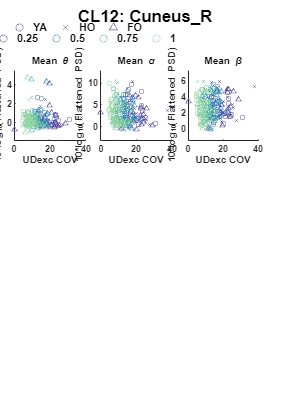

##12-theta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    ________    _______

    group_char                       1.1076         2      0.55378       0.85115    0.42829
    mean_UDexc_mean                 0.02824         1      0.02824      0.043405    0.83515
    group_char:mean_UDexc_mean      0.39184         2      0.19592       0.30112    0.74028
    Error                            147.04       226      0.65062                         
    Total                             149.4       231                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue 
                                          ________    _______    ________    ________

    (Intercept)                            0.57386    0.24662      2.3269    0.020857
    group_char_H2000's                    -0.50168    0.39946     -1.2559     0.21045
    group_char_H3000's                    -0.29782    0.33772    -0.88187     0.37879
    mean_UDexc_mean                        -7.2759     9.7479     -0.7464      0.4562
    group_char_H2000's:mean_UDexc_mean      11.713     15.352     0.76296     0.44628
    group_char_H3000's:mean_UDexc_mean      6.3977      

##12-alpha_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    ________    _______

    group_char                       6.2379         2       3.1189       0.53386    0.58707
    mean_UDexc_mean                  6.0288         1       6.0288        1.0319    0.31079
    group_char:mean_UDexc_mean       0.3673         2      0.18365      0.031435    0.96906
    Error                            1320.3       226       5.8422                         
    Total                            1387.8       231                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                              4.001    0.73902      5.4139    1.5712e-07
    group_char_H2000's                    -0.47665      1.197     -0.3982       0.69086
    group_char_H3000's                      -1.043      1.012     -1.0306       0.30382
    mean_UDexc_mean                        -18.185      29.21    -0.62256        0.5342
    group_char_H2000's:mean_UDexc_mean      5.6764     46.002     0.12339       0.90191
    group_char_H3000's:mean_UDexc_mean    

##12-beta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares      F       pValue 
                                  ____________    ___    ___________    ______    _______

    group_char                       8.6292         2      4.3146       2.2023    0.11291
    mean_UDexc_mean                  6.8791         1      6.8791       3.5114    0.06224
    group_char:mean_UDexc_mean       5.4965         2      2.7483       1.4028    0.24804
    Error                            442.76       226      1.9591                        
    Total                             461.5       231                                    



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    _______    __________

    (Intercept)                            2.4098     0.42795      5.631    5.2912e-08
    group_char_H2000's                     1.1821     0.69316     1.7054      0.089497
    group_char_H3000's                     1.0905     0.58603     1.8608      0.064078
    mean_UDexc_mean                        3.4375      16.915    0.20322       0.83915
    group_char_H2000's:mean_UDexc_mean    -31.227      26.639    -1.1722       0.24234
    group_char_H3000's:mean_UDexc_mean    -37.102 

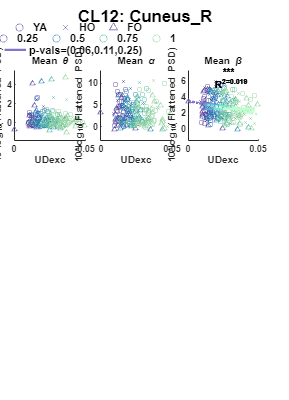

##12-theta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                     0.36354         2      0.18177      0.27995    0.75608
    mean_StanceDur                 0.34825         1      0.34825      0.53634    0.46471
    group_char:mean_StanceDur      0.32256         2      0.16128       0.2484    0.78026
    Error                           146.74       226       0.6493                        
    Total                            149.4       231                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate       SE        tStat      pValue 
                                         _________    _______    ________    _______

    (Intercept)                            0.27945    0.20565      1.3589    0.17555
    group_char_H2000's                   -0.063413     0.3824    -0.16583    0.86844
    group_char_H3000's                    -0.27138    0.36401    -0.74555    0.45671
    mean_StanceDur                        0.095978    0.14965     0.64135    0.52195
    group_char_H2000's:mean_StanceDur     -0.12835    0.33012    -0.38878     0.6978
    group_char_H3000's:mean_StanceDur      0.17248    0.34498   

##12-alpha_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                       21.47         2      10.735        1.8568    0.15855
    mean_StanceDur                   15.76         1       15.76        2.7259    0.10012
    group_char:mean_StanceDur       7.1952         2      3.5976       0.62226    0.53765
    Error                           1306.6       226      5.7815                         
    Total                           1387.8       231                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate      SE        tStat        pValue  
                                         ________    _______    ________    __________

    (Intercept)                             3.043    0.61366      4.9588    1.3928e-06
    group_char_H2000's                   -0.14414     1.1411    -0.12632       0.89959
    group_char_H3000's                    -2.0316     1.0862     -1.8704      0.062724
    mean_StanceDur                        0.41629    0.44656     0.93221       0.35222
    group_char_H2000's:mean_StanceDur    -0.11205    0.98507    -0.11375       0.90954
    group_char_H3000's:mean_StanceDur      1.0971 

##12-beta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares        F        pValue 
                                 ____________    ___    ___________    _________    _______

    group_char                      0.87921        2      0.43961        0.21852    0.80388
    mean_StanceDur                  0.44129        1      0.44129        0.21936    0.63998
    group_char:mean_StanceDur      0.010876        2     0.005438      0.0027031     0.9973
    Error                            454.65      226       2.0117                          
    Total                             461.5      231                                       



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate       SE         tStat       pValue  
                                         _________    _______    _________    _________

    (Intercept)                             2.3378    0.36199       6.4582    6.409e-10
    group_char_H2000's                     0.40429     0.6731      0.60064      0.54868
    group_char_H3000's                     0.28551    0.64073       0.4456      0.65631
    mean_StanceDur                         0.12226    0.26342      0.46411      0.64301
    group_char_H2000's:mean_StanceDur     0.030909    0.58108     0.053192      0.95763
    group_char_H3000's:mean_StanceDur    -0.

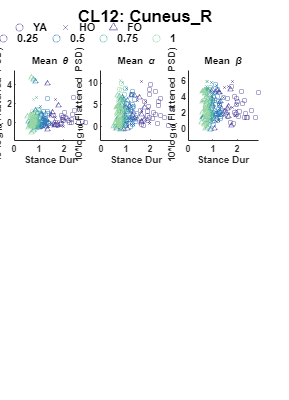

##12-theta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F       pValue 
                                    ____________    ___    ___________    _______    _______

    group_char                        0.21268         2      0.10634      0.16359    0.84919
    mean_GaitCycleDur                 0.27737         1      0.27737      0.42669    0.51428
    group_char:mean_GaitCycleDur      0.19503         2     0.097515      0.15001    0.86078
    Error                              146.91       226      0.65006                        
    Total                               149.4       231                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate       SE        tStat      pValue 
                                            _________    _______    ________    _______

    (Intercept)                               0.25645    0.24428      1.0498    0.29493
    group_char_H2000's                      -0.053101    0.46091    -0.11521    0.90838
    group_char_H3000's                       -0.24397    0.42885    -0.56891    0.56998
    mean_GaitCycleDur                        0.078243    0.12507     0.62561     0.5322
    group_char_H2000's:mean_GaitCycleDur    -0.091793    0.27554    -0.33313    0.73934
    group_char_H3000's:mean_GaitCycleDur

##12-alpha_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F        pValue 
                                    ____________    ___    ___________    _______    ________

    group_char                         19.774         2      9.8869        1.7099     0.18322
    mean_GaitCycleDur                  17.661         1      17.661        3.0544    0.081876
    group_char:mean_GaitCycleDur       7.8166         2      3.9083       0.67591     0.50972
    Error                              1306.8       226      5.7823                          
    Total                              1387.8       231                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate      SE        tStat        pValue  
                                            ________    _______    ________    __________

    (Intercept)                               3.0743    0.72855      4.2197    3.5432e-05
    group_char_H2000's                      -0.52561     1.3746    -0.38236       0.70255
    group_char_H3000's                       -2.3538      1.279     -1.8403      0.067034
    mean_GaitCycleDur                        0.26811    0.37301     0.71879       0.47301
    group_char_H2000's:mean_GaitCycleDur     0.16607    0.82179     0.20208       0.84004
    group_char_H3000's:mean_GaitCyc

##12-beta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F        pValue 
                                    ____________    ___    ___________    ________    _______

    group_char                         0.40914        2      0.20457       0.10161    0.90342
    mean_GaitCycleDur                   0.2208        1       0.2208       0.10967    0.74083
    group_char:mean_GaitCycleDur      0.079062        2     0.039531      0.019635    0.98056
    Error                               455.01      226       2.0133                         
    Total                                461.5      231                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate       SE         tStat        pValue  
                                            _________    _______    _________    __________

    (Intercept)                                 2.398     0.4299        5.578    6.9197e-08
    group_char_H2000's                        0.29135    0.81114      0.35918        0.7198
    group_char_H3000's                        0.27784    0.75471      0.36814       0.71312
    mean_GaitCycleDur                        0.051002     0.2201      0.23172       0.81696
    group_char_H2000's:mean_GaitCycleDur     0.086839    0.48492      0.17908       0.85804
    group_char_H3000's

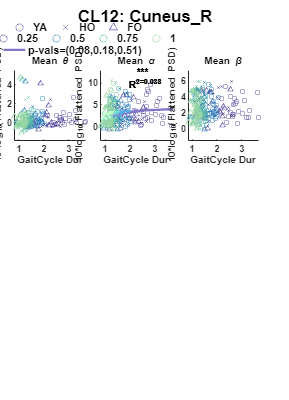

##12-theta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F       pValue 
                                          ____________    ___    ___________    _______    _______

    group_char                               0.88995        2      0.44497      0.68324    0.50602
    mean_PeakUpDownVel_mean                 0.080631        1     0.080631       0.1238    0.72527
    group_char:mean_PeakUpDownVel_mean       0.23455        2      0.11728      0.18007    0.83533
    Error                                     147.19      226      0.65127                        
    Total                                      149.4      231                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat       pValue  
                                                  ________    _______    ________    _________

    (Intercept)                                    0.51778    0.19886      2.6037    0.0098339
    group_char_H2000's                            -0.30125     0.3219    -0.93585      0.35035
    group_char_H3000's                            -0.29849    0.28937     -1.0315       0.3034
    mean_PeakUpDownVel_mean                        -0.5024    0.77434    -0.64881      0.51712
    group_char_H2000's:mean_PeakUpDownVel_mean     0.37184     1.1733     0.31691       0.7516
  

##12-alpha_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F        pValue 
                                          ____________    ___    ___________    _______    ________

    group_char                               4.2338         2      2.1169       0.36583     0.69403
    mean_PeakUpDownVel_mean                   16.22         1       16.22        2.8032    0.095463
    group_char:mean_PeakUpDownVel_mean        3.976         2       1.988       0.34356     0.70961
    Error                                    1307.7       226      5.7865                          
    Total                                    1387.8       231                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat        pValue  
                                                  ________    _______    ________    __________

    (Intercept)                                     3.7401    0.59276      6.3097    1.4581e-09
    group_char_H2000's                             0.26367     0.9595      0.2748       0.78372
    group_char_H3000's                            -0.53195    0.86253    -0.61674       0.53803
    mean_PeakUpDownVel_mean                       -0.73921     2.3081    -0.32027       0.74906
    group_char_H2000's:mean_PeakUpDownVel_mean     -2.3047     3.4974    -0.65898       0.5

##12-beta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares      F        pValue 
                                          ____________    ___    ___________    ______    ________

    group_char                               8.3846         2      4.1923       2.1437     0.11959
    mean_PeakUpDownVel_mean                  9.0713         1      9.0713       4.6386    0.032319
    group_char:mean_PeakUpDownVel_mean       4.2523         2      2.1262       1.0872     0.33892
    Error                                    441.97       226      1.9556                         
    Total                                     461.5       231                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat        pValue  
                                                  ________    _______    ________    __________

    (Intercept)                                     2.5289     0.3446      7.3387    3.8481e-12
    group_char_H2000's                             0.94819     0.5578      1.6999      0.090528
    group_char_H3000's                             0.89865    0.50143      1.7922      0.074444
    mean_PeakUpDownVel_mean                       -0.15877     1.3418    -0.11833       0.90591
    group_char_H2000's:mean_PeakUpDownVel_mean     -2.0617     2.0332      -1.014       0.31

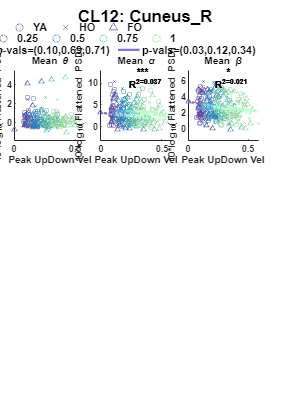

##13-theta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                      3.0236         2       1.5118       2.0462     0.13219
    mean_APexc_COV                 0.19648         1      0.19648      0.26593      0.6067
    group_char:mean_APexc_COV       6.1658         2       3.0829       4.1725    0.016913
    Error                           134.47       182      0.73885                         
    Total                           155.59       187                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat      pValue  
                                         _________    ________    _______    _________

    (Intercept)                           0.092089      0.3694    0.24929      0.80342
    group_char_H2000's                     0.33911      0.6823      0.497      0.61979
    group_char_H3000's                      1.1984     0.59506     2.0139     0.045491
    mean_APexc_COV                         0.05525    0.022363     2.4706      0.01441
    group_char_H2000's:mean_APexc_COV    -0.061425    0.034202    -1.7959     0.074163
    group_char_H3000's:mean_APexc_COV    -0.084108

##13-alpha_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares      F       pValue 
                                 ____________    ___    ___________    ______    _______

    group_char                      4.6024         2      2.3012       1.4202    0.24433
    mean_APexc_COV                  3.4065         1      3.4065       2.1024    0.14879
    group_char:mean_APexc_COV       6.2983         2      3.1491       1.9435    0.14616
    Error                            294.9       182      1.6203                        
    Total                           308.32       187                                    



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue 
                                         _________    ________    ________    ________

    (Intercept)                            0.98298     0.54704      1.7969    0.074009
    group_char_H2000's                      1.6914      1.0104      1.6739    0.095862
    group_char_H3000's                     0.33325     0.88122     0.37816     0.70575
    mean_APexc_COV                        0.015109    0.033118     0.45621     0.64878
    group_char_H2000's:mean_APexc_COV    -0.098691    0.050649     -1.9485     0.05289
    group_char_H3000's:mean_APexc_COV    -0.030818

##13-beta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      2.2966         2       1.1483       1.3154    0.27089
    mean_APexc_COV                 0.33805         1      0.33805      0.38727    0.53452
    group_char:mean_APexc_COV       2.3241         2       1.1621       1.3312    0.26671
    Error                           158.87       182      0.87292                        
    Total                           161.78       187                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue 
                                         _________    ________    ________    ________

    (Intercept)                            0.91747     0.40152       2.285    0.023467
    group_char_H2000's                     0.92567     0.74163      1.2482     0.21358
    group_char_H3000's                    -0.35969      0.6468     -0.5561     0.57882
    mean_APexc_COV                       -0.003519    0.024308    -0.14477     0.88505
    group_char_H2000's:mean_APexc_COV    -0.036537    0.037176    -0.98281       0.327
    group_char_H3000's:mean_APexc_COV     0.020574 

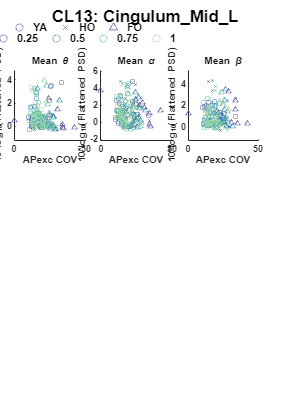

##13-theta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares        F        pValue 
                                  ____________    ___    ___________    _________    _______

    group_char                       0.54985        2      0.27492        0.35604    0.70093
    mean_APexc_mean                 0.001516        1     0.001516      0.0019634    0.96471
    group_char:mean_APexc_mean       0.14681        2     0.073403       0.095062    0.90936
    Error                             140.53      182      0.77216                          
    Total                             155.59      187                                       



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                            0.85391    0.32583      2.6207    0.0095154
    group_char_H2000's                    -0.45842    0.54891    -0.83514      0.40473
    group_char_H3000's                    -0.21604    0.49063    -0.44034      0.66021
    mean_APexc_mean                         2.3025     5.8754     0.39188      0.69561
    group_char_H2000's:mean_APexc_mean     -4.5594     11.386    -0.40044       0.6893
    group_char_H3000's:mean_APexc_mean     -2.990

##13-alpha_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares        F          pValue 
                                  ____________    ___    ___________    __________    ________

    group_char                        12.095        2        6.0475         3.7769    0.024709
    mean_APexc_mean                0.0014488        1     0.0014488     0.00090483     0.97604
    group_char:mean_APexc_mean        11.838        2        5.9192         3.6968    0.026685
    Error                             291.42      182        1.6012                           
    Total                             308.32      187                                         



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                            1.3948     0.46919      2.9728    0.0033506
    group_char_H2000's                    -1.7089     0.79044      -2.162     0.031923
    group_char_H3000's                    0.49965     0.70651     0.70721      0.48034
    mean_APexc_mean                       -3.2018      8.4607    -0.37843      0.70555
    group_char_H2000's:mean_APexc_mean     30.386      16.396      1.8533     0.065457
    group_char_H3000's:mean_APexc_mean    -21.409

##13-beta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                      0.91765         2      0.45882      0.52185     0.5943
    mean_APexc_mean                 0.97465         1      0.97465       1.1085     0.2938
    group_char:mean_APexc_mean      0.74859         2       0.3743      0.42571    0.65395
    Error                            160.02       182      0.87922                        
    Total                            161.78       187                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue 
                                          ________    _______    ________    ________

    (Intercept)                            0.8503     0.34768      2.4456    0.015411
    group_char_H2000's                     0.5703     0.58573     0.97365     0.33152
    group_char_H3000's                    0.34979     0.52353     0.66814     0.50489
    mean_APexc_mean                       0.20443      6.2695    0.032607     0.97402
    group_char_H2000's:mean_APexc_mean    -10.447       12.15    -0.85986       0.391
    group_char_H3000's:mean_APexc_mean    -6.4599      11

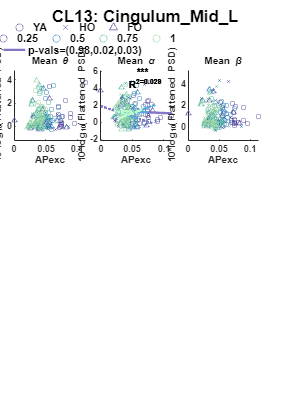

##13-theta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                      4.2941         2       2.1471       2.8094    0.062858
    mean_MLexc_COV                 0.30756         1      0.30756      0.40243     0.52663
    group_char:mean_MLexc_COV       1.0061         2      0.50307      0.65825     0.51898
    Error                           139.09       182      0.76425                         
    Total                           155.59       187                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue  
                                         _________    ________    _______    __________

    (Intercept)                             1.3284       0.276     4.8131    3.1113e-06
    group_char_H2000's                    -0.92015     0.44304    -2.0769      0.039215
    group_char_H3000's                    -0.85174     0.46585    -1.8284      0.069132
    mean_MLexc_COV                       -0.026203    0.019328    -1.3558       0.17686
    group_char_H2000's:mean_MLexc_COV     0.018438    0.029769    0.61938       0.53644
    group_char_H3000's:mean_MLexc_COV     0

##13-alpha_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      3.4646         2      1.7323        1.0564    0.34983
    mean_MLexc_COV                  2.0212         1      2.0212        1.2326    0.26837
    group_char:mean_MLexc_COV        2.002         2       1.001       0.61044    0.54422
    Error                           298.45       182      1.6398                         
    Total                           308.32       187                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             1.8012     0.40428      4.4552    1.4607e-05
    group_char_H2000's                    -0.53863     0.64897    -0.82998       0.40764
    group_char_H3000's                    -0.96581     0.68238     -1.4154       0.15867
    mean_MLexc_COV                       -0.042884    0.028311     -1.5147       0.13157
    group_char_H2000's:mean_MLexc_COV     0.015022    0.043606     0.34451       0.73086
    group_char_H3000's:mean_MLexc_COV

##13-beta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                     0.68662         2      0.34331      0.39295    0.67563
    mean_MLexc_COV                  1.4427         1       1.4427       1.6513    0.20041
    group_char:mean_MLexc_COV      0.83138         2      0.41569      0.47579    0.62216
    Error                           159.01       182      0.87367                        
    Total                           161.78       187                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             1.1273      0.2951        3.82    0.00018295
    group_char_H2000's                    -0.15859     0.47369    -0.33479       0.73817
    group_char_H3000's                     0.31844     0.49808     0.63934        0.5234
    mean_MLexc_COV                       -0.019797    0.020665    -0.95802       0.33932
    group_char_H2000's:mean_MLexc_COV     0.020325    0.031829     0.63858        0.5239
    group_char_H3000's:mean_MLexc_COV

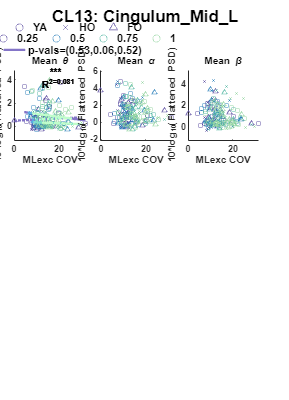

##13-theta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                      0.32171         2      0.16086      0.21198    0.80918
    mean_MLexc_mean                 0.69981         1      0.69981      0.92223    0.33817
    group_char:mean_MLexc_mean       1.5937         2      0.79687       1.0501      0.352
    Error                            138.11       182      0.75883                        
    Total                            155.59       187                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue 
                                          ________    _______    ________    ________

    (Intercept)                            0.48116    0.28355      1.6969    0.091425
    group_char_H2000's                    -0.17191    0.43424    -0.39588     0.69266
    group_char_H3000's                     0.12541    0.42666     0.29394     0.76914
    mean_MLexc_mean                          5.896     3.1909      1.8478    0.066259
    group_char_H2000's:mean_MLexc_mean     -6.0329     4.7809     -1.2619     0.20861
    group_char_H3000's:mean_MLexc_mean     -5.8356      

##13-alpha_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                        6.507         2       3.2535       1.9992     0.1384
    mean_MLexc_mean                 0.58639         1      0.58639      0.36033    0.54907
    group_char:mean_MLexc_mean       6.8676         2       3.4338         2.11    0.12419
    Error                            296.18       182       1.6274                        
    Total                            308.32       187                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue 
                                          ________    _______    ________    ________

    (Intercept)                             1.2556    0.41525      3.0237    0.002858
    group_char_H2000's                    -0.83317    0.63592     -1.3102     0.19179
    group_char_H3000's                     0.49511    0.62483     0.79239     0.42916
    mean_MLexc_mean                       -0.36696     4.6729    -0.07853     0.93749
    group_char_H2000's:mean_MLexc_mean      5.5561     7.0013     0.79358     0.42847
    group_char_H3000's:mean_MLexc_mean     -9.7824     7

##13-beta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares      F        pValue 
                                  ____________    ___    ___________    ______    ________

    group_char                       4.6365         2       2.3183       2.709    0.069291
    mean_MLexc_mean                  1.8646         1       1.8646      2.1788     0.14165
    group_char:mean_MLexc_mean       4.1421         2       2.0711      2.4201    0.091768
    Error                            155.75       182      0.85577                        
    Total                            161.78       187                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat      pValue 
                                          ________    _______    _______    ________

    (Intercept)                           0.62527     0.30112     2.0765    0.039254
    group_char_H2000's                     1.0441     0.46115     2.2641    0.024751
    group_char_H3000's                    0.66577      0.4531     1.4694     0.14346
    mean_MLexc_mean                        2.8095      3.3886     0.8291     0.40814
    group_char_H2000's:mean_MLexc_mean    -10.929      5.0771    -2.1527    0.032658
    group_char_H3000's:mean_MLexc_mean    -6.9983      5.2078   

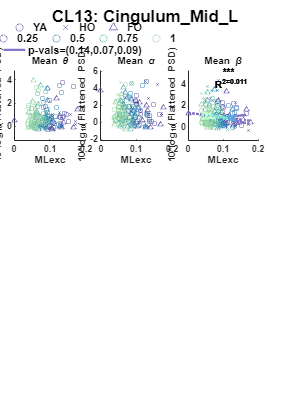

##13-theta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F        pValue 
                               ____________    ___    ___________    ________    _______

    group_char                     2.8321        2       1.4161        1.8413    0.16155
    mean_StepDur                 0.018898        1     0.018898      0.024573    0.87561
    group_char:mean_StepDur       0.49719        2      0.24859       0.32325    0.72421
    Error                          139.97      182      0.76906                         
    Total                          155.59      187                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate      SE        tStat        pValue  
                                       ________    _______    ________    __________

    (Intercept)                          1.2023    0.28589      4.2054    4.0838e-05
    group_char_H2000's                 -0.91399    0.56366     -1.6215       0.10664
    group_char_H3000's                 -0.86453    0.63018     -1.3719       0.17179
    mean_StepDur                        -0.2512    0.30019    -0.83681        0.4038
    group_char_H2000's:mean_StepDur     0.26356    0.69402     0.37977       0.70456
    group_char_H3000's:mean_StepDur     0.65784     0.8684     0.7

##13-alpha_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F        pValue 
                               ____________    ___    ___________    _______    ________

    group_char                    8.8812         2      4.4406        2.7328    0.067705
    mean_StepDur                  0.5108         1      0.5108       0.31435     0.57571
    group_char:mean_StepDur       7.2979         2      3.6489        2.2456     0.10879
    Error                         295.73       182      1.6249                          
    Total                         308.32       187                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate       SE         tStat       pValue  
                                       _________    _______    _________    _________

    (Intercept)                           1.2629    0.41556        3.039    0.0027236
    group_char_H2000's                   -1.7807    0.81932      -2.1734     0.031045
    group_char_H3000's                   0.30987    0.91601      0.33828      0.73554
    mean_StepDur                       -0.042366    0.43635    -0.097091      0.92276
    group_char_H2000's:mean_StepDur       1.8878     1.0088       1.8713      0.06291
    group_char_H3000's:mean_StepDur     -0.88834     1.2623

##13-beta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F        pValue 
                               ____________    ___    ___________    ________    _______

    group_char                    0.20192        2      0.10096       0.11404    0.89229
    mean_StepDur                 0.020093        1     0.020093      0.022696    0.88042
    group_char:mean_StepDur       0.11549        2     0.057747      0.065227    0.93688
    Error                          161.13      182      0.88532                         
    Total                          161.78      187                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate      SE        tStat       pValue  
                                       ________    _______    ________    _________

    (Intercept)                         0.82942    0.30674       2.704    0.0075015
    group_char_H2000's                 0.088869    0.60477     0.14695      0.88334
    group_char_H3000's                  0.32186    0.67614     0.47602      0.63463
    mean_StepDur                       0.035264    0.32209     0.10949      0.91294
    group_char_H2000's:mean_StepDur    0.041999    0.74463    0.056403      0.95508
    group_char_H3000's:mean_StepDur     -0.3208    0.93173    -0.34431    

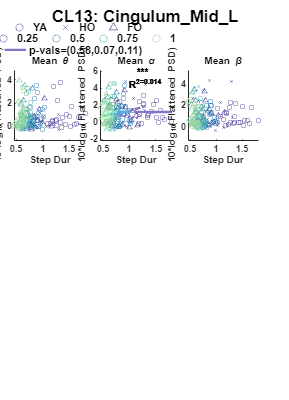

##13-theta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                       3.094         2        1.547       2.0258    0.13485
    mean_UDexc_COV                 0.75325         1      0.75325      0.98639    0.32195
    group_char:mean_UDexc_COV      0.71672         2      0.35836      0.46927    0.62621
    Error                           138.98       182      0.76365                        
    Total                           155.59       187                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                          Estimate        SE         tStat        pValue  
                                         __________    ________    _________    __________

    (Intercept)                              1.2147     0.22521       5.3937    2.1255e-07
    group_char_H2000's                      -0.6215     0.41281      -1.5055       0.13392
    group_char_H3000's                     -0.66615     0.38054      -1.7506      0.081707
    mean_UDexc_COV                        -0.019285    0.016578      -1.1633       0.24623
    group_char_H2000's:mean_UDexc_COV    -0.0020569    0.028559    -0.072022       0.94266
    group_char_H3000's:mean_UDe

##13-alpha_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares      F        pValue  
                                 ____________    ___    ___________    ______    _________

    group_char                        3.94         2        1.97       1.2467       0.2899
    mean_UDexc_COV                  11.308         1      11.308        7.156    0.0081525
    group_char:mean_UDexc_COV       9.0154         2      4.5077       2.8526     0.060276
    Error                            287.6       182      1.5802                          
    Total                           308.32       187                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue  
                                         _________    ________    _______    __________

    (Intercept)                             1.1447     0.32397     3.5335    0.00051988
    group_char_H2000's                     0.80218     0.59382     1.3509       0.17842
    group_char_H3000's                     0.66237      0.5474       1.21       0.22784
    mean_UDexc_COV                       0.0064697    0.023847     0.2713       0.78647
    group_char_H2000's:mean_UDexc_COV    -0.084542    0.041082    -2.0579      0.041025
    group_char_H3000's:mean_UDexc_COV     -

##13-beta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      1.2824         2      0.64121      0.73021    0.48322
    mean_UDexc_COV                  0.8432         1       0.8432      0.96023    0.32843
    group_char:mean_UDexc_COV      0.88428         2      0.44214      0.50351    0.60525
    Error                           159.82       182      0.87812                        
    Total                           161.78       187                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             0.8398      0.2415      3.4774    0.00063325
    group_char_H2000's                      0.3007     0.44267     0.67929       0.49781
    group_char_H3000's                     0.47551     0.40807      1.1653       0.24543
    mean_UDexc_COV                       0.0017268    0.017777    0.097137       0.92272
    group_char_H2000's:mean_UDexc_COV    -0.013587    0.030625    -0.44367       0.65781
    group_char_H3000's:mean_UDexc_COV

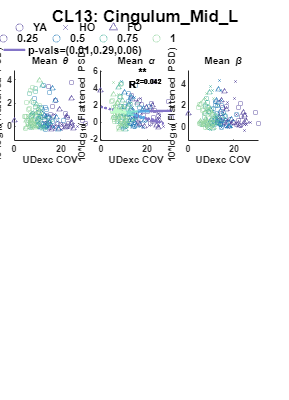

##13-theta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    ________    _______

    group_char                        3.5357        2       1.7679        2.2922    0.10395
    mean_UDexc_mean                 0.065774        1     0.065774      0.085283    0.77059
    group_char:mean_UDexc_mean       0.30472        2      0.15236       0.19755    0.82091
    Error                             140.37      182      0.77124                         
    Total                             155.59      187                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                             1.0666    0.27333      3.9022    0.00013406
    group_char_H2000's                    -0.91628    0.44037     -2.0807      0.038861
    group_char_H3000's                    -0.54533    0.41689     -1.3081        0.1925
    mean_UDexc_mean                        -3.6958     10.498    -0.35204       0.72522
    group_char_H2000's:mean_UDexc_mean      9.9306      17.18     0.57802       0.56397
    group_char_H3000's:mean_UDexc_mean    

##13-alpha_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    ________    _______

    group_char                        3.3719        2       1.6859        1.0233    0.36148
    mean_UDexc_mean                 0.022232        1     0.022232      0.013493    0.90765
    group_char:mean_UDexc_mean        3.4203        2       1.7101        1.0379    0.35627
    Error                             299.87      182       1.6476                         
    Total                             308.32      187                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat      pValue  
                                          ________    _______    _______    _________

    (Intercept)                             1.1675    0.39951     2.9224    0.0039136
    group_char_H2000's                    -0.64755    0.64365    -1.0061      0.31572
    group_char_H3000's                      0.3166    0.60934    0.51958      0.60399
    mean_UDexc_mean                          2.339     15.344    0.15244      0.87901
    group_char_H2000's:mean_UDexc_mean      12.285     25.111    0.48924      0.62526
    group_char_H3000's:mean_UDexc_mean     -22.769     2

##13-beta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares      F        pValue  
                                  ____________    ___    ___________    ______    _________

    group_char                       3.8783         2       1.9391      2.3014      0.10302
    mean_UDexc_mean                  5.7829         1       5.7829      6.8634    0.0095406
    group_char:mean_UDexc_mean       3.3145         2       1.6573      1.9669      0.14285
    Error                            153.35       182      0.84257                         
    Total                            161.78       187                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE         tStat       pValue  
                                          ________    _______    _________    _________

    (Intercept)                              0.859    0.28569       3.0067    0.0030142
    group_char_H2000's                     0.89119    0.46028       1.9362     0.054393
    group_char_H3000's                     0.71118    0.43575       1.6321      0.10439
    mean_UDexc_mean                       0.088243     10.973    0.0080419      0.99359
    group_char_H2000's:mean_UDexc_mean     -32.864     17.957      -1.8301     0.068873
    group_char_H3000's:mean_UDexc_mean     

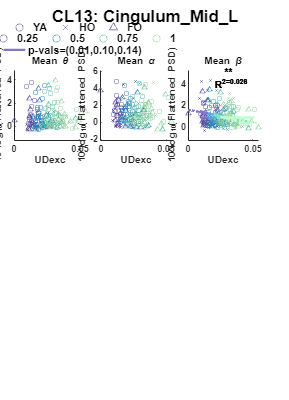

##13-theta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    group_char                      2.7957         2       1.3978        1.8161     0.1656
    mean_StanceDur                 0.16754         1      0.16754       0.21767    0.64138
    group_char:mean_StanceDur      0.13191         2     0.065953      0.085685    0.91792
    Error                           140.09       182      0.76971                         
    Total                           155.59       187                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate       SE        tStat        pValue  
                                         _________    _______    ________    __________

    (Intercept)                             1.1547    0.23889      4.8337    2.8387e-06
    group_char_H2000's                    -0.87893    0.46723     -1.8812      0.061546
    group_char_H3000's                    -0.38313    0.51667    -0.74154       0.45932
    mean_StanceDur                        -0.14529     0.1789    -0.81213       0.41778
    group_char_H2000's:mean_StanceDur      0.16703    0.42037     0.39734       0.69158
    group_char_H3000's:mean_StanceDur    -0

##13-alpha_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      5.9864         2       2.9932       1.8249    0.16417
    mean_StanceDur                 0.51163         1      0.51163      0.31194    0.57718
    group_char:mean_StanceDur       4.4242         2       2.2121       1.3487    0.26216
    Error                           298.51       182       1.6402                        
    Total                           308.32       187                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate      SE        tStat       pValue  
                                         ________    _______    ________    _________

    (Intercept)                            1.1918    0.34872      3.4176    0.0007794
    group_char_H2000's                     -1.232    0.68204     -1.8063     0.072526
    group_char_H3000's                    0.13396    0.75421     0.17761      0.85923
    mean_StanceDur                       0.026827    0.26116     0.10273      0.91829
    group_char_H2000's:mean_StanceDur     0.87715    0.61364      1.4294       0.1546
    group_char_H3000's:mean_StanceDur    -0.43806    0.74

##13-beta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares        F        pValue 
                                 ____________    ___    ___________    _________    _______

    group_char                      0.10594        2      0.052972      0.059815    0.94196
    mean_StanceDur                 0.011692        1      0.011692      0.013203    0.90865
    group_char:mean_StanceDur      0.015291        2     0.0076455     0.0086331     0.9914
    Error                            161.18      182       0.88561                         
    Total                            161.78      187                                       



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate       SE        tStat       pValue  
                                         _________    _______    ________    _________

    (Intercept)                            0.80779    0.25624      3.1524    0.0018941
    group_char_H2000's                     0.11025    0.50117     0.21998      0.82614
    group_char_H3000's                     0.17255    0.55421     0.31135      0.75589
    mean_StanceDur                        0.043439     0.1919     0.22636      0.82117
    group_char_H2000's:mean_StanceDur     0.014631    0.45091    0.032448      0.97415
    group_char_H3000's:mean_StanceDur    -0.066405 

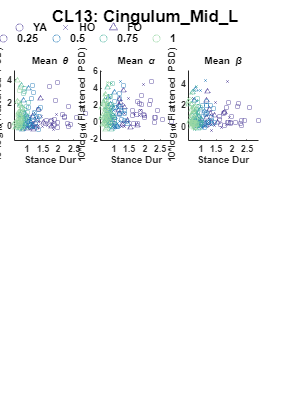

##13-theta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F        pValue 
                                    ____________    ___    ___________    ________    _______

    group_char                          2.8065        2       1.4033        1.8244    0.16425
    mean_GaitCycleDur                 0.013913        1     0.013913      0.018089    0.89316
    group_char:mean_GaitCycleDur       0.47044        2      0.23522       0.30582     0.7369
    Error                               139.99      182      0.76915                         
    Total                               155.59      187                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate      SE        tStat       pValue  
                                            ________    _______    _______    __________

    (Intercept)                               1.2025    0.28552     4.2115    3.9841e-05
    group_char_H2000's                      -0.91323    0.56153    -1.6263       0.10561
    group_char_H3000's                      -0.84928    0.62896    -1.3503        0.1786
    mean_GaitCycleDur                       -0.12561    0.14977    -0.8387       0.40274
    group_char_H2000's:mean_GaitCycleDur     0.13117    0.34525    0.37992       0.70445
    group_char_H3000's:mean_GaitCycleDur</

##13-alpha_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F        pValue 
                                    ____________    ___    ___________    _______    ________

    group_char                         8.8203         2       4.4102       2.7135    0.068989
    mean_GaitCycleDur                 0.49296         1      0.49296      0.30331     0.58249
    group_char:mean_GaitCycleDur       7.2368         2       3.6184       2.2263     0.11086
    Error                               295.8       182       1.6253                         
    Total                              308.32       187                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate       SE         tStat       pValue  
                                            _________    _______    _________    _________

    (Intercept)                                1.2632    0.41504       3.0436    0.0026836
    group_char_H2000's                        -1.7671    0.81627      -2.1649     0.031701
    group_char_H3000's                         0.3086    0.91428      0.33754       0.7361
    mean_GaitCycleDur                       -0.021362    0.21771    -0.098122      0.92194
    group_char_H2000's:mean_GaitCycleDur      0.93406    0.50187       1.8612     0.064332
    group_char_H3000's:mean_

##13-beta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F        pValue 
                                    ____________    ___    ___________    ________    _______

    group_char                         0.19407        2     0.097037        0.1096    0.89625
    mean_GaitCycleDur                 0.019551        1     0.019551      0.022083    0.88203
    group_char:mean_GaitCycleDur       0.10824        2      0.05412      0.061128    0.94072
    Error                               161.14      182      0.88536                         
    Total                               161.78      187                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate      SE        tStat       pValue  
                                            ________    _______    ________    _________

    (Intercept)                              0.83077    0.30633       2.712    0.0073283
    group_char_H2000's                      0.090863    0.60246     0.15082      0.88029
    group_char_H3000's                       0.31451     0.6748     0.46608      0.64172
    mean_GaitCycleDur                       0.016869    0.16068     0.10498      0.91651
    group_char_H2000's:mean_GaitCycleDur    0.019503    0.37041    0.052651      0.95807
    group_char_H3000's:mean_GaitCycleDur

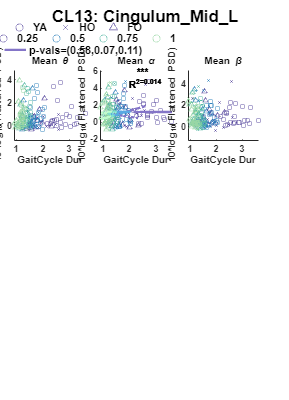

##13-theta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F        pValue 
                                          ____________    ___    ___________    ________    _______

    group_char                                3.5188        2       1.7594        2.2786    0.10534
    mean_PeakUpDownVel_mean                 0.092302        1     0.092302       0.11954    0.72993
    group_char:mean_PeakUpDownVel_mean       0.10651        2     0.053254      0.068969    0.93338
    Error                                     140.53      182      0.77214                         
    Total                                     155.59      187                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate       SE         tStat        pValue  
                                                  _________    _______    _________    __________

    (Intercept)                                     0.96568    0.22298       4.3309    2.4499e-05
    group_char_H2000's                             -0.79458    0.37454      -2.1215      0.035234
    group_char_H3000's                             -0.36236    0.36486     -0.99315       0.32195
    mean_PeakUpDownVel_mean                        0.043868    0.84348     0.052008       0.95858
    group_char_H2000's:mean_PeakUpDownVel_mean      0.45248     1.3633      0.3

##13-alpha_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F       pValue 
                                          ____________    ___    ___________    _______    _______

    group_char                               1.5014         2      0.75069      0.45411    0.63573
    mean_PeakUpDownVel_mean                 0.74535         1      0.74535      0.45087    0.50277
    group_char:mean_PeakUpDownVel_mean       1.7438         2      0.87188      0.52741    0.59103
    Error                                    300.87       182       1.6531                        
    Total                                    308.32       187                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate       SE         tStat        pValue  
                                                  _________    _______    _________    __________

    (Intercept)                                      1.2231    0.32626       3.7488    0.00023852
    group_char_H2000's                             -0.37162    0.54802     -0.67811       0.49856
    group_char_H3000's                              0.20127    0.53386        0.377       0.70661
    mean_PeakUpDownVel_mean                       0.0070082     1.2342    0.0056784       0.99548
    group_char_H2000's:mean_PeakUpDownVel_mean     0.047534     1.9948     0.02

##13-beta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares      F        pValue 
                                          ____________    ___    ___________    ______    ________

    group_char                               1.7656         2      0.88282      1.0165     0.36389
    mean_PeakUpDownVel_mean                  2.5573         1       2.5573      2.9446    0.087865
    group_char:mean_PeakUpDownVel_mean       1.1304         2      0.56519      0.6508     0.52284
    Error                                    158.06       182      0.86845                        
    Total                                    161.78       187                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat        pValue  
                                                  ________    _______    ________    __________

    (Intercept)                                    0.89432    0.23647      3.7819    0.00021092
    group_char_H2000's                              0.5199    0.39721      1.3089       0.19222
    group_char_H3000's                             0.38813    0.38694      1.0031       0.31716
    mean_PeakUpDownVel_mean                       -0.13824    0.89454    -0.15454       0.87735
    group_char_H2000's:mean_PeakUpDownVel_mean     -1.5809     1.4459     -1.0934       0.27

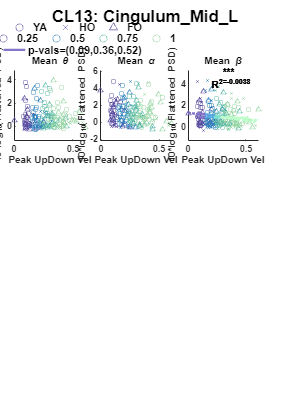

##14-theta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                      1.5464         2       0.7732       0.8398     0.43319
    mean_APexc_COV                  3.4249         1       3.4249       3.7199    0.055066
    group_char:mean_APexc_COV       0.7305         2      0.36525      0.39671     0.67301
    Error                           200.71       218       0.9207                         
    Total                           243.72       223                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat      pValue 
                                         _________    ________    ________    _______

    (Intercept)                            0.53056     0.41376      1.2823     0.2011
    group_char_H2000's                    -0.43496     0.67994    -0.63971    0.52303
    group_char_H3000's                    -0.74463     0.57573     -1.2934    0.19725
    mean_APexc_COV                        0.041106    0.025375      1.6199     0.1067
    group_char_H2000's:mean_APexc_COV     -0.03102    0.035007    -0.88611    0.37654
    group_char_H3000's:mean_APexc_COV    -0.018422    0.0

##14-alpha_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                       8.8517        2       4.4258        1.234    0.29315
    mean_APexc_COV                 0.072878        1     0.072878      0.02032    0.88678
    group_char:mean_APexc_COV        10.441        2       5.2203       1.4555    0.23554
    Error                            781.87      218       3.5866                        
    Total                            794.85      223                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat      pValue  
                                         _________    ________    _______    _________

    (Intercept)                             2.2866     0.81663     2.8001    0.0055673
    group_char_H2000's                     -1.7061       1.342    -1.2713      0.20497
    group_char_H3000's                     -1.5749      1.1363     -1.386      0.16718
    mean_APexc_COV                       -0.069032    0.050084    -1.3783      0.16951
    group_char_H2000's:mean_APexc_COV      0.10763    0.069093     1.5578      0.12073
    group_char_H3000's:mean_APexc_COV     0.088687

##14-beta_avg_power) mean_APexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      7.0311         2       3.5156       1.3054    0.27317
    mean_APexc_COV                 0.67895         1      0.67895      0.25211     0.6161
    group_char:mean_APexc_COV       12.309         2       6.1547       2.2854    0.10416
    Error                           587.08       218        2.693                        
    Total                           671.32       223                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             2.6618     0.70763      3.7616    0.00021694
    group_char_H2000's                      -1.681      1.1629     -1.4456       0.14973
    group_char_H3000's                    0.016752     0.98465    0.017013       0.98644
    mean_APexc_COV                       -0.080387    0.043399     -1.8523      0.065336
    group_char_H2000's:mean_APexc_COV       0.1255    0.059871      2.0962      0.037219
    group_char_H3000's:mean_APexc_COV

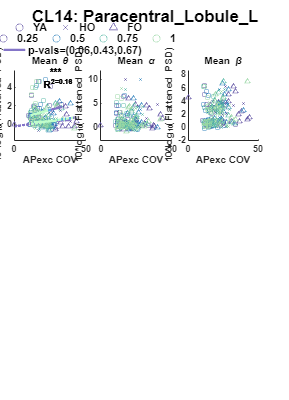

##14-theta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                       2.8557         2       1.4279       1.5282    0.21924
    mean_APexc_mean                 0.38741         1      0.38741      0.41463     0.5203
    group_char:mean_APexc_mean       1.0658         2      0.53291      0.57036    0.56616
    Error                            203.69       218      0.93434                        
    Total                            243.72       223                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                             1.2235    0.38307       3.194    0.0016108
    group_char_H2000's                    -0.98295    0.56473     -1.7406      0.08317
    group_char_H3000's                    -0.51994    0.48828     -1.0649      0.28812
    mean_APexc_mean                       -0.79133     6.7063      -0.118      0.90618
    group_char_H2000's:mean_APexc_mean      2.4243     10.937     0.22166      0.82478
    group_char_H3000's:mean_APexc_mean     -8.521

##14-alpha_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares      F       pValue 
                                  ____________    ___    ___________    ______    _______

    group_char                       13.763         2      6.8813       1.9249    0.14836
    mean_APexc_mean                  3.5778         1      3.5778       1.0008    0.31823
    group_char:mean_APexc_mean       11.479         2      5.7393       1.6055    0.20316
    Error                            779.33       218      3.5749                        
    Total                            794.85       223                                    



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE         tStat      pValue 
                                          ________    _______    _________    _______

    (Intercept)                             1.2231    0.74931       1.6324    0.10405
    group_char_H2000's                      1.6505     1.1046       1.4942    0.13657
    group_char_H3000's                    -0.26885    0.95509     -0.28149     0.7786
    mean_APexc_mean                        -0.4935     13.118    -0.037621    0.97002
    group_char_H2000's:mean_APexc_mean     -31.088     21.393      -1.4532    0.14761
    group_char_H3000's:mean_APexc_mean      6.8258     1

##14-beta_avg_power) mean_APexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    ________    _______

    group_char                       9.8351         2       4.9176        1.7948    0.16861
    mean_APexc_mean                 0.23567         1      0.23567      0.086014    0.76959
    group_char:mean_APexc_mean       2.2287         2       1.1144       0.40671    0.66634
    Error                             597.3       218       2.7399                         
    Total                            671.32       223                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_APexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue 
                                          ________    _______    ________    ________

    (Intercept)                            1.1609     0.65599      1.7697    0.078167
    group_char_H2000's                     1.3644     0.96706      1.4108     0.15972
    group_char_H3000's                      1.523     0.83615      1.8214    0.069913
    mean_APexc_mean                        4.1959      11.484     0.36537     0.71519
    group_char_H2000's:mean_APexc_mean    -16.393      18.729    -0.87529     0.38238
    group_char_H3000's:mean_APexc_mean    -2.8016      16

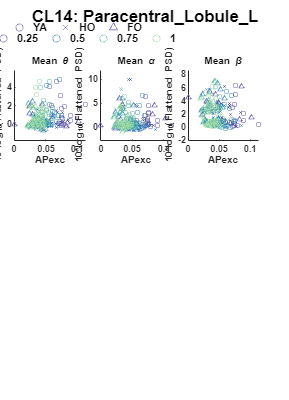

##14-theta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F         pValue 
                                 ____________    ___    ___________    ________    ________

    group_char                       3.9619        2        1.981        2.1462     0.11939
    mean_MLexc_COV                   3.8872        1       3.8872        4.2116    0.041344
    group_char:mean_MLexc_COV      0.058492        2     0.029246      0.031686     0.96882
    Error                            201.21      218      0.92299                          
    Total                            243.72      223                                       



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                          Estimate        SE        tStat       pValue 
                                         __________    ________    ________    ________

    (Intercept)                             0.78572     0.32125      2.4459    0.015243
    group_char_H2000's                     -0.89825     0.46745     -1.9216     0.05596
    group_char_H3000's                     -0.75004     0.47506     -1.5788     0.11582
    mean_MLexc_COV                         0.028463    0.021981      1.2949     0.19673
    group_char_H2000's:mean_MLexc_COV      0.003787     0.03249     0.11656     0.90732
    group_char_H3000's:mean_MLexc_COV    -0

##14-alpha_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      3.8529         2      1.9264       0.53566    0.58605
    mean_MLexc_COV                  2.0819         1      2.0819       0.57889    0.44757
    group_char:mean_MLexc_COV       5.7087         2      2.8543       0.79366    0.45349
    Error                           784.02       218      3.5964                         
    Total                           794.85       223                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue  
                                         _________    ________    ________    _________

    (Intercept)                             2.1064     0.63412      3.3218    0.0010486
    group_char_H2000's                     -0.8258     0.92271    -0.89497      0.37179
    group_char_H3000's                    -0.82175     0.93774    -0.87631      0.38183
    mean_MLexc_COV                       -0.065725    0.043389     -1.5148      0.13128
    group_char_H2000's:mean_MLexc_COV     0.076419    0.064133      1.1916      0.23473
    group_char_H3000's:mean_MLexc_COV     0

##14-beta_avg_power) mean_MLexc_COV


                                 SumOfSquares    DF     MeanSquares       F         pValue 
                                 ____________    ___    ___________    ________    ________

    group_char                      6.1743         2       3.0872        1.1434     0.32065
    mean_MLexc_COV                  10.327         1       10.327        3.8247    0.051779
    group_char:mean_MLexc_COV      0.41966         2      0.20983      0.077713     0.92526
    Error                           588.62       218       2.7001                          
    Total                           671.32       223                                       



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             1.9957     0.54945      3.6321    0.00035044
    group_char_H2000's                     0.74332      0.7995     0.92973       0.35354
    group_char_H3000's                      1.2091     0.81252      1.4881       0.13818
    mean_MLexc_COV                       -0.043595    0.037596     -1.1596       0.24749
    group_char_H2000's:mean_MLexc_COV    -0.014714     0.05557    -0.26479       0.79142
    group_char_H3000's:mean_MLexc_COV

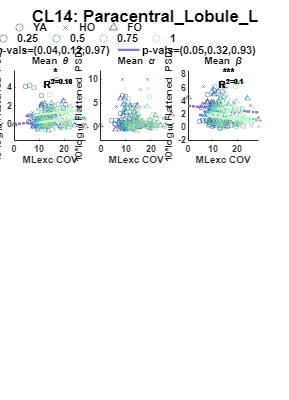

##14-theta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    ________    _______

    group_char                       0.99619        2      0.49809       0.53299    0.58761
    mean_MLexc_mean                 0.016004        1     0.016004      0.017125    0.89601
    group_char:mean_MLexc_mean        1.5181        2      0.75904       0.81221    0.44521
    Error                             203.73      218      0.93453                         
    Total                             243.72      223                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue  
                                          ________    _______    ________    _________

    (Intercept)                            0.86054    0.31846      2.7022    0.0074311
    group_char_H2000's                    -0.38181    0.45105     -0.8465       0.3982
    group_char_H3000's                    -0.40154    0.42217    -0.95115      0.34258
    mean_MLexc_mean                         3.7832     3.5685      1.0602      0.29024
    group_char_H2000's:mean_MLexc_mean     -5.5225     4.7617     -1.1598      0.24741
    group_char_H3000's:mean_MLexc_mean     -5.094

##14-alpha_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                       7.7593         2       3.8796       1.0758    0.34283
    mean_MLexc_mean                 0.49369         1      0.49369       0.1369    0.71175
    group_char:mean_MLexc_mean       6.0166         2       3.0083      0.83416    0.43562
    Error                            786.19       218       3.6064                        
    Total                            794.85       223                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue 
                                          ________    _______    ________    ________

    (Intercept)                              1.317     0.6256      2.1051    0.036424
    group_char_H2000's                     0.74144    0.88605     0.83679     0.40363
    group_char_H3000's                    -0.47598    0.82932    -0.57394      0.5666
    mean_MLexc_mean                        -1.4327       7.01    -0.20438     0.83825
    group_char_H2000's:mean_MLexc_mean      -5.347     9.3541    -0.57162     0.56817
    group_char_H3000's:mean_MLexc_mean      5.5778     9

##14-beta_avg_power) mean_MLexc_mean


                                  SumOfSquares    DF     MeanSquares       F         pValue 
                                  ____________    ___    ___________    ________    ________

    group_char                        15.59         2       7.7948        2.8414    0.060508
    mean_MLexc_mean                 0.18423         1      0.18423      0.067157     0.79577
    group_char:mean_MLexc_mean       1.2392         2       0.6196       0.22586     0.79802
    Error                            598.04       218       2.7433                          
    Total                            671.32       223                                       



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_MLexc_mean

Estimated Coefficients:
                                          Estimate      SE         tStat       pValue 
                                          ________    _______    _________    ________

    (Intercept)                             1.4073    0.54563       2.5792     0.01056
    group_char_H2000's                     0.43937    0.77279      0.56855     0.57025
    group_char_H3000's                      1.6363    0.72331       2.2622    0.024671
    mean_MLexc_mean                       -0.18364      6.114    -0.030036     0.97607
    group_char_H2000's:mean_MLexc_mean      1.4444     8.1584      0.17705     0.85964
    group_char_H3000's:mean_MLexc_mean     -3.3781

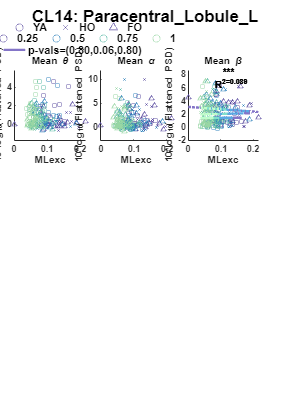

##14-theta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F       pValue 
                               ____________    ___    ___________    _______    _______

    group_char                    2.2739         2       1.1369       1.2199    0.29726
    mean_StepDur                  1.5696         1       1.5696       1.6842    0.19574
    group_char:mean_StepDur       1.1844         2      0.59219      0.63541     0.5307
    Error                         203.17       218      0.93198                        
    Total                         243.72       223                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate       SE         tStat        pValue  
                                       _________    _______    _________    __________

    (Intercept)                           1.2832    0.30658       4.1856    4.1257e-05
    group_char_H2000's                  -0.84667    0.54356      -1.5576       0.12077
    group_char_H3000's                  -0.32884    0.53822     -0.61097       0.54185
    mean_StepDur                        -0.11257    0.31496      -0.3574       0.72114
    group_char_H2000's:mean_StepDur    -0.042692    0.63823    -0.066891       0.94673
    group_char_H3000's:mean_StepDur      -0.7831    

##14-alpha_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F        pValue 
                               ____________    ___    ___________    ________    _______

    group_char                    3.6398         2       1.8199       0.50215    0.60592
    mean_StepDur                 0.11425         1      0.11425      0.031523    0.85924
    group_char:mean_StepDur       2.3959         2       1.1979       0.33054    0.71889
    Error                         790.08       218       3.6242                         
    Total                         794.85       223                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate      SE        tStat      pValue 
                                       ________    _______    ________    _______

    (Intercept)                          0.9291    0.60456      1.5368    0.12579
    group_char_H2000's                   1.0616     1.0719     0.99037    0.32309
    group_char_H3000's                   0.1837     1.0614     0.17308    0.86275
    mean_StepDur                        0.29108     0.6211     0.46866    0.63978
    group_char_H2000's:mean_StepDur     -1.0205     1.2586    -0.81082    0.41835
    group_char_H3000's:mean_StepDur    -0.16667     1.3883    -0.12005    0.90455


Num

##14-beta_avg_power) mean_StepDur


                               SumOfSquares    DF     MeanSquares       F       pValue 
                               ____________    ___    ___________    _______    _______

    group_char                    6.0857         2       3.0428       1.1128     0.3305
    mean_StepDur                  1.0809         1       1.0809      0.39527     0.5302
    group_char:mean_StepDur       1.9383         2      0.96917      0.35443    0.70197
    Error                         596.11       218       2.7344                        
    Total                         671.32       223                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StepDur

Estimated Coefficients:
                                       Estimate      SE        tStat       pValue 
                                       ________    _______    ________    ________

    (Intercept)                           1.044    0.52513      1.9881    0.048047
    group_char_H2000's                   1.1532    0.93107      1.2386     0.21684
    group_char_H3000's                   1.0929    0.92192      1.1854     0.23714
    mean_StepDur                        0.37927     0.5395       0.703     0.48281
    group_char_H2000's:mean_StepDur    -0.67755     1.0932    -0.61978     0.53605
    group_char_H3000's:mean_StepDur     0.50524     1.2059     0.41896     0.6756

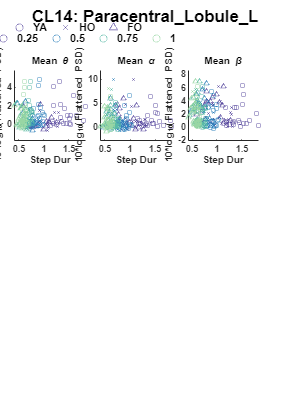

##14-theta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                       4.752         2        2.376       2.5382    0.081341
    mean_UDexc_COV                 0.73408         1      0.73408       0.7842     0.37684
    group_char:mean_UDexc_COV      0.39586         2      0.19793      0.21144     0.80958
    Error                           204.07       218      0.93609                         
    Total                           243.72       223                                      



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                          Estimate        SE        tStat        pValue  
                                         __________    ________    ________    __________

    (Intercept)                             0.98066      0.2635      3.7216    0.00025192
    group_char_H2000's                      -0.6579     0.40026     -1.6437       0.10168
    group_char_H3000's                     -0.85981     0.41129     -2.0905      0.037733
    mean_UDexc_COV                          0.01599     0.01945     0.82209       0.41192
    group_char_H2000's:mean_UDexc_COV     -0.016546    0.028977    -0.57099       0.56859
    group_char_H3000's:mean_UDexc_COV<

##14-alpha_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                     0.47948         2      0.23974      0.06659     0.9356
    mean_UDexc_COV                  7.0151         1       7.0151       1.9485    0.16417
    group_char:mean_UDexc_COV      0.74333         2      0.37167      0.10323    0.90196
    Error                           784.86       218       3.6003                        
    Total                           794.85       223                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat       pValue  
                                         _________    ________    ________    _________

    (Intercept)                             1.5572     0.51676      3.0134    0.0028893
    group_char_H2000's                     0.14807     0.78496     0.18863      0.85056
    group_char_H3000's                     0.29265     0.80661     0.36282      0.71709
    mean_UDexc_COV                       -0.028974    0.038144     -0.7596      0.44832
    group_char_H2000's:mean_UDexc_COV      0.00697    0.056829     0.12265       0.9025
    group_char_H3000's:mean_UDexc_COV    -0

##14-beta_avg_power) mean_UDexc_COV


                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    group_char                       16.42         2       8.2099       3.0616    0.048829
    mean_UDexc_COV                  14.696         1       14.696       5.4804    0.020134
    group_char:mean_UDexc_COV       0.8507         2      0.42535      0.15862     0.85342
    Error                           584.58       218       2.6815                         
    Total                           671.32       223                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_COV

Estimated Coefficients:
                                         Estimate        SE        tStat        pValue  
                                         _________    ________    ________    __________

    (Intercept)                             1.7928     0.44598        4.02    8.0184e-05
    group_char_H2000's                     0.87546     0.67744      1.2923       0.19762
    group_char_H3000's                      1.7114     0.69612      2.4584      0.014734
    mean_UDexc_COV                        -0.03217    0.032919    -0.97724       0.32953
    group_char_H2000's:mean_UDexc_COV    -0.022583    0.049045    -0.46046       0.64564
    group_char_H3000's:mean_UDexc_COV

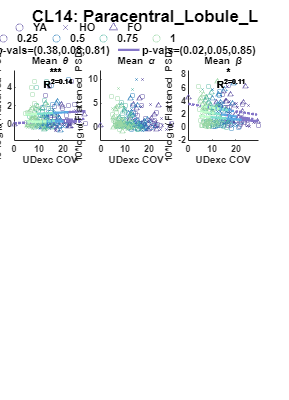

##14-theta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F         pValue  
                                  ____________    ___    ___________    ________    _________

    group_char                        10.907        2       5.4534         5.852    0.0033448
    mean_UDexc_mean                 0.032608        1     0.032608      0.034991      0.85179
    group_char:mean_UDexc_mean         2.041        2       1.0205        1.0951      0.33633
    Error                             203.15      218      0.93188                           
    Total                             243.72      223                                        



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat        pValue  
                                          ________    _______    ________    __________

    (Intercept)                             1.4404    0.29095      4.9506    1.4802e-06
    group_char_H2000's                     -1.4436    0.43677     -3.3053     0.0011092
    group_char_H3000's                    -0.96422    0.41472      -2.325      0.020993
    mean_UDexc_mean                        -10.832     11.322    -0.95674       0.33976
    group_char_H2000's:mean_UDexc_mean      23.423     16.459      1.4231       0.15614
    group_char_H3000's:mean_UDexc_mean    

##14-alpha_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F       pValue 
                                  ____________    ___    ___________    _______    _______

    group_char                        6.244         2       3.122       0.86546     0.4223
    mean_UDexc_mean                  1.5958         1      1.5958       0.44238    0.50668
    group_char:mean_UDexc_mean       4.6287         2      2.3144       0.64157    0.52745
    Error                            786.39       218      3.6073                         
    Total                            794.85       223                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue 
                                          ________    _______    ________    ________

    (Intercept)                             1.4612    0.57243      2.5527    0.011373
    group_char_H2000's                     0.62178    0.85933     0.72356     0.47011
    group_char_H3000's                    -0.51675    0.81596     -0.6333      0.5272
    mean_UDexc_mean                        -11.035     22.275    -0.49539     0.62082
    group_char_H2000's:mean_UDexc_mean     -15.041     32.384    -0.46446     0.64278
    group_char_H3000's:mean_UDexc_mean      21.791      

##14-beta_avg_power) mean_UDexc_mean


                                  SumOfSquares    DF     MeanSquares       F        pValue 
                                  ____________    ___    ___________    _______    ________

    group_char                       16.897         2       8.4486       3.0825    0.047846
    mean_UDexc_mean                 0.68504         1      0.68504      0.24994     0.61762
    group_char:mean_UDexc_mean       1.4579         2      0.72895      0.26596     0.76672
    Error                            597.49       218       2.7408                         
    Total                            671.32       223                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_UDexc_mean

Estimated Coefficients:
                                          Estimate      SE        tStat       pValue 
                                          ________    _______    ________    ________

    (Intercept)                            1.2484     0.49897       2.502    0.013082
    group_char_H2000's                     1.0141     0.74905      1.3539     0.17717
    group_char_H3000's                     1.7588     0.71124      2.4728     0.01417
    mean_UDexc_mean                        5.9637      19.416     0.30715     0.75902
    group_char_H2000's:mean_UDexc_mean    -17.717      28.227    -0.62766     0.53089
    group_char_H3000's:mean_UDexc_mean    -17.442      27

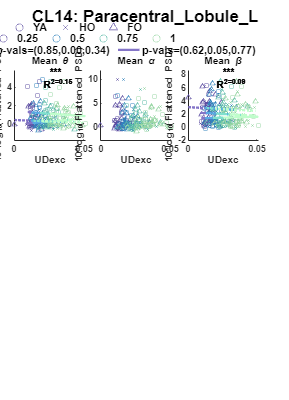

##14-theta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                       3.576         2        1.788       1.9145    0.14988
    mean_StanceDur                  1.2375         1       1.2375        1.325    0.25095
    group_char:mean_StanceDur       1.0259         2      0.51295      0.54923    0.57819
    Error                            203.6       218      0.93393                        
    Total                           243.72       223                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate       SE         tStat        pValue  
                                         _________    _______    _________    __________

    (Intercept)                             1.2475    0.25525       4.8872    1.9811e-06
    group_char_H2000's                    -0.85833    0.44657       -1.922      0.055905
    group_char_H3000's                    -0.43917    0.45633      -0.9624       0.33691
    mean_StanceDur                       -0.053942     0.1867     -0.28893       0.77291
    group_char_H2000's:mean_StanceDur    -0.015416    0.37594    -0.041007       0.96733
    group_char_H3000's:mean_StanceDur

##14-alpha_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares        F        pValue 
                                 ____________    ___    ___________    _________    _______

    group_char                       4.4435        2       2.2217        0.61337    0.54245
    mean_StanceDur                 0.016921        1     0.016921      0.0046715    0.94557
    group_char:mean_StanceDur        2.8539        2       1.4269        0.39395    0.67487
    Error                            789.64      218       3.6222                          
    Total                            794.85      223                                       



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate       SE        tStat       pValue 
                                         _________    _______    ________    ________

    (Intercept)                             1.0293    0.50269      2.0476    0.041799
    group_char_H2000's                     0.89555    0.87946      1.0183     0.30967
    group_char_H3000's                   -0.078419    0.89868    -0.08726     0.93055
    mean_StanceDur                         0.13326    0.36768     0.36243     0.71738
    group_char_H2000's:mean_StanceDur       -0.607    0.74037    -0.81986     0.41319
    group_char_H3000's:mean_StanceDur      0.13417     0.

##14-beta_avg_power) mean_StanceDur


                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    group_char                      8.2908         2      4.1454        1.5166    0.22177
    mean_StanceDur                  1.0323         1      1.0323       0.37767    0.53949
    group_char:mean_StanceDur       2.3236         2      1.1618       0.42504    0.65428
    Error                           595.89       218      2.7334                         
    Total                           671.32       223                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_StanceDur

Estimated Coefficients:
                                         Estimate      SE        tStat       pValue 
                                         ________    _______    ________    ________

    (Intercept)                            1.1132    0.43668      2.5493    0.011482
    group_char_H2000's                     1.0808    0.76399      1.4146      0.1586
    group_char_H3000's                     1.1045    0.78068      1.4148     0.15855
    mean_StanceDur                        0.22269     0.3194      0.6972     0.48642
    group_char_H2000's:mean_StanceDur    -0.43877    0.64316    -0.68222     0.49583
    group_char_H3000's:mean_StanceDur     0.34137    0.74204     

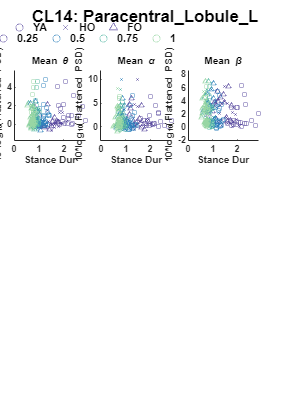

##14-theta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F       pValue 
                                    ____________    ___    ___________    _______    _______

    group_char                         2.3141         2        1.157       1.2415    0.29099
    mean_GaitCycleDur                  1.5616         1       1.5616       1.6755    0.19689
    group_char:mean_GaitCycleDur       1.1828         2      0.59141      0.63456    0.53114
    Error                              203.18       218        0.932                        
    Total                              243.72       223                                     



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate       SE        tStat        pValue  
                                            _________    _______    ________    __________

    (Intercept)                                1.2845    0.30639      4.1924    4.0125e-05
    group_char_H2000's                       -0.85227    0.54231     -1.5715       0.11751
    group_char_H3000's                       -0.33055     0.5381    -0.61429       0.53966
    mean_GaitCycleDur                       -0.056966    0.15729    -0.36216       0.71758
    group_char_H2000's:mean_GaitCycleDur    -0.017867    0.31808    -0.05617       0.95526
    group_char_H3000's:mean_

##14-alpha_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F        pValue 
                                    ____________    ___    ___________    ________    _______

    group_char                          3.669         2       1.8345       0.50619     0.6035
    mean_GaitCycleDur                 0.11609         1      0.11609      0.032033    0.85812
    group_char:mean_GaitCycleDur        2.419         2       1.2095       0.33373    0.71661
    Error                              790.05       218       3.6241                         
    Total                              794.85       223                                      



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate       SE        tStat      pValue 
                                            _________    _______    ________    _______

    (Intercept)                               0.92923    0.60418       1.538     0.1255
    group_char_H2000's                         1.0631     1.0694     0.99414    0.32126
    group_char_H3000's                        0.18347     1.0611      0.1729    0.86289
    mean_GaitCycleDur                          0.1454    0.31017     0.46876    0.63971
    group_char_H2000's:mean_GaitCycleDur     -0.51098    0.62724    -0.81464    0.41617
    group_char_H3000's:mean_GaitCycleDur

##14-beta_avg_power) mean_GaitCycleDur


                                    SumOfSquares    DF     MeanSquares       F       pValue 
                                    ____________    ___    ___________    _______    _______

    group_char                         6.1505         2       3.0752       1.1246    0.32665
    mean_GaitCycleDur                  1.0643         1       1.0643      0.38921    0.53337
    group_char:mean_GaitCycleDur       1.9497         2      0.97486      0.35651    0.70052
    Error                              596.11       218       2.7344                        
    Total                              671.32       223                                     



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_GaitCycleDur

Estimated Coefficients:
                                            Estimate      SE        tStat       pValue 
                                            ________    _______    ________    ________

    (Intercept)                                1.043    0.52481      1.9874    0.048126
    group_char_H2000's                        1.1576    0.92892      1.2462     0.21402
    group_char_H3000's                        1.0977    0.92171      1.1909     0.23498
    mean_GaitCycleDur                         0.1901    0.26943     0.70556     0.48122
    group_char_H2000's:mean_GaitCycleDur    -0.34136    0.54484    -0.62654     0.53162
    group_char_H3000's:mean_GaitCycleDur 

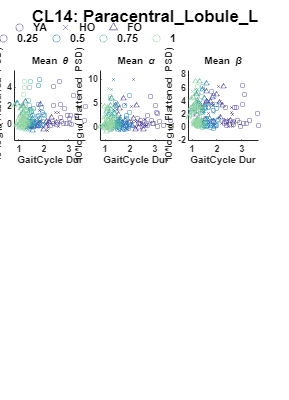

##14-theta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F        pValue  
                                          ____________    ___    ___________    _______    _________

    group_char                               12.089         2       6.0443       6.4512    0.0018969
    mean_PeakUpDownVel_mean                 0.16634         1      0.16634      0.17754      0.67391
    group_char:mean_PeakUpDownVel_mean      0.85604         2      0.42802      0.45684      0.63389
    Error                                    204.25       218      0.93692                          
    Total                                    243.72       223                                       



Linear regression model:
    theta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat        pValue  
                                                  ________    _______    ________    __________

    (Intercept)                                     1.2964    0.24343      5.3256    2.4993e-07
    group_char_H2000's                               -1.17    0.37398     -3.1285      0.001997
    group_char_H3000's                             -1.0707    0.36227     -2.9555     0.0034653
    mean_PeakUpDownVel_mean                       -0.48825    0.92491    -0.52789       0.59811
    group_char_H2000's:mean_PeakUpDownVel_mean      1.1898     1.3274     0.89631       0.3

##14-alpha_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F       pValue 
                                          ____________    ___    ___________    _______    _______

    group_char                               1.7222         2      0.86109      0.23742    0.78886
    mean_PeakUpDownVel_mean                 0.79058         1      0.79058      0.21798    0.64105
    group_char:mean_PeakUpDownVel_mean       1.0275         2      0.51374      0.14165    0.86801
    Error                                    790.65       218       3.6268                        
    Total                                    794.85       223                                     



Linear regression model:
    alpha_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE        tStat       pValue  
                                                  ________    _______    ________    _________

    (Intercept)                                     1.4328    0.47894      2.9915    0.0030954
    group_char_H2000's                             0.21051    0.73581     0.28609      0.77508
    group_char_H3000's                            -0.31264    0.71277    -0.43863      0.66137
    mean_PeakUpDownVel_mean                       -0.99323     1.8198    -0.54581      0.58576
    group_char_H2000's:mean_PeakUpDownVel_mean     0.17522     2.6116    0.067092      0.94657
  

##14-beta_avg_power) mean_PeakUpDownVel_mean


                                          SumOfSquares    DF     MeanSquares       F        pValue 
                                          ____________    ___    ___________    ________    _______

    group_char                               16.343         2       8.1716        2.9786    0.05294
    mean_PeakUpDownVel_mean                  1.2527         1       1.2527       0.45661    0.49993
    group_char:mean_PeakUpDownVel_mean      0.26213         2      0.13106      0.047773    0.95336
    Error                                    598.08       218       2.7435                         
    Total                                    671.32       223                                      



Linear regression model:
    beta_avg_power ~ 1 + group_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                                  Estimate      SE         tStat         pValue  
                                                  ________    _______    __________    __________

    (Intercept)                                      1.491    0.41655        3.5794    0.00042448
    group_char_H2000's                             0.59147    0.63996       0.92424       0.35639
    group_char_H3000's                              1.5099    0.61992        2.4357      0.015667
    mean_PeakUpDownVel_mean                       -0.41615     1.5827      -0.26294       0.79285
    group_char_H2000's:mean_PeakUpDownVel_mean    -0.01963     2.2714    -0.0086

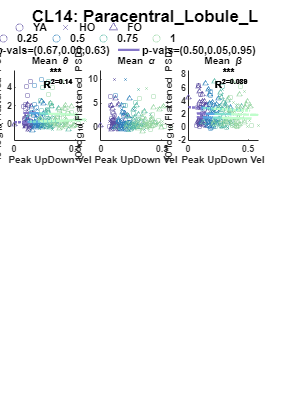

for cl_i = 1:length(clusters)
    %##
    for var_i = 1:length(varnames)
        %%
        atlas_name = atlas_name_store{cl_i};
        fig = figure('color','white','renderer','Painters');
        sgtitle(atlas_name,'FontName',PLOT_STRUCT.font_name,'FontSize',14,'FontWeight','bold','Interpreter','none');
        set(fig,'Units','inches','Position',[0.5,0.5,6.5,9])
        set(fig,'PaperUnits','inches','PaperSize',[1 1],'PaperPosition',[0 0 1 1])
        hold on;
        set(gca,AXES_DEFAULT_PROPS{:})
        vert_shift = 0;
        for des_i = 2
            switch des_i
                case 1
                    color_dark = COLORS_MAPS_TERRAIN;
                    color_light = COLORS_MAPS_TERRAIN;
                    GROUP_CMAP_OFFSET = [0,0.1,0.1];
                    xtick_label_g = {'flat','low','med','high'};
                case 2
                    color_dark = COLOR_MAPS_SPEED;
                    color_light = COLOR_MAPS_SPEED+0.15;
                    GROUP_CMAP_OFFSET = [0.15,0,0];
                    xtick_label_g = {'0.25','0.50','0.75','1.0'};
            end
            horiz_shift = 0;
            stats_store = [];
            cond_plot_store = [];
            for meas_i = 1:length(measure_name_plot)
                measure_name = measure_name_plot{meas_i};
                %##
                group_plot_store = [];
                % inds = psd_feature_stats.study == num2str(des_i) & psd_feature_stats.cluster == num2str(cl_i) & psd_feature_stats.group==groups(group_i);
                % T_stats_plot = psd_feature_stats(inds,:);
                inds = TMP_FOOOF_T.design_id == designs(des_i) & TMP_FOOOF_T.cluster_id == clusters(cl_i);
                T_vals_plot = TMP_FOOOF_T(inds,:);
                %- continuous or categorical
                % T_vals_plot.cond_char = double(string(T_vals_plot.cond_char));
                %-
                loc_cond_chars = unique(T_vals_plot.cond_char);
                y_lim_calc = [min(T_vals_plot.(measure_name))-std(T_vals_plot.(measure_name)),max(T_vals_plot.(measure_name))+std(T_vals_plot.(measure_name))];
                x_txt = min(T_vals_plot.(varnames{var_i}))*REGRESS_TXT_XMULTI+std(T_vals_plot.(varnames{var_i}));
                y_txt = max(T_vals_plot.(measure_name))*REGRESS_TXT_YMULTI+std(T_vals_plot.(measure_name));
                try
                    mod = sprintf('%s ~ 1 + %s + group_char + %s*group_char',measure_name,varnames{var_i},varnames{var_i});
                    stats_out = fitlm(T_vals_plot,mod);
                    % anova_out = anova(stats_out);
                    anova_out = anova(T_vals_plot,mod,'SumOfSquaresType',"three",'CategoricalFactors',{'group_char'},...
                        'ModelSpecification','linear');
                    anova_out = anova_out.stats();
                    % anova_out = anovan(double(T_vals_plot.(measure_name)),{T_vals_plot.group_char,double(T_vals_plot.(varnames{var_i}))},...
                    %     'continuous',[2],...
                    %     'model','interaction',...
                    %     'model',2,...
                    %     'sstype',3,...
                    %     'varnames',strvcat('group',varnames{var_i}));
                
                    R2 = stats_out.Rsquared.Adjusted;
                    anova_p_var = anova_out.pValue(strcmp(anova_out.Properties.RowNames,varnames{var_i}));
                    anova_p_grp = anova_out.pValue(strcmp(anova_out.Properties.RowNames,'group_char'));
                    anova_p_inter = anova_out.pValue(strcmp(anova_out.Properties.RowNames,sprintf('group_char:%s',varnames{var_i})));
                    
                    pval_var = stats_out.Coefficients.pValue(strcmp(stats_out.Coefficients.Properties.RowNames,varnames{var_i}));
                    pval_grp2 = double(stats_out.Coefficients.pValue(strcmp(stats_out.Coefficients.Properties.RowNames,'group_char_H2000''s')));
                    pval_grp3 = double(stats_out.Coefficients.pValue(strcmp(stats_out.Coefficients.Properties.RowNames,'group_char_H3000''s')));
                    pval_var_grp2 = double(stats_out.Coefficients.pValue(strcmp(stats_out.Coefficients.Properties.RowNames,sprintf('group_char_H2000''s:%s',varnames{var_i}))));
                    pval_var_grp3 = double(stats_out.Coefficients.pValue(strcmp(stats_out.Coefficients.Properties.RowNames,sprintf('group_char_H3000''s:%s',varnames{var_i}))));
                    
                    slope_var = stats_out.Coefficients.Estimate(strcmp(stats_out.Coefficients.Properties.RowNames,varnames{var_i}));
                    slope_grp2 = double(stats_out.Coefficients.Estimate(strcmp(stats_out.Coefficients.Properties.RowNames,'group_char_H2000''s')));
                    slope_grp3 = double(stats_out.Coefficients.Estimate(strcmp(stats_out.Coefficients.Properties.RowNames,'group_char_H3000''s')));
                    slope_var_grp2 = double(stats_out.Coefficients.Estimate(strcmp(stats_out.Coefficients.Properties.RowNames,sprintf('group_char_H2000''s:%s',varnames{var_i}))));
                    slope_var_grp3 = double(stats_out.Coefficients.Estimate(strcmp(stats_out.Coefficients.Properties.RowNames,sprintf('group_char_H3000''s:%s',varnames{var_i}))));
                    inter_mn = double(stats_out.Coefficients.Estimate(strcmp(stats_out.Coefficients.Properties.RowNames,'(Intercept)')));
                    % %## FPRINTF
                    % fid = fopen([tmp_savedir filesep sprintf('cl%s_%s_eeg-kin-group-interact_ANOVA.txt',string(clusters(cl_i)),varnames{var_i})],'wt');
                    % %- converst Summary anova to char array
                    % txt = evalc('anova_out');
                    % fprintf(fid,'ANOVA EVAL\n');
                    % fprintf(fid,'%s',txt);
                    % fprintf(fid,'\n');
                    % %- Convert summary to char array
                    % fprintf(fid,'FITGLME EVAL\n');
                    % txt = evalc('stats_out');
                    % fprintf(fid,'%s',txt);
                    % fclose(fid);
                    fprintf('##%s-%s) %s\n',string(clusters(cl_i)),measure_name,varnames{var_i});
                    disp(anova_out);
                    disp(stats_out);
                catch e
                    fprintf('Error. Cluster %s\n\n%s\n',string(clusters(cl_i)),getReport(e))
                    R2 = 0;
                    pval = 1;
                    slope = 0;
                    inter = 0;
                end
                %## SCATTER
                axes();
                hold on;
                for cond_i = 1:length(loc_cond_chars)
                    for group_i = 1:length(groups)
                        inds = T_vals_plot.cond_char==loc_cond_chars(cond_i) & T_vals_plot.group_id==string(group_i);
                        data = T_vals_plot(inds,:);
                        [vals,inds] = sort(data.(varnames{var_i}));
                        data = data(inds,:);
                        ss = scatter(data,varnames{var_i},measure_name,'DisplayName',sprintf('%s',GROUP_SHORTS{group_i}));
                        ss.CData = color_dark(cond_i,:);
                        ss.SizeData = 15;
                        ss.Marker = GROUP_MARKS{group_i};
                        if group_i == 1 && meas_i == 1
                            cond_plot_store = [cond_plot_store, ss];
                        end
                        if cond_i == 1
                            group_plot_store = [group_plot_store, ss];
                        end
                    end
                end
                %## LINEAR MODEL FIT
                hold on;
                for cond_i = 1:length(loc_cond_chars)
                    for group_i = 1:length(groups)
                        switch group_i
                            case 1
                                g2 = 0;
                                g3 = 0;
                            case 2
                                g2 = 1;
                                g3 = 0;
                            case 3
                                g2 = 0;
                                g3 = 1;
                        end
                        inds = T_vals_plot.cond_char==loc_cond_chars(cond_i) & T_vals_plot.group_id==string(group_i);
                        data = T_vals_plot(inds,:);
                        [vals,inds] = sort(data.(varnames{var_i}));
                        data = data(inds,:);
                        if anova_p_var < 0.1 || anova_p_grp < 0.1
                            x = unique(data.(varnames{var_i}));
                            y = [];
                            for i = 1:length(x)
                                % y(i) = x(i)*slope_var + loc_cond_chars(cond_i)*slope_cnd + slope_grp*x(i) + inter_mn;
                                y(i) = x(i)*slope_var + slope_grp2*g2 + slope_grp3*g3 + slope_var_grp2*x(i)*g2 + slope_var_grp3*x(i)*g3 + inter_mn ;
                            end
                            pp = plot(x,y,...
                                'DisplayName',sprintf('p-vals=(%0.2f,%0.2f,%0.2f)',anova_p_var,anova_p_grp,anova_p_inter),...
                                'LineWidth',2);
                            pp.LineStyle = GROUP_LINESTYLES{group_i};
                            pp.Color = color_light(cond_i,:);
                            if cond_i == 1
                                % eq = sprintf('y=(%0.1g)*x+(%0.1g)*%0.2f+(%0.1g)*x+(%0.1g)',slope_var,slope_cnd,loc_cond_chars(cond_i),slope_grp,inter_mn);
                                % eq = sprintf('y=(%0.1g)*x+(%0.1g)*c_i\n%6s+(%0.1g)',slope_var,slope_cnd,'',inter_mn);
                                eq = '';
                                if anova_p_var > 0.01 & anova_p_var < 0.05
                                    annotation('textbox',[horiz_shift+0.1,SCATTER_BOTTOM-vert_shift+0.05,0.2,0.2],...
                                        'String',sprintf('* %s\nR^2=%0.2g',eq,R2),'HorizontalAlignment','center',...
                                        'VerticalAlignment','middle','LineStyle','none','FontName',PLOT_PARAMS.font_name,...
                                        'FontSize',REGRESS_TXT_SIZE,'FontWeight','Bold','Units','normalized',...
                                        'BackgroundColor','none');
                                elseif anova_p_var <= 0.01 & anova_p_var > 0.001
                                    annotation('textbox',[horiz_shift+0.1,SCATTER_BOTTOM-vert_shift+0.05,0.2,0.2],...
                                        'String',sprintf('** %s\nR^2=%0.2g',eq,R2),'HorizontalAlignment','center',...
                                        'VerticalAlignment','middle','LineStyle','none','FontName',PLOT_PARAMS.font_name,...
                                        'FontSize',REGRESS_TXT_SIZE,'FontWeight','Bold','Units','normalized',...
                                        'BackgroundColor','none');
                                else
                                    annotation('textbox',[horiz_shift+0.1,SCATTER_BOTTOM-vert_shift+0.05,0.2,0.2],...
                                        'String',sprintf('*** %s\nR^2=%0.2g',eq,R2),'HorizontalAlignment','center',...
                                        'VerticalAlignment','middle','LineStyle','none','FontName',PLOT_PARAMS.font_name,...
                                        'FontSize',REGRESS_TXT_SIZE,'FontWeight','Bold','Units','normalized',...
                                        'BackgroundColor','none');
                                end
                                if group_i == 1
                                    stats_store = [stats_store, pp];
                                end
                            end
                        end
                    end
                end
                ylabel('10*log_{10}(Flattened PSD)');
                xlabel(varnames_labs{var_i});
                title(MEASURE_NAME_LABS{meas_i});
                set(gca,'FontWeight','bold');
                ylim(y_lim_calc)
                %## legend
                if meas_i == 1
                    %- lg2
                    legend(gca,cond_plot_store);
                    [lg2,icons,plots,txt]  = legend('boxoff');
                    tmp = get(lg2,'String');
                    cnt = 1;
                    for i = 1:length(cond_plot_store)
                        tmp{i} = sprintf('%0.2g',double(string(loc_cond_chars(cnt))));
                        cnt = cnt + 1;
                    end
                    set(lg2,'String',tmp,'FontName','Arial','FontSize',9)
                    set(lg2,'Orientation','horizontal')
                    set(lg2,'Position',[0.1-0.027,SCATTER_BOTTOM+AX_W*im_resize-vert_shift,lg2.Position(3),lg2.Position(4)]);
                    lg2.ItemTokenSize(1) = 18;
                elseif meas_i == 2
                    %- lg1
                    legend(gca,group_plot_store);
                    [lg1,icons,plots,txt] = legend('boxoff');
                    set(lg1,'Orientation','horizontal')
                    set(lg1,'FontName','Arial','FontSize',9)
                    % set(lg1,'Position',[0.1,SCATTER_BOTTOM+AX_W*im_resize-vert_shift,lg1.Position(3),lg1.Position(4)]);
                    set(lg1,'Position',[0.1,SCATTER_BOTTOM+AX_W*im_resize-vert_shift+0.025,lg1.Position(3),lg1.Position(4)]);
                    lg1.ItemTokenSize(1) = 18;
                elseif meas_i == 3
                    %- lg3
                    if ~isempty(stats_store)
                        legend(gca,stats_store);
                        [lg3,~,~,~] = legend('boxoff');
                        set(lg3,'Orientation','horizontal')
                        set(lg3,'FontName','Arial','FontSize',9)
                        % set(lg1,'Position',[0.1,SCATTER_BOTTOM+AX_W*im_resize-vert_shift,lg1.Position(3),lg1.Position(4)]);
                        set(lg3,'Position',[0.1+0.01,SCATTER_BOTTOM+AX_W*im_resize-vert_shift-0.03,lg3.Position(3),lg3.Position(4)]);
                        lg3.ItemTokenSize(1) = 18;
                    end
                end
                set(gca,'Position',[horiz_shift+0.05,SCATTER_BOTTOM-vert_shift,AX_W*im_resize,AX_H*im_resize]);  %[left bottom width height]
                horiz_shift = horiz_shift + AX_H*im_resize + 0.125;
            end
            %## TITLE
            % annotation('textbox',[0.5-0.1,SCATTER_BOTTOM-vert_shift-0.05+AX_H*im_resize,0.2,0.2],...
            %     'String',string(design_chars(des_i)),'HorizontalAlignment','center',...
            %     'VerticalAlignment','middle','LineStyle','none','FontName',PLOT_PARAMS.font_name,...
            %     'FontSize',14,'FontWeight','Bold','Units','normalized');
            vert_shift = vert_shift + AX_H*im_resize+0.1;
        end
        hold off;
        %##
        % exportgraphics(fig,[tmp_savedir filesep sprintf('cl%s_%s_eeg-kin-group-inter.tiff',string(clusters(cl_i)),varnames{var_i})],'Resolution',300)
        % close(fig)
    end
end